# Machine Learning: Programming Exercise 4

## Neural Networks Learning

In this exercise, you will implement the backpropagation algorithm for neural networks and apply it to the task of hand-written digit recognition.

### Files needed for this exercise

- `ex4.mlx` - MATLAB Live Script that steps you through the exercise

- `ex4data1.mat` - Training set of hand-written digits

- `ex4weights.mat` - Neural network parameters for exercise 4

- `submit.m` - Submission script that sends your solutions to our servers

- `displayData.m` - Function to help visualize the dataset

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `sigmoid.m` - Sigmoid function

- `computeNumericalGradient.m` - Numerically compute gradients

- `checkNNGradients.m` - Function to help check your gradients

- `debugInitializeWeights.m` - Function for initializing weights

- `predict.m` - Neural network prediction function

- *`sigmoidGradient.m` - Compute the gradient of the sigmoid function

- *`randInitializeWeights.m` - Randomly initialize weights

- *`nnCostFunction.m` - Neural network cost function

**** indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex4' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                           computeNumericalGradient.m  ex4.mlx                     ex4weights.mat              nnCostFunction.m            sigmoid.m                   token.mat                   
..                          debugInitializeWeights.m    ex4_companion.mlx           fmincg.m                    predict.m                   sigmoidGradient.m           
checkNNGradients.m          displayData.m               ex4data1.mat                lib                         randInitializeWeights.m     submit.m                    



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Neural Networks

In the previous exercise, you implemented feedforward propagation for neural networks and used it to predict handwritten digits with the weights we provided. In this exercise, you will implement the backpropagation algorithm to learn the parameters for the neural network.

### 1.1 Visualizing the data

The code below will load the data and display it on a 2-dimensional plot (Figure 1) by calling the function `displayData`. This is the same dataset that you used in the previous exercise. Run the code below to load the training data into the variables `X` and `y.`

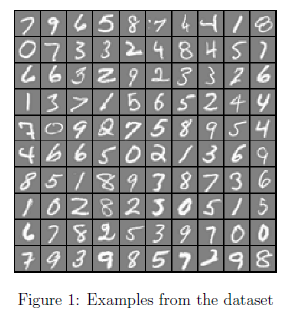

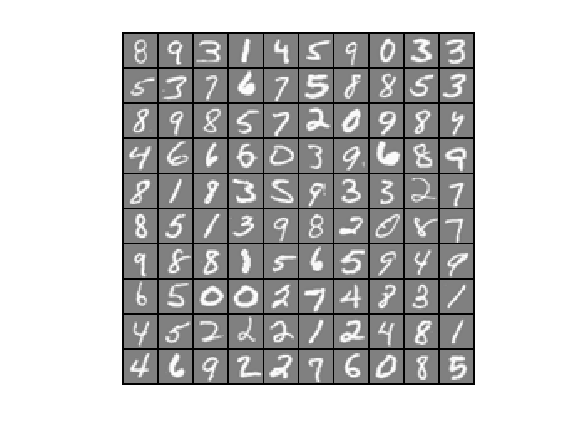

load('ex4data1.mat');
m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));

    There are 5000 training examples in `ex4data1.mat`, where each training example is a 20 pixel by 20 pixel grayscale image of the digit. Each pixel is represented by a floating point number indicating the grayscale intensity at that location. The 20 by 20 grid of pixels is 'unrolled' into a 400-dimensional vector. Each of these training examples becomes a single row in our data matrix `X`. This gives us a 5000 by 400 matrix `X` where every row is a training example for a handwritten digit image.


$$X=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T -\\
-{\left(x^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack$$


The second part of the training set is a 5000-dimensional vector `y` that contains labels for the training set. To make things more compatible with MATLAB indexing, where there is no zero index, we have mapped the digit zero to the value ten. Therefore, a '0' digit is labeled as '10', while the digits '1' to '9' are labeled as '1' to '9' in their natural order.

### 1.2 Model representation

Our neural network is shown in Figure 2. It has 3 layers- an input layer, a hidden layer and an output layer. Recall that our inputs are pixel values of digit images. Since the images are of size 20 x 20, this gives us 400 input layer units (not counting the extra bias unit which always outputs +1). 

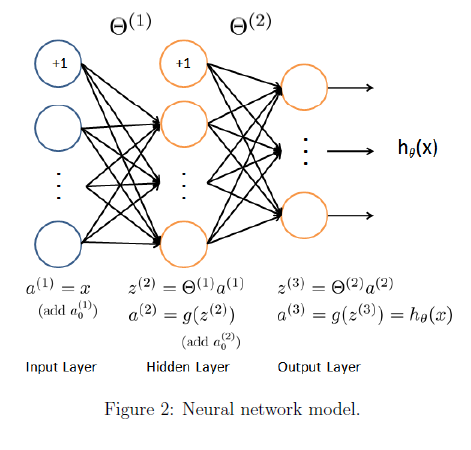

    You have been provided with a set of network parameters $(\Theta^{(1)},\Theta^{(2)})$ already trained by us. These are stored in `ex4weights.mat. ` Run the code below to load them into `Theta1` and `Theta2`. The parameters have dimensions that are sized for a neural network with 25 units in the second layer and 10 output units (corresponding to the 10 digit classes).

% Load the weights into variables Theta1 and Theta2
load('ex4weights.mat');

### 1.3 Feedforward and cost function

Now you will implement the cost function and gradient for the neural network. First, complete the code in `nnCostFunction.m` to return the cost. Recall that the cost function for the neural network (without regularization) is


$$J(\theta) =\frac{1}{m}{\sum_{i=1}^m\sum_{k=1}^K{\left[

-y_k^{(i)} \log((h_{\theta}(x^{(i)}))_k)- (1 -y_k^{(i)}) \log(1- (h_{\theta}(x^{(i)}))_k)\right]},$$


where $h_\theta(x^{(i)})$ is computed as shown in the Figure 2 and $K = 10$ is the total number of possible labels. Note that $h_\theta(x^{(i)})_k = a^{(3)}_k$ is the activation (output value) of the $k$-th output unit. Also, recall that whereas the original labels (in the variable `y`) were $1, 2, \ldots, 10,$ for the purpose of training a neural network, we need to recode the labels as vectors containing only values 0 or 1, so that


$$y=\left\lbrack \begin{array}{c}
1\\
0\\
0\\
\vdots \\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\\
1\\
0\\
\vdots \\
0
\end{array}\right\rbrack ,\dots \textrm{or}\;\left\lbrack \begin{array}{c}
0\\
0\\
0\\
\vdots \\
1
\end{array}\right\rbrack$$


    For example, if $x^{(i)}$ is an image of the digit 5, then the corresponding $y^{(i)}$ (that you should use with the cost function) should be a 10-dimensional vector with $y_5 = 1$, and the other elements equal to 0. You should implement the feedforward computation that computes $h_\theta(x^{(i)})$ for every example $i$ and sum the cost over all examples. Your code should also work for a dataset of any size, with any number of labels (you can assume that there are always at least $K\geq 3$ labels). 

**Implementation Note:** The matrix `X` contains the examples in rows (i.e., `X(i,:)'` is the `i`-th training example $x^{(i)}$, expressed as a $n$ x 1 vector.) When you complete the code in `nnCostFunction.m`, you will need to add the column of 1's to the `X` matrix. The parameters for each unit in the neural network is represented in `Theta1` and `Theta2` as one row. Specifically, the first row of `Theta1` corresponds to the first hidden unit in the second layer. You can use a `for` loop over the examples to compute the cost.  We suggest implementing the feedforward cost *without* regularization first so that it will be easier for you to debug. Later, you will get to implement the regularized cost.

    Once you are done, run the code below to call your `nnCostFunction` using the loaded set of parameters for `Theta1` and `Theta2`. You should see that the cost is about 0.287629.

input_layer_size  = 400;  % 20x20 Input Images of Digits
hidden_layer_size = 25;   % 25 hidden units
num_labels = 10;          % 10 labels, from 1 to 10 (note that we have mapped "0" to label 10)

% Unroll parameters 
nn_params = [Theta1(:) ; Theta2(:)];

% Weight regularization parameter (we set this to 0 here).
lambda = 0;

J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

u =     0.0504
    0.0794
    0.9930
    0.5187
    0.7052
    0.9965
    0.0107
    0.0016
    0.9965
    0.0204


g =     0.0478
    0.0731
    0.0069
    0.2496
    0.2079
    0.0035
    0.0106
    0.0016
    0.0035
    0.0200


u =     0.0081
    0.0510
    0.9337
    0.7003
    0.2539
    0.9963
    0.1325
    0.0007
    0.9972
    0.0118


g =     0.0080
    0.0484
    0.0619
    0.2099
    0.1894
    0.0037
    0.1150
    0.0007
    0.0028
    0.0117


u =     0.0142
    0.0244
    0.9975
    0.8844
    0.9152
    0.9809
    0.0111
    0.0114
    0.9575
    0.0800


g =     0.0140
    0.0238
    0.0025
    0.1022
    0.0776
    0.0187
    0.0109
    0.0112
    0.0407
    0.0736


u =     0.0459
    0.0036
    0.9957
    0.8989
    0.8630
    0.9817
    0.0119
    0.0133
    0.6776
    0.0129


g =     0.0438
    0.0036
    0.0043
    0.0909
    0.1183
    0.0180
    0.0117
    0.0131
    0.2185
    0.0128


u =     0.0019
    0.0778
    0.9885
    0.6916
    0.6405
    0.9995
    0.0041
    0.0000
    1.0000
    0.2476


g =     0.0019
    0.0717
    0.0113
    0.2133
    0.2303
    0.0005
    0.0041
    0.0000
    0.0000
    0.1863


u =     0.0040
    0.0006
    0.9999
    0.4574
    0.9191
    0.9982
    0.0101
    0.0000
    1.0000
    0.0007


g =     0.0040
    0.0006
    0.0001
    0.2482
    0.0743
    0.0018
    0.0100
    0.0000
    0.0000
    0.0007


u =     0.0060
    0.0101
    0.8613
    0.8703
    0.3538
    0.9815
    0.0079
    0.0001
    0.9973
    0.4171


g =     0.0060
    0.0100
    0.1195
    0.1129
    0.2286
    0.0182
    0.0078
    0.0001
    0.0027
    0.2431


u =     0.0058
    0.0121
    0.9971
    0.8507
    0.9809
    0.9992
    0.0269
    0.0001
    0.9944
    0.0012


g =     0.0058
    0.0119
    0.0029
    0.1270
    0.0187
    0.0008
    0.0262
    0.0001
    0.0055
    0.0012


u =     0.0036
    0.0447
    0.9959
    0.5887
    0.7706
    0.9972
    0.0003
    0.0004
    0.9993
    0.0758


g =     0.0036
    0.0427
    0.0041
    0.2421
    0.1768
    0.0028
    0.0003
    0.0004
    0.0007
    0.0700


u =     0.0024
    0.4581
    0.7946
    0.8109
    0.3355
    0.9930
    0.0142
    0.0008
    0.9955
    0.4783


g =     0.0024
    0.2482
    0.1632
    0.1533
    0.2230
    0.0069
    0.0140
    0.0008
    0.0045
    0.2495


u =     0.0033
    0.2880
    0.9951
    0.8328
    0.7911
    0.9976
    0.0015
    0.0006
    0.9986
    0.2090


g =     0.0033
    0.2051
    0.0049
    0.1392
    0.1653
    0.0024
    0.0015
    0.0006
    0.0013
    0.1653


u =     0.0242
    0.0070
    0.9949
    0.7395
    0.9849
    0.9996
    0.0020
    0.0001
    0.9998
    0.0074


g =     0.0236
    0.0070
    0.0051
    0.1926
    0.0149
    0.0004
    0.0020
    0.0001
    0.0002
    0.0073


u =     0.0094
    0.0540
    0.9973
    0.7924
    0.9232
    0.9983
    0.0005
    0.0009
    0.9977
    0.0304


g =     0.0093
    0.0510
    0.0027
    0.1645
    0.0709
    0.0017
    0.0005
    0.0009
    0.0023
    0.0295


u =     0.0675
    0.0006
    0.9992
    0.7446
    0.9941
    0.9989
    0.0049
    0.0005
    0.9972
    0.0006


g =     0.0630
    0.0006
    0.0008
    0.1902
    0.0059
    0.0011
    0.0049
    0.0005
    0.0028
    0.0006


u =     0.0028
    0.0196
    0.9993
    0.4042
    0.7240
    0.9993
    0.0064
    0.0000
    0.9999
    0.0012


g =     0.0028
    0.0192
    0.0007
    0.2408
    0.1998
    0.0007
    0.0064
    0.0000
    0.0001
    0.0012


u =     0.0285
    0.0439
    0.9959
    0.8716
    0.5063
    0.9973
    0.0068
    0.0742
    0.9805
    0.0087


g =     0.0277
    0.0420
    0.0041
    0.1119
    0.2500
    0.0026
    0.0068
    0.0687
    0.0191
    0.0087


u =     0.0025
    0.0288
    0.9972
    0.9749
    0.4635
    0.9980
    0.0426
    0.0001
    0.9868
    0.0119


g =     0.0025
    0.0280
    0.0028
    0.0245
    0.2487
    0.0020
    0.0408
    0.0001
    0.0130
    0.0117


u =     0.0002
    0.0010
    1.0000
    0.9991
    0.9926
    1.0000
    0.0001
    0.0000
    0.9999
    0.0000


g =     0.0002
    0.0010
    0.0000
    0.0009
    0.0073
    0.0000
    0.0001
    0.0000
    0.0001
    0.0000


u =     0.0169
    0.1829
    0.9963
    0.5198
    0.6040
    0.9963
    0.0450
    0.0004
    0.9995
    0.0269


g =     0.0166
    0.1494
    0.0037
    0.2496
    0.2392
    0.0037
    0.0430
    0.0004
    0.0005
    0.0261


u =     0.0035
    0.2503
    0.9917
    0.8894
    0.8564
    0.9979
    0.0006
    0.0049
    0.9878
    0.0347


g =     0.0035
    0.1876
    0.0082
    0.0984
    0.1230
    0.0021
    0.0006
    0.0049
    0.0121
    0.0335


u =     0.1639
    0.0071
    0.9968
    0.8593
    0.9828
    0.9957
    0.0031
    0.0405
    0.8727
    0.0024


g =     0.1371
    0.0070
    0.0032
    0.1209
    0.0169
    0.0043
    0.0031
    0.0388
    0.1111
    0.0024


u =     0.0016
    0.0879
    0.9980
    0.5159
    0.8022
    0.9999
    0.0009
    0.0000
    1.0000
    0.0161


g =     0.0016
    0.0802
    0.0020
    0.2497
    0.1587
    0.0001
    0.0009
    0.0000
    0.0000
    0.0158


u =     0.0035
    0.0221
    0.9993
    0.9214
    0.9972
    1.0000
    0.0003
    0.0000
    1.0000
    0.0002


g =     0.0034
    0.0216
    0.0007
    0.0724
    0.0028
    0.0000
    0.0003
    0.0000
    0.0000
    0.0002


u =     0.0956
    0.1073
    0.9798
    0.7062
    0.5698
    0.9581
    0.0182
    0.0134
    0.9851
    0.1307


g =     0.0865
    0.0958
    0.0198
    0.2075
    0.2451
    0.0401
    0.0179
    0.0132
    0.0146
    0.1136


u =     0.0244
    0.2421
    0.9968
    0.7185
    0.8895
    0.9505
    0.0060
    0.0022
    0.9961
    0.3256


g =     0.0238
    0.1835
    0.0032
    0.2023
    0.0983
    0.0471
    0.0060
    0.0021
    0.0039
    0.2196


u = 25×1
    0.0112
    0.0031
    0.9976
    0.7780
    0.9845
    0.9999
    0.0035
    0.0000
    0.9999
    0.0016


g = 25×1
    0.0111
    0.0030
    0.0024
    0.1727
    0.0152
    0.0001
    0.0035
    0.0000
    0.0001
    0.0016


u = 25×1
    0.3851
    0.0476
    0.9816
    0.7140
    0.9140
    0.9253
    0.0083
    0.1817
    0.6602
    0.0666


g = 25×1
    0.2368
    0.0453
    0.0181
    0.2042
    0.0786
    0.0691
    0.0082
    0.1487
    0.2243
    0.0622


u = 25×1
    0.0507
    0.0513
    0.9483
    0.9243
    0.8505
    0.9848
    0.0089
    0.0100
    0.9427
    0.0787


g = 25×1
    0.0481
    0.0487
    0.0491
    0.0700
    0.1271
    0.0149
    0.0088
    0.0099
    0.0540
    0.0725


u = 25×1
    0.0062
    0.0407
    0.9988
    0.9723
    0.8676
    0.9990
    0.0231
    0.0001
    0.9993
    0.0131


g = 25×1
    0.0062
    0.0390
    0.0012
    0.0269
    0.1149
    0.0010
    0.0226
    0.0001
    0.0007
    0.0129


u = 25×1
    0.0079
    0.0099
    0.9994
    0.4525
    0.9887
    0.9999
    0.0012
    0.0000
    1.0000
    0.0005


g = 25×1
    0.0078
    0.0098
    0.0006
    0.2477
    0.0111
    0.0001
    0.0012
    0.0000
    0.0000
    0.0005


u = 25×1
    0.1441
    0.0263
    0.9675
    0.2589
    0.3034
    0.7722
    0.3595
    0.0128
    0.8143
    0.0067


g = 25×1
    0.1233
    0.0256
    0.0315
    0.1919
    0.2114
    0.1759
    0.2303
    0.0127
    0.1512
    0.0066


u = 25×1
    0.0073
    0.0001
    1.0000
    0.9958
    0.9983
    1.0000
    0.0004
    0.0002
    0.9958
    0.0000


g = 25×1
    0.0073
    0.0001
    0.0000
    0.0042
    0.0017
    0.0000
    0.0004
    0.0002
    0.0042
    0.0000


u = 25×1
    0.0081
    0.0045
    1.0000
    0.9985
    0.9972
    1.0000
    0.0002
    0.0011
    0.9923
    0.0002


g = 25×1
    0.0080
    0.0044
    0.0000
    0.0015
    0.0028
    0.0000
    0.0002
    0.0010
    0.0076
    0.0002


u = 25×1
    0.2751
    0.0019
    0.9922
    0.5923
    0.9788
    0.9948
    0.0107
    0.0062
    0.9528
    0.0040


g = 25×1
    0.1994
    0.0019
    0.0078
    0.2415
    0.0207
    0.0051
    0.0106
    0.0061
    0.0450
    0.0040


u = 25×1
    0.0055
    0.0212
    0.9997
    0.9905
    0.9723
    1.0000
    0.0014
    0.0003
    0.9885
    0.0005


g = 25×1
    0.0055
    0.0207
    0.0003
    0.0095
    0.0269
    0.0000
    0.0014
    0.0003
    0.0114
    0.0005


u = 25×1
    0.0483
    0.0231
    0.9955
    0.5985
    0.9789
    0.9992
    0.0004
    0.0069
    0.9965
    0.0045


g = 25×1
    0.0460
    0.0226
    0.0044
    0.2403
    0.0206
    0.0008
    0.0004
    0.0069
    0.0035
    0.0045


u = 25×1
    0.0483
    0.0312
    0.9941
    0.7406
    0.8505
    0.9901
    0.0036
    0.0058
    0.9914
    0.0488


g = 25×1
    0.0460
    0.0302
    0.0059
    0.1921
    0.1271
    0.0098
    0.0035
    0.0058
    0.0085
    0.0464


u = 25×1
    0.0028
    0.0781
    0.9965
    0.9694
    0.8788
    0.9993
    0.0127
    0.0001
    0.9982
    0.0189


g = 25×1
    0.0027
    0.0720
    0.0035
    0.0297
    0.1065
    0.0007
    0.0125
    0.0001
    0.0018
    0.0185


u = 25×1
    0.0034
    0.0033
    1.0000
    0.9995
    0.9116
    0.9995
    0.0228
    0.0018
    0.6449
    0.0004


g = 25×1
    0.0034
    0.0033
    0.0000
    0.0005
    0.0806
    0.0005
    0.0223
    0.0018
    0.2290
    0.0004


u = 25×1
    0.0164
    0.0002
    1.0000
    0.9938
    0.9667
    0.9993
    0.0055
    0.0004
    0.9498
    0.0001


g = 25×1
    0.0161
    0.0002
    0.0000
    0.0062
    0.0322
    0.0007
    0.0055
    0.0004
    0.0477
    0.0001


u = 25×1
    0.0022
    0.0016
    0.9999
    0.9924
    0.9954
    1.0000
    0.0005
    0.0000
    0.9996
    0.0000


g = 25×1
    0.0022
    0.0016
    0.0001
    0.0075
    0.0046
    0.0000
    0.0005
    0.0000
    0.0004
    0.0000


u = 25×1
    0.0038
    0.0060
    0.9999
    0.9659
    0.9656
    0.9999
    0.0057
    0.0001
    0.9991
    0.0001


g = 25×1
    0.0038
    0.0060
    0.0001
    0.0330
    0.0332
    0.0001
    0.0057
    0.0001
    0.0009
    0.0001


u = 25×1
    0.0065
    0.0001
    1.0000
    0.9899
    0.9958
    1.0000
    0.0003
    0.0016
    0.9998
    0.0000


g = 25×1
    0.0065
    0.0001
    0.0000
    0.0100
    0.0042
    0.0000
    0.0003
    0.0016
    0.0002
    0.0000


u = 25×1
    0.2812
    0.0133
    0.9775
    0.2655
    0.8698
    0.8718
    0.0078
    0.0095
    0.9305
    0.0422


g = 25×1
    0.2021
    0.0131
    0.0220
    0.1950
    0.1132
    0.1117
    0.0077
    0.0094
    0.0647
    0.0404


u = 25×1
    0.0044
    0.1461
    0.9999
    0.9942
    0.8224
    0.9988
    0.0942
    0.0047
    0.9269
    0.0025


g = 25×1
    0.0044
    0.1247
    0.0001
    0.0057
    0.1460
    0.0012
    0.0853
    0.0046
    0.0678
    0.0025


u = 25×1
    0.0039
    0.0034
    0.9999
    0.9914
    0.9967
    0.9999
    0.0006
    0.0000
    0.9996
    0.0024


g = 25×1
    0.0039
    0.0034
    0.0001
    0.0085
    0.0033
    0.0001
    0.0006
    0.0000
    0.0004
    0.0024


u = 25×1
    0.0145
    0.0010
    0.9996
    0.7085
    0.9265
    0.9997
    0.0014
    0.0000
    0.9996
    0.0001


g = 25×1
    0.0143
    0.0010
    0.0004
    0.2065
    0.0681
    0.0003
    0.0014
    0.0000
    0.0004
    0.0001


u = 25×1
    0.2023
    0.0000
    0.9996
    0.8557
    0.9993
    0.9999
    0.0004
    0.0000
    0.9989
    0.0000


g = 25×1
    0.1614
    0.0000
    0.0004
    0.1235
    0.0007
    0.0001
    0.0004
    0.0000
    0.0011
    0.0000


u = 25×1
    0.0460
    0.1114
    0.9991
    0.9614
    0.7971
    0.9909
    0.0428
    0.0039
    0.9018
    0.0176


g = 25×1
    0.0439
    0.0990
    0.0009
    0.0371
    0.1617
    0.0090
    0.0410
    0.0039
    0.0886
    0.0172


u = 25×1
    0.0945
    0.0091
    0.9997
    0.7898
    0.6034
    0.7505
    0.3084
    0.0010
    0.8768
    0.0034


g = 25×1
    0.0856
    0.0090
    0.0003
    0.1660
    0.2393
    0.1873
    0.2133
    0.0010
    0.1080
    0.0034


u = 25×1
    0.0793
    0.0038
    0.9989
    0.9061
    0.7666
    0.9314
    0.5121
    0.0003
    0.8451
    0.0085


g = 25×1
    0.0730
    0.0038
    0.0011
    0.0851
    0.1789
    0.0639
    0.2499
    0.0003
    0.1309
    0.0084


u = 25×1
    0.0336
    0.0237
    0.9964
    0.9882
    0.9832
    1.0000
    0.0001
    0.0006
    0.9903
    0.0015


g = 25×1
    0.0324
    0.0231
    0.0036
    0.0117
    0.0165
    0.0000
    0.0001
    0.0006
    0.0096
    0.0015


u = 25×1
    0.0233
    0.0002
    0.9999
    0.9368
    0.9985
    1.0000
    0.0003
    0.0000
    0.9998
    0.0000


g = 25×1
    0.0227
    0.0002
    0.0001
    0.0592
    0.0015
    0.0000
    0.0003
    0.0000
    0.0002
    0.0000


u = 25×1
    0.3733
    0.0075
    0.9710
    0.9010
    0.4635
    0.1216
    0.9738
    0.0315
    0.0465
    0.0577


g = 25×1
    0.2339
    0.0074
    0.0281
    0.0892
    0.2487
    0.1068
    0.0255
    0.0305
    0.0444
    0.0544


u = 25×1
    0.0116
    0.0473
    0.9991
    0.9941
    0.9883
    0.9989
    0.0003
    0.0182
    0.6774
    0.0068


g = 25×1
    0.0115
    0.0451
    0.0009
    0.0058
    0.0116
    0.0011
    0.0003
    0.0179
    0.2185
    0.0068


u = 25×1
    0.0342
    0.0431
    0.9982
    0.9206
    0.5940
    0.9737
    0.3063
    0.0002
    0.9739
    0.0565


g = 25×1
    0.0331
    0.0412
    0.0018
    0.0731
    0.2412
    0.0256
    0.2125
    0.0002
    0.0254
    0.0533


u = 25×1
    0.0344
    0.0140
    0.9987
    0.3163
    0.7930
    0.9648
    0.0073
    0.0232
    0.9980
    0.0744


g = 25×1
    0.0332
    0.0138
    0.0013
    0.2163
    0.1642
    0.0339
    0.0073
    0.0227
    0.0020
    0.0689


u = 25×1
    0.1901
    0.0003
    0.9988
    0.4182
    0.9921
    0.9994
    0.0021
    0.0018
    0.9998
    0.0007


g = 25×1
    0.1539
    0.0003
    0.0012
    0.2433
    0.0078
    0.0006
    0.0021
    0.0018
    0.0002
    0.0007


u = 25×1
    0.0369
    0.0729
    0.9846
    0.9875
    0.5676
    0.9162
    0.4635
    0.0050
    0.2452
    0.1407


g = 25×1
    0.0356
    0.0676
    0.0151
    0.0123
    0.2454
    0.0768
    0.2487
    0.0049
    0.1851
    0.1209


u = 25×1
    0.1080
    0.0109
    0.9836
    0.3562
    0.9654
    0.9964
    0.0019
    0.0033
    0.9968
    0.0086


g = 25×1
    0.0963
    0.0108
    0.0161
    0.2293
    0.0334
    0.0036
    0.0019
    0.0033
    0.0032
    0.0086


u = 25×1
    0.0716
    0.1214
    0.9744
    0.9469
    0.7390
    0.7181
    0.4145
    0.0028
    0.7111
    0.2181


g = 25×1
    0.0665
    0.1067
    0.0250
    0.0503
    0.1929
    0.2024
    0.2427
    0.0028
    0.2054
    0.1706


u = 25×1
    0.0367
    0.0490
    0.9928
    0.7458
    0.7646
    0.9885
    0.0433
    0.0007
    0.9921
    0.0335


g = 25×1
    0.0354
    0.0466
    0.0072
    0.1896
    0.1800
    0.0114
    0.0414
    0.0007
    0.0079
    0.0324


u = 25×1
    0.2252
    0.0018
    0.9997
    0.8196
    0.9447
    0.9606
    0.0036
    0.0234
    0.7454
    0.0043


g = 25×1
    0.1745
    0.0018
    0.0003
    0.1478
    0.0523
    0.0379
    0.0036
    0.0228
    0.1898
    0.0043


u = 25×1
    0.0162
    0.0487
    0.9862
    0.5927
    0.4347
    0.9790
    0.0020
    0.0025
    0.9980
    0.1849


g = 25×1
    0.0159
    0.0463
    0.0136
    0.2414
    0.2457
    0.0205
    0.0020
    0.0025
    0.0020
    0.1507


u = 25×1
    0.3730
    0.0245
    0.9931
    0.8849
    0.9673
    0.9338
    0.0536
    0.0836
    0.4538
    0.0110


g = 25×1
    0.2339
    0.0239
    0.0068
    0.1018
    0.0316
    0.0618
    0.0508
    0.0766
    0.2479
    0.0109


u = 25×1
    0.0902
    0.0021
    0.9660
    0.9907
    0.2174
    0.3346
    0.9550
    0.0035
    0.0028
    0.0398


g = 25×1
    0.0821
    0.0021
    0.0328
    0.0092
    0.1701
    0.2226
    0.0430
    0.0035
    0.0028
    0.0383


u = 25×1
    0.1497
    0.0039
    0.9984
    0.5116
    0.9858
    0.9955
    0.0012
    0.0031
    0.9982
    0.0208


g = 25×1
    0.1273
    0.0039
    0.0016
    0.2499
    0.0140
    0.0045
    0.0012
    0.0031
    0.0018
    0.0204


u = 25×1
    0.0056
    0.1316
    0.9972
    0.9813
    0.7530
    0.9989
    0.0165
    0.0012
    0.9871
    0.0314


g = 25×1
    0.0056
    0.1143
    0.0028
    0.0184
    0.1860
    0.0011
    0.0162
    0.0012
    0.0128
    0.0304


u = 25×1
    0.0056
    0.1584
    0.9951
    0.9866
    0.6932
    0.9975
    0.0332
    0.0009
    0.9740
    0.1137


g = 25×1
    0.0056
    0.1333
    0.0049
    0.0132
    0.2127
    0.0025
    0.0321
    0.0009
    0.0254
    0.1008


u = 25×1
    0.5617
    0.0018
    0.9958
    0.8876
    0.9973
    0.9869
    0.0029
    0.0059
    0.4977
    0.0229


g = 25×1
    0.2462
    0.0018
    0.0042
    0.0997
    0.0027
    0.0129
    0.0029
    0.0059
    0.2500
    0.0224


u = 25×1
    0.0170
    0.2328
    0.9623
    0.6496
    0.4924
    0.9853
    0.1455
    0.0003
    0.9973
    0.2982


g = 25×1
    0.0167
    0.1786
    0.0363
    0.2276
    0.2499
    0.0145
    0.1243
    0.0003
    0.0027
    0.2093


u = 25×1
    0.0135
    0.0020
    0.9991
    0.9866
    0.7414
    0.9457
    0.2961
    0.0065
    0.9465
    0.0227


g = 25×1
    0.0133
    0.0020
    0.0009
    0.0133
    0.1917
    0.0514
    0.2084
    0.0065
    0.0507
    0.0222


u = 25×1
    0.0005
    0.1698
    1.0000
    0.9996
    0.6953
    0.9995
    0.0176
    0.0016
    0.8455
    0.0136


g = 25×1
    0.0005
    0.1410
    0.0000
    0.0004
    0.2119
    0.0004
    0.0172
    0.0016
    0.1306
    0.0134


u = 25×1
    0.0016
    0.1427
    0.9995
    0.9992
    0.6480
    0.9989
    0.0443
    0.0021
    0.8310
    0.0399


g = 25×1
    0.0016
    0.1224
    0.0005
    0.0008
    0.2281
    0.0011
    0.0423
    0.0021
    0.1405
    0.0383


u = 25×1
    0.0120
    0.0623
    0.9977
    0.9989
    0.5387
    0.9467
    0.5511
    0.0043
    0.1473
    0.1805


g = 25×1
    0.0119
    0.0584
    0.0023
    0.0011
    0.2485
    0.0505
    0.2474
    0.0043
    0.1256
    0.1479


u = 25×1
    0.2475
    0.0296
    0.9918
    0.5128
    0.9355
    0.8115
    0.0040
    0.0108
    0.8974
    0.1286


g = 25×1
    0.1862
    0.0287
    0.0081
    0.2498
    0.0604
    0.1529
    0.0040
    0.0107
    0.0920
    0.1120


u = 25×1
    0.0018
    0.0728
    0.9996
    0.9990
    0.6332
    0.9985
    0.0578
    0.0019
    0.7660
    0.0250


g = 25×1
    0.0018
    0.0675
    0.0004
    0.0010
    0.2322
    0.0015
    0.0544
    0.0019
    0.1793
    0.0244


u = 25×1
    0.0146
    0.1467
    0.9988
    0.9817
    0.8879
    0.9991
    0.0121
    0.0017
    0.9844
    0.0099


g = 25×1
    0.0144
    0.1252
    0.0012
    0.0180
    0.0995
    0.0009
    0.0120
    0.0017
    0.0154
    0.0098


u = 25×1
    0.0072
    0.1849
    0.9974
    0.9893
    0.9790
    1.0000
    0.0001
    0.0002
    0.9870
    0.0033


g = 25×1
    0.0072
    0.1507
    0.0026
    0.0105
    0.0205
    0.0000
    0.0001
    0.0002
    0.0128
    0.0033


u = 25×1
    0.0224
    0.1542
    0.9748
    0.7494
    0.7552
    0.9885
    0.0142
    0.0007
    0.9974
    0.3139


g = 25×1
    0.0219
    0.1304
    0.0245
    0.1878
    0.1849
    0.0114
    0.0140
    0.0007
    0.0026
    0.2154


u = 25×1
    0.1613
    0.0101
    0.9995
    0.9848
    0.8360
    0.8718
    0.3782
    0.0094
    0.2503
    0.0095


g = 25×1
    0.1353
    0.0100
    0.0005
    0.0149
    0.1371
    0.1118
    0.2352
    0.0093
    0.1876
    0.0094


u = 25×1
    0.0038
    0.1158
    0.9913
    0.9935
    0.7488
    0.9925
    0.1227
    0.0034
    0.8594
    0.0763


g = 25×1
    0.0038
    0.1024
    0.0086
    0.0065
    0.1881
    0.0075
    0.1077
    0.0034
    0.1209
    0.0704


u = 25×1
    0.0292
    0.1044
    0.9940
    0.9580
    0.7357
    0.9231
    0.3365
    0.0011
    0.9633
    0.2674


g = 25×1
    0.0283
    0.0935
    0.0059
    0.0402
    0.1944
    0.0710
    0.2233
    0.0011
    0.0354
    0.1959


u = 25×1
    0.0190
    0.0732
    0.9996
    0.9785
    0.9285
    0.9983
    0.0078
    0.0040
    0.9505
    0.0056


g = 25×1
    0.0187
    0.0678
    0.0004
    0.0211
    0.0664
    0.0017
    0.0077
    0.0040
    0.0471
    0.0055


u = 25×1
    0.0221
    0.2136
    0.9944
    0.9770
    0.8022
    0.9858
    0.0164
    0.0050
    0.6100
    0.1541


g = 25×1
    0.0216
    0.1680
    0.0056
    0.0225
    0.1587
    0.0140
    0.0161
    0.0049
    0.2379
    0.1303


u = 25×1
    0.3074
    0.0000
    0.9997
    0.2836
    0.9972
    0.9995
    0.0019
    0.0003
    0.9999
    0.0002


g = 25×1
    0.2129
    0.0000
    0.0003
    0.2032
    0.0028
    0.0005
    0.0019
    0.0003
    0.0001
    0.0002


u = 25×1
    0.1741
    0.0121
    0.9951
    0.9382
    0.2280
    0.4205
    0.9624
    0.0288
    0.5824
    0.1750


g = 25×1
    0.1438
    0.0119
    0.0049
    0.0580
    0.1760
    0.2437
    0.0362
    0.0280
    0.2432
    0.1444


u = 25×1
    0.1783
    0.0222
    0.9950
    0.9798
    0.3878
    0.4408
    0.9150
    0.0429
    0.4546
    0.2837


g = 25×1
    0.1465
    0.0217
    0.0050
    0.0198
    0.2374
    0.2465
    0.0778
    0.0410
    0.2479
    0.2032


u = 25×1
    0.0297
    0.2572
    0.9945
    0.9644
    0.8483
    0.9936
    0.0139
    0.0028
    0.9340
    0.0914


g = 25×1
    0.0289
    0.1910
    0.0055
    0.0343
    0.1287
    0.0064
    0.0137
    0.0028
    0.0617
    0.0830


u = 25×1
    0.3115
    0.0188
    0.9305
    0.8895
    0.6575
    0.4005
    0.6753
    0.0509
    0.4563
    0.0981


g = 25×1
    0.2145
    0.0184
    0.0647
    0.0983
    0.2252
    0.2401
    0.2193
    0.0483
    0.2481
    0.0884


u = 25×1
    0.3163
    0.0285
    0.9982
    0.8293
    0.8987
    0.8717
    0.1910
    0.0013
    0.9567
    0.0623


g = 25×1
    0.2162
    0.0277
    0.0018
    0.1416
    0.0910
    0.1118
    0.1545
    0.0013
    0.0415
    0.0584


u = 25×1
    0.0574
    0.0405
    0.9940
    0.3940
    0.8636
    0.9612
    0.0025
    0.0081
    0.9982
    0.2567


g = 25×1
    0.0541
    0.0389
    0.0060
    0.2388
    0.1178
    0.0373
    0.0025
    0.0080
    0.0018
    0.1908


u = 25×1
    0.0373
    0.1774
    0.9835
    0.9525
    0.8401
    0.8636
    0.1567
    0.0076
    0.6694
    0.2385


g = 25×1
    0.0359
    0.1459
    0.0162
    0.0453
    0.1343
    0.1178
    0.1321
    0.0076
    0.2213
    0.1816


u = 25×1
    0.0635
    0.2116
    0.9954
    0.9770
    0.4977
    0.8896
    0.2061
    0.0224
    0.2142
    0.2915


g = 25×1
    0.0594
    0.1668
    0.0045
    0.0225
    0.2500
    0.0982
    0.1636
    0.0219
    0.1683
    0.2065


u = 25×1
    0.1658
    0.0800
    0.9914
    0.9090
    0.8225
    0.7155
    0.1848
    0.0148
    0.5341
    0.1967


g = 25×1
    0.1383
    0.0736
    0.0085
    0.0827
    0.1460
    0.2035
    0.1506
    0.0146
    0.2488
    0.1580


u = 25×1
    0.0940
    0.0025
    0.9967
    0.6762
    0.9621
    0.9851
    0.0173
    0.0003
    0.9980
    0.0310


g = 25×1
    0.0851
    0.0025
    0.0033
    0.2189
    0.0365
    0.0147
    0.0170
    0.0003
    0.0020
    0.0301


u = 25×1
    0.2949
    0.0266
    0.9867
    0.8803
    0.4340
    0.4009
    0.8904
    0.0153
    0.5960
    0.2400


g = 25×1
    0.2079
    0.0259
    0.0131
    0.1054
    0.2456
    0.2402
    0.0976
    0.0151
    0.2408
    0.1824


u = 25×1
    0.0369
    0.0795
    0.9960
    0.7290
    0.7655
    0.9764
    0.0053
    0.0205
    0.9919
    0.1932


g = 25×1
    0.0355
    0.0732
    0.0040
    0.1975
    0.1795
    0.0231
    0.0053
    0.0201
    0.0080
    0.1559


u = 25×1
    0.0229
    0.4657
    0.9884
    0.9863
    0.5258
    0.9524
    0.4256
    0.0433
    0.4491
    0.4031


g = 25×1
    0.0223
    0.2488
    0.0115
    0.0135
    0.2493
    0.0453
    0.2445
    0.0415
    0.2474
    0.2406


u = 25×1
    0.1615
    0.0012
    0.9682
    0.2352
    0.9641
    0.9931
    0.0014
    0.0027
    0.9959
    0.0073


g = 25×1
    0.1354
    0.0012
    0.0308
    0.1799
    0.0347
    0.0068
    0.0014
    0.0026
    0.0041
    0.0072


u = 25×1
    0.0110
    0.0014
    0.9998
    0.9275
    0.9953
    0.9999
    0.0018
    0.0001
    0.9994
    0.0001


g = 25×1
    0.0109
    0.0014
    0.0002
    0.0672
    0.0046
    0.0001
    0.0018
    0.0001
    0.0006
    0.0001


u = 25×1
    0.0102
    0.3951
    0.9887
    0.9923
    0.1328
    0.9592
    0.6179
    0.0821
    0.3507
    0.2165


g = 25×1
    0.0101
    0.2390
    0.0111
    0.0076
    0.1152
    0.0391
    0.2361
    0.0753
    0.2277
    0.1696


u = 25×1
    0.0015
    0.0209
    0.9997
    0.8382
    0.9219
    0.9999
    0.0006
    0.0000
    1.0000
    0.0110


g = 25×1
    0.0015
    0.0204
    0.0003
    0.1356
    0.0720
    0.0001
    0.0006
    0.0000
    0.0000
    0.0108


u = 25×1
    0.1714
    0.1096
    0.9733
    0.6020
    0.8991
    0.9164
    0.0424
    0.0014
    0.9967
    0.1801


g = 25×1
    0.1420
    0.0976
    0.0260
    0.2396
    0.0907
    0.0766
    0.0406
    0.0014
    0.0033
    0.1477


u = 25×1
    0.0663
    0.3492
    0.5709
    0.6004
    0.2953
    0.6790
    0.8494
    0.0232
    0.8353
    0.5553


g = 25×1
    0.0619
    0.2273
    0.2450
    0.2399
    0.2081
    0.2180
    0.1279
    0.0227
    0.1375
    0.2469


u = 25×1
    0.1013
    0.0815
    0.9435
    0.1778
    0.9774
    0.9813
    0.0007
    0.0011
    0.9988
    0.3438


g = 25×1
    0.0910
    0.0749
    0.0533
    0.1462
    0.0221
    0.0184
    0.0007
    0.0010
    0.0012
    0.2256


u = 25×1
    0.0038
    0.1196
    0.9973
    0.9327
    0.9603
    1.0000
    0.0006
    0.0001
    0.9999
    0.0035


g = 25×1
    0.0038
    0.1053
    0.0027
    0.0628
    0.0381
    0.0000
    0.0006
    0.0001
    0.0001
    0.0035


u = 25×1
    0.0149
    0.0923
    0.9991
    0.9748
    0.5584
    0.9990
    0.0037
    0.0034
    0.9858
    0.0129


g = 25×1
    0.0147
    0.0838
    0.0009
    0.0246
    0.2466
    0.0010
    0.0037
    0.0034
    0.0140
    0.0128


u = 25×1
    0.0029
    0.1927
    0.9932
    0.9860
    0.5092
    0.9985
    0.1008
    0.0057
    0.9937
    0.0525


g = 25×1
    0.0029
    0.1556
    0.0068
    0.0138
    0.2499
    0.0015
    0.0906
    0.0057
    0.0063
    0.0498


u = 25×1
    0.0073
    0.1331
    0.9946
    0.9907
    0.8751
    0.9995
    0.0056
    0.0029
    0.9163
    0.0226


g = 25×1
    0.0072
    0.1154
    0.0054
    0.0092
    0.1093
    0.0005
    0.0056
    0.0029
    0.0767
    0.0221


u = 25×1
    0.0129
    0.0665
    0.9995
    0.9714
    0.6320
    0.9902
    0.0275
    0.0067
    0.9468
    0.0762


g = 25×1
    0.0127
    0.0621
    0.0005
    0.0277
    0.2326
    0.0097
    0.0268
    0.0067
    0.0503
    0.0704


u = 25×1
    0.0372
    0.0208
    0.9788
    0.8527
    0.8431
    0.9938
    0.0095
    0.0150
    0.9856
    0.0108


g = 25×1
    0.0358
    0.0204
    0.0208
    0.1256
    0.1323
    0.0061
    0.0094
    0.0147
    0.0142
    0.0107


u = 25×1
    0.0014
    0.3123
    0.7272
    0.9477
    0.3424
    0.9874
    0.0825
    0.0073
    0.9906
    0.4124


g = 25×1
    0.0014
    0.2148
    0.1984
    0.0496
    0.2252
    0.0125
    0.0757
    0.0073
    0.0093
    0.2423


u = 25×1
    0.0176
    0.0416
    0.9987
    0.9464
    0.9879
    0.9998
    0.0008
    0.0051
    0.9957
    0.0015


g = 25×1
    0.0173
    0.0398
    0.0013
    0.0507
    0.0120
    0.0002
    0.0008
    0.0050
    0.0042
    0.0015


u = 25×1
    0.1570
    0.2735
    0.9755
    0.6785
    0.6171
    0.8958
    0.0326
    0.0790
    0.8869
    0.1515


g = 25×1
    0.1324
    0.1987
    0.0239
    0.2181
    0.2363
    0.0934
    0.0315
    0.0728
    0.1003
    0.1285


u = 25×1
    0.0820
    0.0009
    0.9995
    0.9617
    0.9429
    0.9881
    0.0272
    0.0003
    0.9813
    0.0068


g = 25×1
    0.0752
    0.0009
    0.0005
    0.0368
    0.0538
    0.0118
    0.0265
    0.0003
    0.0183
    0.0068


u = 25×1
    0.0332
    0.0007
    0.9975
    0.9806
    0.7774
    0.9250
    0.1734
    0.0122
    0.7011
    0.0167


g = 25×1
    0.0321
    0.0007
    0.0025
    0.0190
    0.1730
    0.0694
    0.1433
    0.0121
    0.2096
    0.0165


u = 25×1
    0.0516
    0.0000
    0.9999
    0.9697
    0.4811
    0.9623
    0.0429
    0.0010
    0.9662
    0.0087


g = 25×1
    0.0489
    0.0000
    0.0001
    0.0294
    0.2496
    0.0363
    0.0410
    0.0010
    0.0326
    0.0086


u = 25×1
    0.0811
    0.0072
    0.9996
    0.9168
    0.9735
    0.9667
    0.0041
    0.0115
    0.9510
    0.0131


g = 25×1
    0.0746
    0.0072
    0.0004
    0.0763
    0.0258
    0.0322
    0.0041
    0.0114
    0.0466
    0.0129


u = 25×1
    0.0373
    0.0385
    0.9043
    0.9335
    0.6602
    0.9727
    0.0947
    0.0023
    0.4961
    0.0913


g = 25×1
    0.0359
    0.0370
    0.0865
    0.0621
    0.2243
    0.0265
    0.0857
    0.0023
    0.2500
    0.0830


u = 25×1
    0.0006
    0.1599
    0.9716
    0.8921
    0.3560
    0.9984
    0.0181
    0.0001
    1.0000
    0.1603


g = 25×1
    0.0006
    0.1343
    0.0276
    0.0962
    0.2293
    0.0016
    0.0178
    0.0001
    0.0000
    0.1346


u = 25×1
    0.1825
    0.0019
    1.0000
    0.9646
    0.4841
    0.4983
    0.7350
    0.0158
    0.0938
    0.0243


g = 25×1
    0.1492
    0.0019
    0.0000
    0.0342
    0.2497
    0.2500
    0.1948
    0.0156
    0.0850
    0.0237


u = 25×1
    0.0122
    0.0079
    0.9917
    0.9845
    0.8699
    0.8863
    0.3721
    0.0040
    0.6912
    0.0428


g = 25×1
    0.0120
    0.0078
    0.0082
    0.0153
    0.1132
    0.1008
    0.2336
    0.0040
    0.2134
    0.0410


u = 25×1
    0.0154
    0.0005
    0.9986
    0.9934
    0.8245
    0.9592
    0.2017
    0.0067
    0.6920
    0.0113


g = 25×1
    0.0152
    0.0005
    0.0013
    0.0066
    0.1447
    0.0391
    0.1610
    0.0067
    0.2131
    0.0112


u = 25×1
    0.0945
    0.0000
    1.0000
    0.9891
    0.8146
    0.9888
    0.1045
    0.0237
    0.7778
    0.0002


g = 25×1
    0.0856
    0.0000
    0.0000
    0.0108
    0.1510
    0.0111
    0.0936
    0.0231
    0.1728
    0.0002


u = 25×1
    0.0058
    0.0001
    0.9999
    0.9987
    0.9722
    0.9996
    0.0134
    0.0001
    0.9016
    0.0001


g = 25×1
    0.0057
    0.0001
    0.0001
    0.0013
    0.0271
    0.0004
    0.0132
    0.0001
    0.0887
    0.0001


u = 25×1
    0.0007
    0.0850
    0.9972
    0.8733
    0.5375
    0.9997
    0.0029
    0.0002
    1.0000
    0.0608


g = 25×1
    0.0007
    0.0778
    0.0028
    0.1107
    0.2486
    0.0003
    0.0028
    0.0002
    0.0000
    0.0571


u = 25×1
    0.0029
    0.0010
    0.9988
    0.9984
    0.8978
    0.9973
    0.0295
    0.0004
    0.8881
    0.0059


g = 25×1
    0.0029
    0.0010
    0.0012
    0.0016
    0.0917
    0.0027
    0.0286
    0.0004
    0.0994
    0.0058


u = 25×1
    0.0252
    0.0036
    0.9924
    0.5131
    0.9631
    0.9983
    0.0003
    0.0001
    0.9994
    0.0591


g = 25×1
    0.0245
    0.0036
    0.0076
    0.2498
    0.0356
    0.0017
    0.0003
    0.0001
    0.0006
    0.0556


u = 25×1
    0.0458
    0.0051
    0.8849
    0.9713
    0.9393
    0.8609
    0.1196
    0.0317
    0.2503
    0.0508


g = 25×1
    0.0437
    0.0051
    0.1019
    0.0278
    0.0570
    0.1197
    0.1053
    0.0307
    0.1876
    0.0482


u = 25×1
    0.0020
    0.0115
    0.9953
    0.8332
    0.9138
    0.9996
    0.0053
    0.0000
    0.9999
    0.0234


g = 25×1
    0.0020
    0.0114
    0.0047
    0.1390
    0.0788
    0.0004
    0.0052
    0.0000
    0.0001
    0.0228


u = 25×1
    0.1133
    0.0014
    0.9489
    0.9790
    0.8716
    0.7488
    0.4380
    0.0656
    0.2632
    0.0554


g = 25×1
    0.1005
    0.0014
    0.0485
    0.0205
    0.1119
    0.1881
    0.2462
    0.0613
    0.1939
    0.0524


u = 25×1
    0.1048
    0.0408
    0.9891
    0.7615
    0.6362
    0.9077
    0.6430
    0.0007
    0.8654
    0.0783


g = 25×1
    0.0938
    0.0392
    0.0108
    0.1816
    0.2315
    0.0838
    0.2295
    0.0007
    0.1165
    0.0722


u = 25×1
    0.5128
    0.0013
    0.7688
    0.9328
    0.3166
    0.0351
    0.9968
    0.0039
    0.0277
    0.1264


g = 25×1
    0.2498
    0.0013
    0.1778
    0.0627
    0.2164
    0.0338
    0.0032
    0.0039
    0.0269
    0.1104


u = 25×1
    0.0113
    0.0439
    0.9729
    0.9939
    0.3976
    0.9641
    0.8038
    0.0008
    0.3033
    0.1253


g = 25×1
    0.0112
    0.0420
    0.0264
    0.0061
    0.2395
    0.0346
    0.1577
    0.0008
    0.2113
    0.1096


u = 25×1
    0.2532
    0.0379
    0.9859
    0.5222
    0.9972
    0.9927
    0.0020
    0.0206
    0.9686
    0.0751


g = 25×1
    0.1891
    0.0365
    0.0139
    0.2495
    0.0028
    0.0073
    0.0020
    0.0202
    0.0305
    0.0695


u = 25×1
    0.0154
    0.0737
    0.9985
    0.9853
    0.7841
    0.9954
    0.0252
    0.0002
    0.8658
    0.0129


g = 25×1
    0.0151
    0.0683
    0.0015
    0.0145
    0.1693
    0.0045
    0.0245
    0.0002
    0.1162
    0.0127


u = 25×1
    0.0068
    0.0209
    0.9971
    0.9538
    0.3206
    0.9903
    0.2839
    0.0000
    0.9759
    0.1843


g = 25×1
    0.0068
    0.0205
    0.0029
    0.0441
    0.2178
    0.0096
    0.2033
    0.0000
    0.0235
    0.1503


u = 25×1
    0.2877
    0.0001
    0.9995
    0.9067
    0.6616
    0.6379
    0.4763
    0.0002
    0.2985
    0.0129


g = 25×1
    0.2049
    0.0001
    0.0005
    0.0846
    0.2239
    0.2310
    0.2494
    0.0002
    0.2094
    0.0127


u = 25×1
    0.0124
    0.0273
    0.9379
    0.8016
    0.7160
    0.9314
    0.0098
    0.0000
    0.9932
    0.2208


g = 25×1
    0.0123
    0.0265
    0.0583
    0.1590
    0.2033
    0.0639
    0.0097
    0.0000
    0.0068
    0.1721


u = 25×1
    0.3270
    0.0270
    0.9981
    0.8386
    0.8185
    0.8314
    0.6076
    0.0006
    0.8506
    0.0290


g = 25×1
    0.2201
    0.0262
    0.0019
    0.1353
    0.1485
    0.1402
    0.2384
    0.0006
    0.1271
    0.0282


u = 25×1
    0.1148
    0.0054
    0.9918
    0.6320
    0.9854
    0.9994
    0.0003
    0.0005
    0.9972
    0.0042


g = 25×1
    0.1016
    0.0053
    0.0082
    0.2326
    0.0144
    0.0006
    0.0003
    0.0005
    0.0028
    0.0041


u = 25×1
    0.2238
    0.1008
    0.6938
    0.8113
    0.6550
    0.7573
    0.1784
    0.3924
    0.2093
    0.1412


g = 25×1
    0.1737
    0.0907
    0.2124
    0.1531
    0.2260
    0.1838
    0.1465
    0.2384
    0.1655
    0.1213


u = 25×1
    0.1449
    0.0017
    0.9996
    0.9542
    0.8152
    0.9081
    0.3006
    0.0007
    0.9414
    0.0104


g = 25×1
    0.1239
    0.0017
    0.0004
    0.0437
    0.1506
    0.0834
    0.2102
    0.0007
    0.0551
    0.0103


u = 25×1
    0.0023
    0.0612
    0.9980
    0.9944
    0.9794
    1.0000
    0.0035
    0.0007
    0.9890
    0.0025


g = 25×1
    0.0023
    0.0574
    0.0020
    0.0056
    0.0201
    0.0000
    0.0035
    0.0007
    0.0108
    0.0025


u = 25×1
    0.0119
    0.0125
    0.9982
    0.9795
    0.9857
    0.9998
    0.0022
    0.0001
    0.9983
    0.0138


g = 25×1
    0.0118
    0.0124
    0.0018
    0.0201
    0.0141
    0.0002
    0.0022
    0.0001
    0.0017
    0.0136


u = 25×1
    0.2172
    0.0036
    0.9940
    0.7765
    0.4946
    0.2945
    0.9361
    0.0008
    0.3370
    0.0468


g = 25×1
    0.1700
    0.0036
    0.0060
    0.1735
    0.2500
    0.2078
    0.0598
    0.0008
    0.2234
    0.0446


u = 25×1
    0.0470
    0.0240
    0.9829
    0.1413
    0.7931
    0.9642
    0.0006
    0.0007
    0.9997
    0.3115


g = 25×1
    0.0448
    0.0234
    0.0168
    0.1213
    0.1641
    0.0345
    0.0006
    0.0007
    0.0003
    0.2145


u = 25×1
    0.0015
    0.0526
    0.9994
    0.9965
    0.9295
    1.0000
    0.0017
    0.0005
    0.9967
    0.0011


g = 25×1
    0.0015
    0.0498
    0.0006
    0.0035
    0.0655
    0.0000
    0.0017
    0.0005
    0.0033
    0.0011


u = 25×1
    0.0370
    0.0003
    0.9996
    0.9877
    0.9987
    0.9999
    0.0023
    0.0069
    0.9850
    0.0002


g = 25×1
    0.0356
    0.0003
    0.0004
    0.0122
    0.0013
    0.0001
    0.0023
    0.0069
    0.0148
    0.0002


u = 25×1
    0.0344
    0.2377
    0.9765
    0.5541
    0.7585
    0.9923
    0.0038
    0.0061
    0.9883
    0.1378


g = 25×1
    0.0332
    0.1812
    0.0230
    0.2471
    0.1832
    0.0076
    0.0038
    0.0060
    0.0116
    0.1188


u = 25×1
    0.0689
    0.0598
    0.9965
    0.6694
    0.8734
    0.9880
    0.0249
    0.0007
    0.9949
    0.0514


g = 25×1
    0.0642
    0.0562
    0.0035
    0.2213
    0.1105
    0.0118
    0.0242
    0.0007
    0.0051
    0.0488


u = 25×1
    0.0084
    0.0337
    0.9785
    0.3748
    0.5798
    0.9948
    0.0084
    0.0004
    0.9998
    0.0963


g = 25×1
    0.0083
    0.0326
    0.0210
    0.2343
    0.2436
    0.0052
    0.0083
    0.0004
    0.0002
    0.0871


u = 25×1
    0.0064
    0.0718
    0.9996
    0.9931
    0.6744
    0.9974
    0.0124
    0.0111
    0.9252
    0.0196


g = 25×1
    0.0064
    0.0666
    0.0004
    0.0068
    0.2196
    0.0026
    0.0123
    0.0109
    0.0692
    0.0192


u = 25×1
    0.0139
    0.1298
    0.9690
    0.7190
    0.5795
    0.9941
    0.1118
    0.0002
    0.9998
    0.2600


g = 25×1
    0.0137
    0.1130
    0.0300
    0.2020
    0.2437
    0.0058
    0.0993
    0.0002
    0.0002
    0.1924


u = 25×1
    0.0001
    0.1815
    0.9966
    0.9908
    0.7104
    0.9998
    0.0527
    0.0001
    0.9996
    0.0358


g = 25×1
    0.0001
    0.1486
    0.0034
    0.0091
    0.2057
    0.0002
    0.0499
    0.0001
    0.0004
    0.0346


u = 25×1
    0.0037
    0.0041
    0.9996
    0.8715
    0.8059
    0.9998
    0.0058
    0.0000
    0.9995
    0.0001


g = 25×1
    0.0037
    0.0041
    0.0004
    0.1120
    0.1564
    0.0002
    0.0057
    0.0000
    0.0005
    0.0001


u = 25×1
    0.0623
    0.0001
    0.9999
    0.9470
    0.8531
    0.9817
    0.0448
    0.0001
    0.9546
    0.0023


g = 25×1
    0.0584
    0.0001
    0.0001
    0.0502
    0.1254
    0.0180
    0.0428
    0.0001
    0.0433
    0.0023


u = 25×1
    0.0048
    0.0184
    0.9980
    0.9173
    0.9306
    0.9982
    0.0012
    0.0003
    0.9993
    0.0923


g = 25×1
    0.0048
    0.0181
    0.0020
    0.0759
    0.0646
    0.0018
    0.0012
    0.0003
    0.0007
    0.0838


u = 25×1
    0.0194
    0.0129
    0.9994
    0.8130
    0.8230
    0.9994
    0.0008
    0.0002
    0.9995
    0.0057


g = 25×1
    0.0190
    0.0127
    0.0006
    0.1520
    0.1457
    0.0006
    0.0008
    0.0002
    0.0005
    0.0057


u = 25×1
    0.0106
    0.0139
    0.9991
    0.7921
    0.9493
    0.9998
    0.0005
    0.0003
    0.9998
    0.0015


g = 25×1
    0.0105
    0.0137
    0.0009
    0.1647
    0.0481
    0.0002
    0.0005
    0.0003
    0.0002
    0.0015


u = 25×1
    0.0828
    0.0127
    0.9921
    0.2858
    0.6200
    0.7998
    0.0282
    0.0002
    0.9892
    0.1485


g = 25×1
    0.0759
    0.0125
    0.0078
    0.2041
    0.2356
    0.1601
    0.0274
    0.0002
    0.0107
    0.1264


u = 25×1
    0.0002
    0.0540
    0.9997
    0.9814
    0.9541
    1.0000
    0.0015
    0.0000
    1.0000
    0.0121


g = 25×1
    0.0002
    0.0511
    0.0003
    0.0183
    0.0438
    0.0000
    0.0015
    0.0000
    0.0000
    0.0119


u = 25×1
    0.0023
    0.0041
    0.9998
    0.8032
    0.9734
    1.0000
    0.0009
    0.0000
    1.0000
    0.0001


g = 25×1
    0.0023
    0.0041
    0.0002
    0.1581
    0.0259
    0.0000
    0.0009
    0.0000
    0.0000
    0.0001


u = 25×1
    0.0018
    0.0132
    0.9981
    0.2220
    0.7462
    0.9998
    0.0017
    0.0000
    1.0000
    0.0011


g = 25×1
    0.0018
    0.0130
    0.0019
    0.1727
    0.1894
    0.0002
    0.0017
    0.0000
    0.0000
    0.0011


u = 25×1
    0.0109
    0.0018
    0.9999
    0.9780
    0.9958
    0.9999
    0.0002
    0.0014
    0.9987
    0.0003


g = 25×1
    0.0108
    0.0018
    0.0001
    0.0215
    0.0042
    0.0001
    0.0002
    0.0014
    0.0013
    0.0003


u = 25×1
    0.0027
    0.0200
    0.9994
    0.9964
    0.9095
    1.0000
    0.0016
    0.0022
    0.9838
    0.0010


g = 25×1
    0.0027
    0.0196
    0.0006
    0.0036
    0.0823
    0.0000
    0.0016
    0.0022
    0.0160
    0.0010


u = 25×1
    0.0005
    0.0445
    0.9997
    0.9943
    0.9356
    1.0000
    0.0005
    0.0001
    0.9999
    0.0004


g = 25×1
    0.0005
    0.0425
    0.0003
    0.0057
    0.0602
    0.0000
    0.0005
    0.0001
    0.0001
    0.0004


u = 25×1
    0.0030
    0.0551
    0.9995
    0.9410
    0.8607
    0.9999
    0.0023
    0.0003
    0.9995
    0.0013


g = 25×1
    0.0030
    0.0521
    0.0005
    0.0555
    0.1199
    0.0001
    0.0023
    0.0003
    0.0005
    0.0013


u = 25×1
    0.0916
    0.0555
    0.9535
    0.7237
    0.9407
    0.9901
    0.0062
    0.0016
    0.9695
    0.0409


g = 25×1
    0.0832
    0.0524
    0.0444
    0.2000
    0.0558
    0.0098
    0.0061
    0.0016
    0.0296
    0.0393


u = 25×1
    0.0131
    0.2149
    0.9963
    0.6063
    0.7038
    0.9975
    0.1514
    0.0007
    0.9987
    0.0090


g = 25×1
    0.0130
    0.1687
    0.0037
    0.2387
    0.2085
    0.0025
    0.1285
    0.0007
    0.0013
    0.0089


u = 25×1
    0.0070
    0.0075
    0.9994
    0.9973
    0.9964
    0.9999
    0.0091
    0.0016
    0.9512
    0.0008


g = 25×1
    0.0070
    0.0074
    0.0006
    0.0027
    0.0036
    0.0001
    0.0090
    0.0016
    0.0464
    0.0008


u = 25×1
    0.0028
    0.1021
    0.9999
    0.9908
    0.7227
    0.9997
    0.0029
    0.0020
    0.9950
    0.0078


g = 25×1
    0.0028
    0.0916
    0.0001
    0.0091
    0.2004
    0.0003
    0.0029
    0.0020
    0.0050
    0.0077


u = 25×1
    0.2581
    0.0000
    0.9997
    0.3293
    0.9420
    0.9751
    0.0132
    0.0005
    0.9948
    0.0001


g = 25×1
    0.1915
    0.0000
    0.0003
    0.2209
    0.0547
    0.0243
    0.0131
    0.0005
    0.0051
    0.0001


u = 25×1
    0.0218
    0.1101
    0.9975
    0.7190
    0.8447
    0.9994
    0.0014
    0.0002
    0.9993
    0.0136


g = 25×1
    0.0213
    0.0980
    0.0025
    0.2020
    0.1312
    0.0006
    0.0014
    0.0002
    0.0007
    0.0134


u = 25×1
    0.0452
    0.0473
    0.9995
    0.9284
    0.9895
    1.0000
    0.0005
    0.0003
    0.9997
    0.0001


g = 25×1
    0.0432
    0.0450
    0.0005
    0.0665
    0.0104
    0.0000
    0.0005
    0.0003
    0.0003
    0.0001


u = 25×1
    0.0034
    0.0193
    0.9990
    0.9681
    0.8731
    0.9993
    0.0084
    0.0002
    0.9993
    0.0395


g = 25×1
    0.0034
    0.0190
    0.0010
    0.0309
    0.1108
    0.0007
    0.0083
    0.0002
    0.0007
    0.0379


u = 25×1
    0.0428
    0.0103
    0.9953
    0.5485
    0.5605
    0.9835
    0.0410
    0.0038
    0.9901
    0.0024


g = 25×1
    0.0409
    0.0102
    0.0047
    0.2477
    0.2463
    0.0162
    0.0394
    0.0037
    0.0098
    0.0024


u = 25×1
    0.0346
    0.0190
    0.9971
    0.6007
    0.9219
    0.9971
    0.0058
    0.0088
    0.9906
    0.0045


g = 25×1
    0.0334
    0.0186
    0.0028
    0.2399
    0.0720
    0.0028
    0.0058
    0.0087
    0.0093
    0.0044


u = 25×1
    0.0806
    0.0165
    0.9997
    0.9608
    0.9893
    0.9997
    0.0019
    0.0008
    0.9869
    0.0006


g = 25×1
    0.0741
    0.0162
    0.0003
    0.0377
    0.0106
    0.0003
    0.0019
    0.0008
    0.0129
    0.0006


u = 25×1
    0.1015
    0.1066
    0.9592
    0.7857
    0.8014
    0.8339
    0.0197
    0.1221
    0.7390
    0.2069


g = 25×1
    0.0912
    0.0952
    0.0391
    0.1684
    0.1591
    0.1385
    0.0193
    0.1072
    0.1929
    0.1641


u = 25×1
    0.0135
    0.1089
    0.9958
    0.8802
    0.8986
    0.9988
    0.0027
    0.0004
    0.9957
    0.0465


g = 25×1
    0.0133
    0.0971
    0.0042
    0.1054
    0.0911
    0.0012
    0.0027
    0.0004
    0.0043
    0.0443


u = 25×1
    0.7064
    0.0001
    0.9815
    0.0878
    0.2354
    0.3869
    0.0410
    0.0129
    0.8799
    0.0032


g = 25×1
    0.2074
    0.0001
    0.0182
    0.0801
    0.1800
    0.2372
    0.0394
    0.0128
    0.1056
    0.0032


u = 25×1
    0.0609
    0.0003
    0.9993
    0.6362
    0.9960
    0.9999
    0.0001
    0.0000
    0.9999
    0.0002


g = 25×1
    0.0572
    0.0003
    0.0007
    0.2314
    0.0040
    0.0001
    0.0001
    0.0000
    0.0001
    0.0002


u = 25×1
    0.0642
    0.0173
    0.9982
    0.4942
    0.9742
    0.9969
    0.0031
    0.0001
    0.9980
    0.0164


g = 25×1
    0.0601
    0.0170
    0.0018
    0.2500
    0.0251
    0.0031
    0.0031
    0.0001
    0.0020
    0.0162


u = 25×1
    0.0468
    0.5591
    0.9574
    0.4561
    0.3927
    0.9956
    0.0531
    0.0030
    0.9996
    0.0058


g = 25×1
    0.0446
    0.2465
    0.0408
    0.2481
    0.2385
    0.0044
    0.0503
    0.0030
    0.0004
    0.0058


u = 25×1
    0.0164
    0.0104
    0.9985
    0.9916
    0.3237
    0.9226
    0.9088
    0.0009
    0.1544
    0.0409


g = 25×1
    0.0161
    0.0103
    0.0015
    0.0083
    0.2189
    0.0714
    0.0829
    0.0009
    0.1306
    0.0393


u = 25×1
    0.0066
    0.0011
    0.9897
    0.9942
    0.9777
    0.9990
    0.0046
    0.0001
    0.9251
    0.0010


g = 25×1
    0.0066
    0.0011
    0.0102
    0.0057
    0.0218
    0.0010
    0.0046
    0.0001
    0.0693
    0.0010


u = 25×1
    0.0299
    0.0399
    0.9785
    0.5723
    0.8834
    0.9847
    0.0023
    0.0005
    0.9952
    0.0348


g = 25×1
    0.0290
    0.0383
    0.0211
    0.2448
    0.1030
    0.0151
    0.0023
    0.0005
    0.0048
    0.0336


u = 25×1
    0.0545
    0.0000
    0.9998
    0.4878
    0.7953
    0.9920
    0.0198
    0.0001
    0.9990
    0.0000


g = 25×1
    0.0515
    0.0000
    0.0002
    0.2499
    0.1628
    0.0080
    0.0194
    0.0001
    0.0010
    0.0000


u = 25×1
    0.0141
    0.0001
    0.9964
    0.9398
    0.9549
    0.9987
    0.0017
    0.0002
    0.9957
    0.0002


g = 25×1
    0.0139
    0.0001
    0.0036
    0.0566
    0.0430
    0.0013
    0.0017
    0.0002
    0.0043
    0.0002


u = 25×1
    0.0002
    0.0007
    1.0000
    0.9998
    0.9384
    1.0000
    0.0035
    0.0003
    0.9560
    0.0001


g = 25×1
    0.0002
    0.0007
    0.0000
    0.0002
    0.0578
    0.0000
    0.0035
    0.0003
    0.0421
    0.0001


u = 25×1
    0.0256
    0.0008
    0.9982
    0.9438
    0.8329
    0.9958
    0.3738
    0.0008
    0.9559
    0.0001


g = 25×1
    0.0249
    0.0008
    0.0018
    0.0531
    0.1392
    0.0042
    0.2341
    0.0008
    0.0421
    0.0001


u = 25×1
    0.2464
    0.0097
    0.9892
    0.9048
    0.9848
    0.9992
    0.0005
    0.0129
    0.8397
    0.0060


g = 25×1
    0.1857
    0.0096
    0.0107
    0.0861
    0.0150
    0.0008
    0.0005
    0.0128
    0.1346
    0.0059


u = 25×1
    0.0450
    0.1377
    0.9826
    0.8696
    0.8340
    0.8950
    0.0196
    0.0434
    0.8629
    0.2044


g = 25×1
    0.0430
    0.1187
    0.0171
    0.1134
    0.1384
    0.0940
    0.0192
    0.0415
    0.1183
    0.1626


u = 25×1
    0.0819
    0.0000
    0.9992
    0.5722
    0.7693
    0.9452
    0.0091
    0.0004
    0.9730
    0.0016


g = 25×1
    0.0752
    0.0000
    0.0008
    0.2448
    0.1775
    0.0518
    0.0091
    0.0004
    0.0263
    0.0016


u = 25×1
    0.0012
    0.0362
    0.9859
    0.9162
    0.4100
    0.9966
    0.0037
    0.0015
    0.9979
    0.1945


g = 25×1
    0.0012
    0.0349
    0.0139
    0.0768
    0.2419
    0.0034
    0.0037
    0.0015
    0.0021
    0.1567


u = 25×1
    0.0337
    0.0608
    0.9978
    0.8778
    0.8819
    0.9958
    0.0043
    0.0065
    0.9816
    0.0189


g = 25×1
    0.0326
    0.0571
    0.0022
    0.1073
    0.1042
    0.0042
    0.0043
    0.0064
    0.0181
    0.0186


u = 25×1
    0.0119
    0.0657
    0.9884
    0.6262
    0.9762
    0.9999
    0.0003
    0.0000
    1.0000
    0.0130


g = 25×1
    0.0117
    0.0613
    0.0115
    0.2341
    0.0233
    0.0001
    0.0003
    0.0000
    0.0000
    0.0129


u = 25×1
    0.0126
    0.0227
    0.9995
    0.9849
    0.9888
    1.0000
    0.0006
    0.0003
    0.9943
    0.0009


g = 25×1
    0.0124
    0.0222
    0.0005
    0.0149
    0.0111
    0.0000
    0.0006
    0.0003
    0.0057
    0.0009


u = 25×1
    0.0074
    0.1039
    0.7467
    0.4050
    0.4439
    0.9236
    0.0521
    0.0011
    0.9991
    0.7433


g = 25×1
    0.0074
    0.0931
    0.1891
    0.2410
    0.2469
    0.0705
    0.0494
    0.0011
    0.0009
    0.1908


u = 25×1
    0.0878
    0.0227
    0.9949
    0.9360
    0.9965
    0.9993
    0.0004
    0.0010
    0.9641
    0.0017


g = 25×1
    0.0801
    0.0222
    0.0050
    0.0599
    0.0035
    0.0007
    0.0004
    0.0010
    0.0346
    0.0017


u = 25×1
    0.0003
    0.0218
    0.9860
    0.9943
    0.7990
    0.9998
    0.0098
    0.0004
    0.9850
    0.0069


g = 25×1
    0.0003
    0.0213
    0.0138
    0.0057
    0.1606
    0.0002
    0.0097
    0.0004
    0.0148
    0.0068


u = 25×1
    0.0020
    0.0817
    0.9996
    0.9364
    0.8042
    0.9993
    0.0006
    0.0012
    0.9978
    0.0503


g = 25×1
    0.0020
    0.0750
    0.0004
    0.0596
    0.1575
    0.0007
    0.0006
    0.0012
    0.0022
    0.0478


u = 25×1
    0.0265
    0.0072
    0.9978
    0.5568
    0.9912
    0.9999
    0.0002
    0.0000
    0.9999
    0.0002


g = 25×1
    0.0258
    0.0072
    0.0022
    0.2468
    0.0087
    0.0001
    0.0002
    0.0000
    0.0001
    0.0002


u = 25×1
    0.0268
    0.3863
    0.9877
    0.8418
    0.9391
    0.9994
    0.0007
    0.0000
    0.9990
    0.0343


g = 25×1
    0.0261
    0.2371
    0.0121
    0.1332
    0.0572
    0.0006
    0.0007
    0.0000
    0.0010
    0.0331


u = 25×1
    0.0003
    0.0133
    0.9991
    0.9496
    0.7644
    0.9998
    0.0063
    0.0000
    0.9999
    0.0084


g = 25×1
    0.0003
    0.0131
    0.0009
    0.0479
    0.1801
    0.0002
    0.0063
    0.0000
    0.0001
    0.0083


u = 25×1
    0.2701
    0.0122
    0.9979
    0.6306
    0.9352
    0.6753
    0.0141
    0.0654
    0.8888
    0.0718


g = 25×1
    0.1972
    0.0121
    0.0021
    0.2329
    0.0606
    0.2193
    0.0139
    0.0611
    0.0988
    0.0667


u = 25×1
    0.0032
    0.0021
    0.9918
    0.1497
    0.7871
    0.9999
    0.0030
    0.0000
    1.0000
    0.0002


g = 25×1
    0.0032
    0.0021
    0.0081
    0.1273
    0.1675
    0.0001
    0.0030
    0.0000
    0.0000
    0.0002


u = 25×1
    0.0524
    0.0432
    0.4458
    0.7237
    0.7668
    0.9865
    0.0059
    0.0040
    0.9375
    0.1128


g = 25×1
    0.0496
    0.0413
    0.2471
    0.2000
    0.1788
    0.0133
    0.0059
    0.0040
    0.0586
    0.1001


u = 25×1
    0.0075
    0.0182
    0.9819
    0.3713
    0.5045
    0.9942
    0.0246
    0.0002
    0.9999
    0.2017


g = 25×1
    0.0075
    0.0179
    0.0177
    0.2334
    0.2500
    0.0058
    0.0240
    0.0002
    0.0001
    0.1610


u = 25×1
    0.0073
    0.0057
    0.9962
    0.5303
    0.9835
    0.9999
    0.0005
    0.0000
    1.0000
    0.0017


g = 25×1
    0.0072
    0.0056
    0.0037
    0.2491
    0.0162
    0.0001
    0.0005
    0.0000
    0.0000
    0.0017


u = 25×1
    0.0095
    0.0017
    0.9988
    0.6982
    0.9962
    1.0000
    0.0002
    0.0000
    1.0000
    0.0004


g = 25×1
    0.0094
    0.0017
    0.0012
    0.2107
    0.0038
    0.0000
    0.0002
    0.0000
    0.0000
    0.0004


u = 25×1
    0.0155
    0.1026
    0.9922
    0.4917
    0.8577
    0.9989
    0.0029
    0.0000
    0.9998
    0.0081


g = 25×1
    0.0153
    0.0921
    0.0077
    0.2499
    0.1221
    0.0011
    0.0029
    0.0000
    0.0002
    0.0081


u = 25×1
    0.3253
    0.0109
    0.9554
    0.3984
    0.9892
    0.9349
    0.0012
    0.0116
    0.9524
    0.2027


g = 25×1
    0.2195
    0.0108
    0.0426
    0.2397
    0.0107
    0.0609
    0.0012
    0.0114
    0.0453
    0.1616


u = 25×1
    0.0121
    0.0036
    0.9995
    0.7029
    0.9916
    1.0000
    0.0002
    0.0003
    0.9999
    0.0002


g = 25×1
    0.0119
    0.0036
    0.0005
    0.2088
    0.0084
    0.0000
    0.0002
    0.0003
    0.0001
    0.0002


u = 25×1
    0.1056
    0.0325
    0.9884
    0.8194
    0.9771
    0.9864
    0.0181
    0.0213
    0.9650
    0.0138


g = 25×1
    0.0944
    0.0315
    0.0114
    0.1480
    0.0224
    0.0134
    0.0178
    0.0208
    0.0338
    0.0136


u = 25×1
    0.0030
    0.0082
    0.9989
    0.7646
    0.7640
    0.9984
    0.0109
    0.0000
    0.9999
    0.0283


g = 25×1
    0.0029
    0.0081
    0.0011
    0.1800
    0.1803
    0.0016
    0.0108
    0.0000
    0.0001
    0.0275


u = 25×1
    0.0232
    0.0102
    0.9864
    0.3282
    0.5743
    0.9950
    0.0015
    0.0012
    0.9968
    0.0093


g = 25×1
    0.0226
    0.0101
    0.0134
    0.2205
    0.2445
    0.0050
    0.0015
    0.0012
    0.0032
    0.0092


u = 25×1
    0.0874
    0.0066
    0.9998
    0.7869
    0.9139
    0.9948
    0.0092
    0.0003
    0.9956
    0.0019


g = 25×1
    0.0797
    0.0065
    0.0002
    0.1677
    0.0787
    0.0052
    0.0092
    0.0003
    0.0044
    0.0019


u = 25×1
    0.0340
    0.2384
    0.9649
    0.3562
    0.9525
    0.9990
    0.0008
    0.0001
    0.9995
    0.0188


g = 25×1
    0.0328
    0.1816
    0.0338
    0.2293
    0.0452
    0.0010
    0.0008
    0.0001
    0.0005
    0.0185


u = 25×1
    0.8389
    0.0000
    0.9623
    0.0607
    0.5055
    0.7039
    0.0222
    0.0329
    0.9258
    0.0020


g = 25×1
    0.1352
    0.0000
    0.0363
    0.0570
    0.2500
    0.2084
    0.0217
    0.0318
    0.0687
    0.0020


u = 25×1
    0.0039
    0.0004
    1.0000
    0.9976
    0.9004
    0.9994
    0.0204
    0.0054
    0.9569
    0.0000


g = 25×1
    0.0039
    0.0004
    0.0000
    0.0024
    0.0897
    0.0006
    0.0199
    0.0053
    0.0412
    0.0000


u = 25×1
    0.0034
    0.1630
    1.0000
    0.9940
    0.6857
    0.9984
    0.0689
    0.0027
    0.9857
    0.0122


g = 25×1
    0.0034
    0.1364
    0.0000
    0.0059
    0.2155
    0.0016
    0.0642
    0.0027
    0.0141
    0.0120


u = 25×1
    0.2237
    0.0001
    0.9991
    0.8258
    0.9995
    1.0000
    0.0004
    0.0002
    0.9985
    0.0000


g = 25×1
    0.1737
    0.0001
    0.0009
    0.1438
    0.0005
    0.0000
    0.0004
    0.0002
    0.0015
    0.0000


u = 25×1
    0.0076
    0.0182
    0.9997
    0.9930
    0.7596
    0.9972
    0.3593
    0.0061
    0.8038
    0.0022


g = 25×1
    0.0075
    0.0179
    0.0003
    0.0070
    0.1826
    0.0028
    0.2302
    0.0061
    0.1577
    0.0022


u = 25×1
    0.3814
    0.0597
    0.9917
    0.9663
    0.8869
    0.9931
    0.0295
    0.0148
    0.3678
    0.0195


g = 25×1
    0.2359
    0.0561
    0.0082
    0.0326
    0.1003
    0.0068
    0.0287
    0.0146
    0.2325
    0.0191


u = 25×1
    0.0100
    0.0241
    0.9998
    0.9873
    0.8504
    0.9987
    0.0178
    0.0004
    0.9918
    0.0174


g = 25×1
    0.0099
    0.0235
    0.0002
    0.0125
    0.1272
    0.0013
    0.0175
    0.0004
    0.0081
    0.0171


u = 25×1
    0.0206
    0.0025
    0.9999
    0.9946
    0.8799
    0.9758
    0.0746
    0.0367
    0.2562
    0.0087


g = 25×1
    0.0202
    0.0025
    0.0001
    0.0053
    0.1057
    0.0236
    0.0690
    0.0353
    0.1906
    0.0087


u = 25×1
    0.0495
    0.0473
    0.9723
    0.9087
    0.8739
    0.9612
    0.0102
    0.0564
    0.8945
    0.0748


g = 25×1
    0.0470
    0.0451
    0.0270
    0.0830
    0.1102
    0.0373
    0.0101
    0.0532
    0.0943
    0.0692


u = 25×1
    0.0120
    0.0477
    0.9991
    0.9817
    0.6152
    0.9837
    0.0259
    0.0205
    0.4931
    0.0491


g = 25×1
    0.0119
    0.0454
    0.0009
    0.0179
    0.2367
    0.0161
    0.0252
    0.0201
    0.2500
    0.0467


u = 25×1
    0.0010
    0.0233
    1.0000
    0.9991
    0.8197
    0.9999
    0.0027
    0.0024
    0.9830
    0.0001


g = 25×1
    0.0010
    0.0227
    0.0000
    0.0009
    0.1478
    0.0001
    0.0027
    0.0024
    0.0167
    0.0001


u = 25×1
    0.0044
    0.0115
    1.0000
    0.9990
    0.9578
    0.9999
    0.0010
    0.0013
    0.9575
    0.0018


g = 25×1
    0.0044
    0.0114
    0.0000
    0.0010
    0.0404
    0.0001
    0.0010
    0.0013
    0.0407
    0.0018


u = 25×1
    0.0015
    0.0844
    0.9997
    0.9916
    0.6917
    0.9973
    0.0033
    0.0017
    0.9801
    0.1982


g = 25×1
    0.0015
    0.0773
    0.0003
    0.0083
    0.2133
    0.0027
    0.0033
    0.0017
    0.0195
    0.1589


u = 25×1
    0.1092
    0.0015
    0.9996
    0.9843
    0.9969
    0.9999
    0.0044
    0.0105
    0.8651
    0.0001


g = 25×1
    0.0973
    0.0015
    0.0004
    0.0155
    0.0031
    0.0001
    0.0044
    0.0104
    0.1167
    0.0001


u = 25×1
    0.0239
    0.0008
    0.9993
    0.6758
    0.7849
    0.9848
    0.0502
    0.0000
    0.9955
    0.0018


g = 25×1
    0.0233
    0.0008
    0.0007
    0.2191
    0.1688
    0.0149
    0.0477
    0.0000
    0.0045
    0.0018


u = 25×1
    0.1461
    0.1657
    0.6165
    0.3487
    0.7922
    0.9975
    0.0068
    0.0036
    0.9832
    0.0879


g = 25×1
    0.1248
    0.1382
    0.2364
    0.2271
    0.1646
    0.0025
    0.0067
    0.0036
    0.0165
    0.0802


u = 25×1
    0.0152
    0.0060
    0.9995
    0.9996
    0.5648
    0.9947
    0.2574
    0.0065
    0.0321
    0.0021


g = 25×1
    0.0150
    0.0060
    0.0005
    0.0004
    0.2458
    0.0053
    0.1912
    0.0064
    0.0311
    0.0021


u = 25×1
    0.0002
    0.0072
    1.0000
    0.9558
    0.8752
    1.0000
    0.0043
    0.0000
    1.0000
    0.0006


g = 25×1
    0.0002
    0.0071
    0.0000
    0.0423
    0.1092
    0.0000
    0.0042
    0.0000
    0.0000
    0.0006


u = 25×1
    0.1330
    0.1192
    0.9979
    0.9296
    0.8886
    0.9882
    0.0024
    0.0507
    0.8726
    0.0281


g = 25×1
    0.1153
    0.1050
    0.0021
    0.0655
    0.0990
    0.0116
    0.0024
    0.0482
    0.1111
    0.0273


u = 25×1
    0.0472
    0.0045
    0.9999
    0.9908
    0.8017
    0.9943
    0.0170
    0.0019
    0.9683
    0.0025


g = 25×1
    0.0450
    0.0045
    0.0001
    0.0091
    0.1590
    0.0056
    0.0167
    0.0019
    0.0307
    0.0025


u = 25×1
    0.0528
    0.0049
    0.9998
    0.9776
    0.4969
    0.8043
    0.8958
    0.0061
    0.4610
    0.0094


g = 25×1
    0.0500
    0.0049
    0.0002
    0.0219
    0.2500
    0.1574
    0.0933
    0.0060
    0.2485
    0.0093


u = 25×1
    0.0013
    0.1351
    0.9809
    0.9724
    0.5701
    0.9961
    0.0094
    0.0015
    0.9596
    0.1751


g = 25×1
    0.0013
    0.1168
    0.0187
    0.0268
    0.2451
    0.0039
    0.0093
    0.0015
    0.0387
    0.1444


u = 25×1
    0.0361
    0.1096
    0.9852
    0.7962
    0.7701
    0.9950
    0.0294
    0.0020
    0.9908
    0.1055


g = 25×1
    0.0348
    0.0976
    0.0146
    0.1622
    0.1770
    0.0050
    0.0285
    0.0020
    0.0092
    0.0943


u = 25×1
    0.0081
    0.0389
    0.9683
    0.5195
    0.8001
    0.9800
    0.0004
    0.0013
    0.9941
    0.2084


g = 25×1
    0.0080
    0.0374
    0.0307
    0.2496
    0.1599
    0.0196
    0.0004
    0.0013
    0.0059
    0.1650


u = 25×1
    0.1662
    0.0844
    0.9980
    0.7700
    0.9717
    0.9846
    0.0008
    0.0106
    0.9657
    0.0570


g = 25×1
    0.1386
    0.0773
    0.0020
    0.1771
    0.0275
    0.0152
    0.0008
    0.0105
    0.0331
    0.0537


u = 25×1
    0.3594
    0.0009
    0.9568
    0.1281
    0.9878
    0.9948
    0.0026
    0.0306
    0.9955
    0.0282


g = 25×1
    0.2302
    0.0009
    0.0413
    0.1117
    0.0120
    0.0052
    0.0026
    0.0296
    0.0045
    0.0274


u = 25×1
    0.0025
    0.1789
    0.9991
    0.9955
    0.6714
    0.9997
    0.0074
    0.0014
    0.9698
    0.0291


g = 25×1
    0.0024
    0.1469
    0.0009
    0.0045
    0.2206
    0.0003
    0.0074
    0.0014
    0.0293
    0.0283


u = 25×1
    0.0015
    0.1592
    0.9974
    0.9728
    0.8547
    0.9996
    0.0084
    0.0004
    0.9994
    0.0521


g = 25×1
    0.0015
    0.1339
    0.0026
    0.0265
    0.1242
    0.0004
    0.0083
    0.0004
    0.0006
    0.0494


u = 25×1
    0.0434
    0.1219
    0.9925
    0.7202
    0.9129
    0.9564
    0.0029
    0.0039
    0.9740
    0.1610


g = 25×1
    0.0415
    0.1071
    0.0075
    0.2015
    0.0795
    0.0417
    0.0029
    0.0039
    0.0253
    0.1351


u = 25×1
    0.0414
    0.2013
    0.9865
    0.4823
    0.7400
    0.9744
    0.0162
    0.0003
    0.9968
    0.3638


g = 25×1
    0.0397
    0.1608
    0.0133
    0.2497
    0.1924
    0.0249
    0.0160
    0.0003
    0.0032
    0.2314


u = 25×1
    0.0390
    0.0833
    0.9995
    0.9873
    0.9259
    0.9991
    0.0070
    0.0009
    0.9665
    0.0087


g = 25×1
    0.0375
    0.0764
    0.0005
    0.0125
    0.0686
    0.0009
    0.0070
    0.0009
    0.0323
    0.0086


u = 25×1
    0.0250
    0.0228
    0.9987
    0.9059
    0.9596
    0.9965
    0.0010
    0.0008
    0.9965
    0.0578


g = 25×1
    0.0244
    0.0223
    0.0013
    0.0853
    0.0388
    0.0034
    0.0010
    0.0008
    0.0035
    0.0545


u = 25×1
    0.0027
    0.1004
    0.9983
    0.9819
    0.5772
    0.9997
    0.0031
    0.0004
    0.9978
    0.0222


g = 25×1
    0.0027
    0.0903
    0.0017
    0.0177
    0.2440
    0.0003
    0.0031
    0.0004
    0.0022
    0.0217


u = 25×1
    0.0087
    0.0426
    0.9976
    0.9839
    0.9254
    0.9996
    0.0040
    0.0020
    0.9920
    0.0051


g = 25×1
    0.0086
    0.0408
    0.0024
    0.0159
    0.0691
    0.0004
    0.0040
    0.0020
    0.0080
    0.0050


u = 25×1
    0.0115
    0.1688
    0.9942
    0.8742
    0.7215
    0.9808
    0.0098
    0.0006
    0.9876
    0.3775


g = 25×1
    0.0113
    0.1403
    0.0057
    0.1099
    0.2010
    0.0188
    0.0097
    0.0006
    0.0122
    0.2350


u = 25×1
    0.0580
    0.1059
    0.9927
    0.7364
    0.8679
    0.9931
    0.0006
    0.1219
    0.9373
    0.0483


g = 25×1
    0.0547
    0.0947
    0.0073
    0.1941
    0.1146
    0.0068
    0.0006
    0.1070
    0.0588
    0.0460


u = 25×1
    0.1054
    0.0114
    0.9742
    0.0720
    0.3280
    0.8850
    0.2316
    0.0013
    0.9985
    0.0013


g = 25×1
    0.0943
    0.0113
    0.0252
    0.0668
    0.2204
    0.1018
    0.1780
    0.0013
    0.0015
    0.0013


u = 25×1
    0.0077
    0.0061
    0.9994
    0.8263
    0.9943
    0.9999
    0.0164
    0.0000
    0.9999
    0.0003


g = 25×1
    0.0077
    0.0061
    0.0006
    0.1435
    0.0057
    0.0001
    0.0161
    0.0000
    0.0001
    0.0003


u = 25×1
    0.0067
    0.0109
    0.9998
    0.3855
    0.9934
    0.9999
    0.0008
    0.0000
    1.0000
    0.0001


g = 25×1
    0.0067
    0.0107
    0.0002
    0.2369
    0.0065
    0.0001
    0.0008
    0.0000
    0.0000
    0.0001


u = 25×1
    0.4269
    0.0729
    0.9374
    0.7994
    0.9731
    0.9955
    0.0060
    0.0009
    0.7512
    0.0794


g = 25×1
    0.2447
    0.0676
    0.0587
    0.1604
    0.0262
    0.0045
    0.0060
    0.0009
    0.1869
    0.0731


u = 25×1
    0.8658
    0.0000
    0.9862
    0.0532
    0.0704
    0.1235
    0.5871
    0.2131
    0.9333
    0.1201


g = 25×1
    0.1162
    0.0000
    0.0136
    0.0503
    0.0655
    0.1082
    0.2424
    0.1677
    0.0623
    0.1057


u = 25×1
    0.0202
    0.0377
    0.9976
    0.8972
    0.8279
    0.9978
    0.0023
    0.0144
    0.9855
    0.0152


g = 25×1
    0.0198
    0.0363
    0.0024
    0.0922
    0.1425
    0.0022
    0.0023
    0.0142
    0.0143
    0.0150


u = 25×1
    0.2836
    0.0043
    0.9680
    0.1324
    0.6127
    0.9561
    0.1136
    0.0004
    0.9921
    0.0009


g = 25×1
    0.2032
    0.0042
    0.0310
    0.1149
    0.2373
    0.0420
    0.1007
    0.0004
    0.0078
    0.0009


u = 25×1
    0.1469
    0.0049
    0.9928
    0.3266
    0.9296
    0.9976
    0.0013
    0.0016
    0.9962
    0.0105


g = 25×1
    0.1253
    0.0049
    0.0072
    0.2199
    0.0655
    0.0024
    0.0013
    0.0016
    0.0038
    0.0103


u = 25×1
    0.9122
    0.0000
    0.9960
    0.9751
    0.1382
    0.0066
    0.8525
    0.4645
    0.0001
    0.0500


g = 25×1
    0.0801
    0.0000
    0.0040
    0.0243
    0.1191
    0.0065
    0.1257
    0.2487
    0.0001
    0.0475


u = 25×1
    0.0453
    0.0494
    0.9805
    0.4820
    0.9833
    0.9813
    0.0006
    0.0005
    0.9988
    0.3906


g = 25×1
    0.0433
    0.0469
    0.0191
    0.2497
    0.0164
    0.0183
    0.0006
    0.0005
    0.0012
    0.2380


u = 25×1
    0.1018
    0.1581
    0.8717
    0.1089
    0.1863
    0.9815
    0.0396
    0.0003
    0.9992
    0.0092


g = 25×1
    0.0914
    0.1331
    0.1118
    0.0970
    0.1516
    0.0182
    0.0380
    0.0003
    0.0008
    0.0091


u = 25×1
    0.0884
    0.0560
    0.9734
    0.8972
    0.8878
    0.9961
    0.0135
    0.0053
    0.9478
    0.0193


g = 25×1
    0.0806
    0.0528
    0.0259
    0.0923
    0.0996
    0.0039
    0.0133
    0.0053
    0.0495
    0.0190


u = 25×1
    0.0277
    0.0347
    0.9847
    0.9789
    0.9435
    0.9996
    0.0026
    0.0052
    0.9497
    0.0078


g = 25×1
    0.0270
    0.0335
    0.0151
    0.0206
    0.0533
    0.0004
    0.0026
    0.0052
    0.0477
    0.0078


u = 25×1
    0.3639
    0.0000
    0.9999
    0.8881
    0.9218
    0.9330
    0.0755
    0.0002
    0.9052
    0.0002


g = 25×1
    0.2315
    0.0000
    0.0001
    0.0993
    0.0721
    0.0625
    0.0698
    0.0002
    0.0858
    0.0002


u = 25×1
    0.0209
    0.0043
    0.9991
    0.7321
    0.9893
    0.9990
    0.0019
    0.0003
    0.9998
    0.0029


g = 25×1
    0.0205
    0.0043
    0.0009
    0.1961
    0.0106
    0.0010
    0.0019
    0.0003
    0.0002
    0.0029


u = 25×1
    0.0255
    0.0327
    0.9980
    0.8923
    0.9072
    0.9975
    0.0014
    0.0148
    0.9882
    0.0052


g = 25×1
    0.0248
    0.0317
    0.0020
    0.0961
    0.0842
    0.0024
    0.0014
    0.0146
    0.0117
    0.0052


u = 25×1
    0.1543
    0.0018
    0.9968
    0.2647
    0.8679
    0.9644
    0.3250
    0.0005
    0.9973
    0.0006


g = 25×1
    0.1305
    0.0018
    0.0032
    0.1946
    0.1146
    0.0343
    0.2194
    0.0005
    0.0027
    0.0006


u = 25×1
    0.1468
    0.0025
    0.9958
    0.2795
    0.7580
    0.9366
    0.3217
    0.0011
    0.9894
    0.0005


g = 25×1
    0.1253
    0.0025
    0.0041
    0.2014
    0.1834
    0.0594
    0.2182
    0.0011
    0.0105
    0.0005


u = 25×1
    0.0650
    0.0467
    0.9930
    0.6640
    0.9112
    0.9357
    0.0031
    0.0055
    0.9764
    0.0874


g = 25×1
    0.0608
    0.0446
    0.0069
    0.2231
    0.0809
    0.0602
    0.0031
    0.0055
    0.0230
    0.0798


u = 25×1
    0.0100
    0.0800
    0.9698
    0.4545
    0.7290
    0.9919
    0.0303
    0.0000
    0.9998
    0.4458


g = 25×1
    0.0099
    0.0736
    0.0293
    0.2479
    0.1975
    0.0081
    0.0294
    0.0000
    0.0002
    0.2471


u = 25×1
    0.0247
    0.0002
    0.9998
    0.9741
    0.8869
    0.9973
    0.0353
    0.0002
    0.9450
    0.0002


g = 25×1
    0.0241
    0.0002
    0.0002
    0.0253
    0.1003
    0.0027
    0.0341
    0.0002
    0.0520
    0.0002


u = 25×1
    0.0013
    0.3443
    0.9911
    0.9737
    0.5161
    0.9967
    0.0300
    0.0003
    0.9967
    0.4354


g = 25×1
    0.0013
    0.2258
    0.0088
    0.0256
    0.2497
    0.0033
    0.0291
    0.0003
    0.0033
    0.2458


u = 25×1
    0.0059
    0.0716
    0.9998
    0.9905
    0.9105
    0.9993
    0.0036
    0.0011
    0.9538
    0.0095


g = 25×1
    0.0059
    0.0664
    0.0002
    0.0094
    0.0815
    0.0007
    0.0036
    0.0011
    0.0440
    0.0094


u = 25×1
    0.3515
    0.0001
    0.9991
    0.2986
    0.9353
    0.9669
    0.0280
    0.0017
    0.9960
    0.0004


g = 25×1
    0.2280
    0.0001
    0.0009
    0.2095
    0.0605
    0.0320
    0.0273
    0.0017
    0.0040
    0.0004


u = 25×1
    0.0186
    0.3042
    0.9894
    0.8805
    0.8246
    0.9683
    0.0164
    0.0040
    0.9569
    0.4704


g = 25×1
    0.0183
    0.2117
    0.0105
    0.1053
    0.1446
    0.0307
    0.0161
    0.0039
    0.0412
    0.2491


u = 25×1
    0.0729
    0.0138
    0.9982
    0.4961
    0.8908
    0.9875
    0.0033
    0.0065
    0.9993
    0.0587


g = 25×1
    0.0676
    0.0136
    0.0017
    0.2500
    0.0973
    0.0123
    0.0033
    0.0065
    0.0007
    0.0553


u = 25×1
    0.0034
    0.1584
    0.9992
    0.9956
    0.4828
    0.9965
    0.0228
    0.0051
    0.9138
    0.0936


g = 25×1
    0.0033
    0.1333
    0.0008
    0.0044
    0.2497
    0.0035
    0.0223
    0.0051
    0.0788
    0.0848


u = 25×1
    0.0232
    0.0147
    0.9986
    0.6892
    0.8483
    0.9994
    0.0018
    0.0026
    0.9997
    0.0011


g = 25×1
    0.0227
    0.0145
    0.0014
    0.2142
    0.1287
    0.0006
    0.0018
    0.0026
    0.0003
    0.0011


u = 25×1
    0.0397
    0.1182
    0.9939
    0.8419
    0.8882
    0.8823
    0.0441
    0.0292
    0.8842
    0.1320


g = 25×1
    0.0382
    0.1042
    0.0060
    0.1331
    0.0993
    0.1038
    0.0422
    0.0284
    0.1024
    0.1146


u = 25×1
    0.4153
    0.0021
    0.9981
    0.9880
    0.9978
    0.9999
    0.0019
    0.0072
    0.3819
    0.0000


g = 25×1
    0.2428
    0.0021
    0.0019
    0.0119
    0.0022
    0.0001
    0.0019
    0.0071
    0.2360
    0.0000


u = 25×1
    0.0016
    0.2115
    0.9998
    0.9974
    0.4456
    0.9963
    0.3032
    0.0022
    0.8697
    0.0328


g = 25×1
    0.0016
    0.1668
    0.0002
    0.0026
    0.2470
    0.0037
    0.2113
    0.0022
    0.1134
    0.0317


u = 25×1
    0.2905
    0.0000
    0.9999
    0.9908
    0.9993
    1.0000
    0.0011
    0.0007
    0.8044
    0.0000


g = 25×1
    0.2061
    0.0000
    0.0001
    0.0091
    0.0007
    0.0000
    0.0011
    0.0007
    0.1574
    0.0000


u = 25×1
    0.0015
    0.2152
    0.9296
    0.9852
    0.5022
    0.9828
    0.6328
    0.0018
    0.9397
    0.3602


g = 25×1
    0.0015
    0.1689
    0.0655
    0.0145
    0.2500
    0.0169
    0.2324
    0.0018
    0.0566
    0.2305


u = 25×1
    0.0838
    0.0413
    0.9968
    0.6439
    0.9269
    0.9933
    0.0021
    0.0010
    0.9951
    0.0255


g = 25×1
    0.0768
    0.0396
    0.0032
    0.2293
    0.0677
    0.0067
    0.0021
    0.0010
    0.0048
    0.0249


u = 25×1
    0.0013
    0.0411
    1.0000
    0.9986
    0.8628
    0.9999
    0.0069
    0.0011
    0.9714
    0.0005


g = 25×1
    0.0013
    0.0394
    0.0000
    0.0014
    0.1184
    0.0001
    0.0069
    0.0011
    0.0278
    0.0005


u = 25×1
    0.0063
    0.2046
    0.9655
    0.9752
    0.5350
    0.9874
    0.0451
    0.0048
    0.7958
    0.2604


g = 25×1
    0.0063
    0.1627
    0.0333
    0.0242
    0.2488
    0.0124
    0.0430
    0.0048
    0.1625
    0.1926


u = 25×1
    0.0183
    0.1490
    0.9994
    0.9855
    0.4443
    0.9396
    0.5793
    0.0038
    0.6926
    0.1948


g = 25×1
    0.0179
    0.1268
    0.0006
    0.0143
    0.2469
    0.0568
    0.2437
    0.0037
    0.2129
    0.1569


u = 25×1
    0.0001
    0.0004
    1.0000
    0.9999
    0.9976
    1.0000
    0.0003
    0.0001
    0.9862
    0.0001


g = 25×1
    0.0001
    0.0004
    0.0000
    0.0001
    0.0024
    0.0000
    0.0003
    0.0001
    0.0136
    0.0001


u = 25×1
    0.0134
    0.1148
    0.9966
    0.9696
    0.6741
    0.9870
    0.0156
    0.0242
    0.8072
    0.0778


g = 25×1
    0.0132
    0.1016
    0.0034
    0.0294
    0.2197
    0.0128
    0.0153
    0.0236
    0.1556
    0.0717


u = 25×1
    0.1649
    0.0001
    0.9973
    0.3514
    0.9954
    0.9981
    0.0017
    0.0006
    0.9993
    0.0013


g = 25×1
    0.1377
    0.0001
    0.0027
    0.2279
    0.0046
    0.0019
    0.0017
    0.0006
    0.0007
    0.0013


u = 25×1
    0.0324
    0.0407
    0.9989
    0.9468
    0.8550
    0.9807
    0.2330
    0.0007
    0.9479
    0.0110


g = 25×1
    0.0313
    0.0391
    0.0011
    0.0503
    0.1240
    0.0189
    0.1787
    0.0007
    0.0494
    0.0109


u = 25×1
    0.0273
    0.1620
    0.9979
    0.9190
    0.7418
    0.9957
    0.0550
    0.0023
    0.9898
    0.0498


g = 25×1
    0.0266
    0.1358
    0.0020
    0.0745
    0.1916
    0.0042
    0.0520
    0.0023
    0.0101
    0.0473


u = 25×1
    0.0013
    0.0624
    0.9987
    0.9632
    0.8649
    0.9998
    0.0053
    0.0001
    0.9999
    0.0433


g = 25×1
    0.0013
    0.0585
    0.0013
    0.0354
    0.1169
    0.0002
    0.0053
    0.0001
    0.0001
    0.0414


u = 25×1
    0.0423
    0.0134
    0.9985
    0.9073
    0.9364
    0.9988
    0.0015
    0.0031
    0.9905
    0.0059


g = 25×1
    0.0405
    0.0132
    0.0015
    0.0841
    0.0596
    0.0012
    0.0015
    0.0030
    0.0094
    0.0059


u = 25×1
    0.0238
    0.2000
    0.9638
    0.8915
    0.6939
    0.9733
    0.0756
    0.0045
    0.9260
    0.1712


g = 25×1
    0.0232
    0.1600
    0.0349
    0.0967
    0.2124
    0.0260
    0.0698
    0.0045
    0.0686
    0.1419


u = 25×1
    0.0417
    0.1512
    0.9977
    0.9137
    0.7389
    0.9800
    0.0893
    0.0065
    0.9346
    0.0604


g = 25×1
    0.0399
    0.1283
    0.0023
    0.0788
    0.1929
    0.0196
    0.0814
    0.0065
    0.0611
    0.0568


u = 25×1
    0.0003
    0.2561
    0.9999
    0.9983
    0.5945
    0.9998
    0.0087
    0.0006
    0.9897
    0.0141


g = 25×1
    0.0003
    0.1905
    0.0001
    0.0017
    0.2411
    0.0002
    0.0086
    0.0006
    0.0102
    0.0139


u = 25×1
    0.0670
    0.0432
    0.9991
    0.9342
    0.8956
    0.9495
    0.0544
    0.0028
    0.9372
    0.0463


g = 25×1
    0.0625
    0.0413
    0.0009
    0.0615
    0.0935
    0.0479
    0.0515
    0.0028
    0.0588
    0.0442


u = 25×1
    0.0125
    0.0651
    0.9985
    0.9363
    0.9581
    0.9946
    0.0022
    0.0033
    0.9596
    0.0257


g = 25×1
    0.0123
    0.0608
    0.0015
    0.0596
    0.0401
    0.0054
    0.0022
    0.0033
    0.0388
    0.0250


u = 25×1
    0.0044
    0.0286
    0.9874
    0.9758
    0.9346
    0.9976
    0.0028
    0.0052
    0.8563
    0.0172


g = 25×1
    0.0044
    0.0278
    0.0124
    0.0236
    0.0611
    0.0023
    0.0028
    0.0052
    0.1230
    0.0169


u = 25×1
    0.0110
    0.0190
    0.9938
    0.9941
    0.8703
    0.9939
    0.0582
    0.0482
    0.3259
    0.0084


g = 25×1
    0.0108
    0.0186
    0.0061
    0.0059
    0.1128
    0.0060
    0.0548
    0.0459
    0.2197
    0.0084


u = 25×1
    0.0282
    0.0096
    1.0000
    0.9971
    0.9298
    0.9981
    0.0038
    0.0152
    0.5882
    0.0032


g = 25×1
    0.0274
    0.0095
    0.0000
    0.0029
    0.0653
    0.0019
    0.0038
    0.0150
    0.2422
    0.0032


u = 25×1
    0.0039
    0.0751
    0.9844
    0.9913
    0.8595
    0.9972
    0.0139
    0.0011
    0.8923
    0.0425


g = 25×1
    0.0039
    0.0695
    0.0154
    0.0086
    0.1208
    0.0028
    0.0137
    0.0011
    0.0961
    0.0407


u = 25×1
    0.2038
    0.0020
    0.9903
    0.1950
    0.9951
    0.9994
    0.0003
    0.0004
    0.9995
    0.0073


g = 25×1
    0.1623
    0.0020
    0.0097
    0.1570
    0.0048
    0.0006
    0.0003
    0.0004
    0.0005
    0.0073


u = 25×1
    0.0119
    0.1189
    0.9806
    0.8889
    0.8202
    0.9694
    0.0089
    0.0024
    0.9332
    0.1381


g = 25×1
    0.0118
    0.1047
    0.0190
    0.0988
    0.1475
    0.0297
    0.0088
    0.0024
    0.0623
    0.1191


u = 25×1
    0.0811
    0.0292
    0.9964
    0.7334
    0.8998
    0.9966
    0.0037
    0.0001
    0.9929
    0.0140


g = 25×1
    0.0745
    0.0284
    0.0036
    0.1955
    0.0902
    0.0034
    0.0037
    0.0001
    0.0071
    0.0138


u = 25×1
    0.0111
    0.0611
    0.9995
    0.9911
    0.8812
    0.9994
    0.0063
    0.0015
    0.9503
    0.0070


g = 25×1
    0.0110
    0.0574
    0.0005
    0.0088
    0.1047
    0.0006
    0.0062
    0.0015
    0.0473
    0.0070


u = 25×1
    0.0015
    0.0042
    0.9995
    0.7051
    0.9084
    0.9999
    0.0025
    0.0000
    1.0000
    0.0009


g = 25×1
    0.0015
    0.0042
    0.0005
    0.2080
    0.0832
    0.0001
    0.0025
    0.0000
    0.0000
    0.0009


u = 25×1
    0.0021
    0.0927
    0.9971
    0.9865
    0.8762
    0.9995
    0.0079
    0.0005
    0.9714
    0.0150


g = 25×1
    0.0021
    0.0841
    0.0029
    0.0133
    0.1085
    0.0005
    0.0078
    0.0005
    0.0278
    0.0148


u = 25×1
    0.0072
    0.3520
    0.5218
    0.9929
    0.8069
    0.9406
    0.1088
    0.0535
    0.4521
    0.4976


g = 25×1
    0.0072
    0.2281
    0.2495
    0.0071
    0.1558
    0.0558
    0.0970
    0.0507
    0.2477
    0.2500


u = 25×1
    0.0186
    0.0807
    0.9769
    0.9258
    0.7758
    0.9750
    0.0644
    0.0027
    0.8056
    0.0549


g = 25×1
    0.0182
    0.0742
    0.0225
    0.0687
    0.1739
    0.0244
    0.0602
    0.0027
    0.1566
    0.0519


u = 25×1
    0.0001
    0.0259
    0.9999
    0.9948
    0.9893
    1.0000
    0.0005
    0.0000
    1.0000
    0.0022


g = 25×1
    0.0001
    0.0252
    0.0001
    0.0052
    0.0106
    0.0000
    0.0005
    0.0000
    0.0000
    0.0022


u = 25×1
    0.0453
    0.1561
    0.9922
    0.4547
    0.8218
    0.9988
    0.0018
    0.0001
    0.9998
    0.0359


g = 25×1
    0.0432
    0.1318
    0.0077
    0.2479
    0.1465
    0.0012
    0.0018
    0.0001
    0.0002
    0.0346


u = 25×1
    0.0024
    0.0661
    0.9899
    0.1804
    0.2218
    0.9984
    0.1458
    0.0001
    0.9999
    0.0041


g = 25×1
    0.0024
    0.0618
    0.0100
    0.1478
    0.1726
    0.0016
    0.1245
    0.0001
    0.0001
    0.0041


u = 25×1
    0.0012
    0.0394
    0.9998
    0.9950
    0.9483
    0.9989
    0.0046
    0.0007
    0.9879
    0.0511


g = 25×1
    0.0012
    0.0378
    0.0002
    0.0050
    0.0490
    0.0011
    0.0046
    0.0007
    0.0120
    0.0485


u = 25×1
    0.0045
    0.1042
    0.9844
    0.4816
    0.3771
    0.9969
    0.4102
    0.0005
    0.9979
    0.0042


g = 25×1
    0.0045
    0.0933
    0.0154
    0.2497
    0.2349
    0.0031
    0.2419
    0.0005
    0.0021
    0.0041


u = 25×1
    0.0115
    0.0401
    0.9894
    0.7510
    0.8474
    0.9986
    0.0022
    0.0001
    0.9999
    0.0939


g = 25×1
    0.0114
    0.0385
    0.0105
    0.1870
    0.1293
    0.0014
    0.0022
    0.0001
    0.0001
    0.0851


u = 25×1
    0.0800
    0.0019
    0.9974
    0.7387
    0.9397
    0.9954
    0.0012
    0.0041
    0.9943
    0.0101


g = 25×1
    0.0736
    0.0019
    0.0026
    0.1930
    0.0567
    0.0045
    0.0012
    0.0041
    0.0057
    0.0100


u = 25×1
    0.0459
    0.0895
    0.9950
    0.9253
    0.8993
    0.9837
    0.0047
    0.0094
    0.9584
    0.0663


g = 25×1
    0.0438
    0.0815
    0.0049
    0.0692
    0.0906
    0.0160
    0.0046
    0.0093
    0.0398
    0.0619


u = 25×1
    0.0210
    0.1458
    0.9857
    0.8960
    0.8784
    0.9608
    0.0071
    0.0122
    0.8185
    0.0995


g = 25×1
    0.0206
    0.1246
    0.0141
    0.0932
    0.1068
    0.0377
    0.0071
    0.0121
    0.1486
    0.0896


u = 25×1
    0.0003
    0.0818
    0.9978
    0.9838
    0.4078
    0.9996
    0.0122
    0.0001
    0.9995
    0.0410


g = 25×1
    0.0003
    0.0751
    0.0022
    0.0159
    0.2415
    0.0004
    0.0121
    0.0001
    0.0005
    0.0393


u = 25×1
    0.3450
    0.0118
    0.9940
    0.8435
    0.9789
    0.7648
    0.0262
    0.1158
    0.3691
    0.0609


g = 25×1
    0.2260
    0.0117
    0.0060
    0.1320
    0.0207
    0.1799
    0.0255
    0.1024
    0.2329
    0.0572


u = 25×1
    0.4047
    0.0169
    0.9974
    0.8013
    0.9149
    0.9259
    0.0215
    0.3851
    0.5656
    0.0288


g = 25×1
    0.2409
    0.0167
    0.0026
    0.1592
    0.0779
    0.0686
    0.0210
    0.2368
    0.2457
    0.0280


u = 25×1
    0.0731
    0.0050
    0.9990
    0.9985
    0.7335
    0.8217
    0.7714
    0.0064
    0.0680
    0.0146


g = 25×1
    0.0678
    0.0050
    0.0010
    0.0015
    0.1955
    0.1465
    0.1763
    0.0064
    0.0633
    0.0144


u = 25×1
    0.3199
    0.0000
    0.9988
    0.1535
    0.8566
    0.9988
    0.0011
    0.0001
    0.9993
    0.0000


g = 25×1
    0.2176
    0.0000
    0.0012
    0.1299
    0.1228
    0.0012
    0.0011
    0.0001
    0.0007
    0.0000


u = 25×1
    0.0387
    0.0025
    0.9996
    0.2720
    0.9848
    0.9999
    0.0002
    0.0000
    1.0000
    0.0000


g = 25×1
    0.0372
    0.0025
    0.0004
    0.1980
    0.0150
    0.0001
    0.0002
    0.0000
    0.0000
    0.0000


u = 25×1
    0.0581
    0.0175
    0.9976
    0.6469
    0.9835
    0.9995
    0.0001
    0.0020
    0.9989
    0.0060


g = 25×1
    0.0547
    0.0172
    0.0024
    0.2284
    0.0163
    0.0005
    0.0001
    0.0020
    0.0011
    0.0060


u = 25×1
    0.0102
    0.0340
    0.9965
    0.2244
    0.5899
    0.9984
    0.0138
    0.0001
    0.9999
    0.0014


g = 25×1
    0.0100
    0.0329
    0.0035
    0.1741
    0.2419
    0.0016
    0.0136
    0.0001
    0.0001
    0.0014


u = 25×1
    0.0604
    0.0230
    0.9847
    0.8281
    0.7882
    0.9917
    0.0310
    0.0002
    0.9746
    0.0299


g = 25×1
    0.0567
    0.0225
    0.0150
    0.1424
    0.1669
    0.0082
    0.0300
    0.0002
    0.0247
    0.0290


u = 25×1
    0.0188
    0.0010
    0.9935
    0.3331
    0.6261
    0.9961
    0.0254
    0.0006
    0.9978
    0.0001


g = 25×1
    0.0184
    0.0010
    0.0064
    0.2221
    0.2341
    0.0039
    0.0247
    0.0006
    0.0022
    0.0001


u = 25×1
    0.0242
    0.0044
    0.9996
    0.8221
    0.9888
    0.9991
    0.0018
    0.0001
    0.9998
    0.0012


g = 25×1
    0.0236
    0.0044
    0.0004
    0.1463
    0.0111
    0.0009
    0.0018
    0.0001
    0.0002
    0.0012


u = 25×1
    0.0076
    0.0045
    0.9966
    0.7560
    0.9744
    1.0000
    0.0002
    0.0000
    0.9999
    0.0004


g = 25×1
    0.0075
    0.0045
    0.0034
    0.1844
    0.0250
    0.0000
    0.0002
    0.0000
    0.0001
    0.0004


u = 25×1
    0.5032
    0.0001
    0.9995
    0.7573
    0.9895
    0.9874
    0.0215
    0.0380
    0.6946
    0.0007


g = 25×1
    0.2500
    0.0001
    0.0005
    0.1838
    0.0104
    0.0124
    0.0211
    0.0366
    0.2121
    0.0007


u = 25×1
    0.0002
    0.1320
    0.9989
    0.6975
    0.8245
    1.0000
    0.0001
    0.0000
    1.0000
    0.0077


g = 25×1
    0.0002
    0.1146
    0.0011
    0.2110
    0.1447
    0.0000
    0.0001
    0.0000
    0.0000
    0.0077


u = 25×1
    0.0040
    0.0760
    0.9977
    0.7668
    0.8324
    0.9856
    0.2076
    0.0002
    0.9999
    0.2988


g = 25×1
    0.0040
    0.0702
    0.0023
    0.1788
    0.1395
    0.0142
    0.1645
    0.0002
    0.0001
    0.2095


u = 25×1
    0.0011
    0.0122
    0.9498
    0.9197
    0.6342
    0.9996
    0.0658
    0.0001
    0.9965
    0.0002


g = 25×1
    0.0011
    0.0120
    0.0477
    0.0738
    0.2320
    0.0004
    0.0615
    0.0001
    0.0035
    0.0002


u = 25×1
    0.3158
    0.0337
    0.9914
    0.7443
    0.9814
    0.9775
    0.0063
    0.0037
    0.9286
    0.0610


g = 25×1
    0.2161
    0.0326
    0.0085
    0.1903
    0.0183
    0.0220
    0.0063
    0.0037
    0.0663
    0.0572


u = 25×1
    0.7634
    0.0015
    0.9995
    0.9641
    0.9984
    0.9956
    0.0106
    0.0052
    0.2131
    0.0006


g = 25×1
    0.1806
    0.0015
    0.0005
    0.0346
    0.0016
    0.0044
    0.0104
    0.0052
    0.1677
    0.0006


u = 25×1
    0.1761
    0.0001
    0.9982
    0.3472
    0.9775
    0.9935
    0.0032
    0.0003
    0.9956
    0.0002


g = 25×1
    0.1451
    0.0001
    0.0018
    0.2266
    0.0219
    0.0064
    0.0032
    0.0003
    0.0044
    0.0002


u = 25×1
    0.0231
    0.0007
    0.9995
    0.8057
    0.9972
    0.9999
    0.0008
    0.0000
    0.9992
    0.0002


g = 25×1
    0.0226
    0.0007
    0.0005
    0.1566
    0.0028
    0.0001
    0.0008
    0.0000
    0.0008
    0.0002


u = 25×1
    0.0010
    0.1819
    0.9998
    0.8282
    0.9430
    1.0000
    0.0002
    0.0000
    1.0000
    0.0002


g = 25×1
    0.0010
    0.1488
    0.0002
    0.1423
    0.0538
    0.0000
    0.0002
    0.0000
    0.0000
    0.0002


u = 25×1
    0.1471
    0.0698
    0.9731
    0.1249
    0.6651
    0.9521
    0.0027
    0.0027
    0.9976
    0.1821


g = 25×1
    0.1255
    0.0649
    0.0262
    0.1093
    0.2227
    0.0456
    0.0027
    0.0027
    0.0024
    0.1490


u = 25×1
    0.0117
    0.4670
    0.3737
    0.6149
    0.1981
    0.9257
    0.0214
    0.0015
    0.9891
    0.7034


g = 25×1
    0.0116
    0.2489
    0.2340
    0.2368
    0.1588
    0.0687
    0.0209
    0.0014
    0.0108
    0.2086


u = 25×1
    0.0067
    0.0065
    0.9933
    0.3873
    0.8112
    0.9968
    0.0130
    0.0000
    1.0000
    0.0081


g = 25×1
    0.0066
    0.0065
    0.0066
    0.2373
    0.1531
    0.0031
    0.0128
    0.0000
    0.0000
    0.0080


u = 25×1
    0.1652
    0.1502
    0.5222
    0.0069
    0.1143
    0.5346
    0.2198
    0.0003
    0.9999
    0.7340


g = 25×1
    0.1379
    0.1276
    0.2495
    0.0068
    0.1012
    0.2488
    0.1715
    0.0003
    0.0001
    0.1953


u = 25×1
    0.0027
    0.0302
    0.8483
    0.1446
    0.1374
    0.9914
    0.0479
    0.0000
    1.0000
    0.1203


g = 25×1
    0.0027
    0.0293
    0.1287
    0.1237
    0.1185
    0.0085
    0.0456
    0.0000
    0.0000
    0.1058


u = 25×1
    0.0015
    0.0008
    0.9999
    0.8389
    0.9888
    1.0000
    0.0010
    0.0000
    1.0000
    0.0010


g = 25×1
    0.0015
    0.0008
    0.0001
    0.1351
    0.0111
    0.0000
    0.0010
    0.0000
    0.0000
    0.0010


u = 25×1
    0.0654
    0.0915
    0.9951
    0.5926
    0.9440
    0.9984
    0.0026
    0.0006
    0.9983
    0.0112


g = 25×1
    0.0611
    0.0831
    0.0049
    0.2414
    0.0529
    0.0016
    0.0026
    0.0006
    0.0017
    0.0111


u = 25×1
    0.0132
    0.0752
    0.9982
    0.9444
    0.8977
    0.9999
    0.0065
    0.0015
    0.9997
    0.0006


g = 25×1
    0.0130
    0.0696
    0.0018
    0.0525
    0.0919
    0.0001
    0.0065
    0.0015
    0.0003
    0.0006


u = 25×1
    0.0004
    0.2229
    0.9760
    0.7709
    0.3951
    0.9999
    0.0028
    0.0001
    1.0000
    0.0088


g = 25×1
    0.0004
    0.1732
    0.0234
    0.1766
    0.2390
    0.0001
    0.0028
    0.0001
    0.0000
    0.0087


u = 25×1
    0.0052
    0.0803
    0.7407
    0.7510
    0.7478
    0.9256
    0.0152
    0.0040
    0.9952
    0.8651


g = 25×1
    0.0051
    0.0738
    0.1921
    0.1870
    0.1886
    0.0689
    0.0149
    0.0040
    0.0047
    0.1167


u = 25×1
    0.0037
    0.1063
    0.9971
    0.9980
    0.9767
    1.0000
    0.0025
    0.0005
    0.9576
    0.0017


g = 25×1
    0.0037
    0.0950
    0.0029
    0.0020
    0.0228
    0.0000
    0.0024
    0.0005
    0.0406
    0.0017


u = 25×1
    0.0421
    0.0228
    0.9813
    0.5836
    0.8482
    0.9999
    0.0006
    0.0006
    0.9993
    0.0017


g = 25×1
    0.0403
    0.0223
    0.0184
    0.2430
    0.1288
    0.0001
    0.0006
    0.0006
    0.0007
    0.0017


u = 25×1
    0.0016
    0.0001
    1.0000
    0.9251
    0.9920
    1.0000
    0.0003
    0.0000
    1.0000
    0.0000


g = 25×1
    0.0016
    0.0001
    0.0000
    0.0693
    0.0079
    0.0000
    0.0003
    0.0000
    0.0000
    0.0000


u = 25×1
    0.0005
    0.1522
    0.9996
    0.9572
    0.9541
    1.0000
    0.0008
    0.0002
    1.0000
    0.0005


g = 25×1
    0.0005
    0.1290
    0.0004
    0.0409
    0.0438
    0.0000
    0.0008
    0.0002
    0.0000
    0.0005


u = 25×1
    0.0449
    0.1353
    0.8566
    0.1791
    0.7282
    0.9882
    0.0012
    0.0053
    0.9961
    0.0808


g = 25×1
    0.0429
    0.1170
    0.1228
    0.1470
    0.1979
    0.0117
    0.0012
    0.0053
    0.0039
    0.0743


u = 25×1
    0.0602
    0.0365
    0.9871
    0.7693
    0.8933
    0.9870
    0.0076
    0.0032
    0.9916
    0.0506


g = 25×1
    0.0566
    0.0351
    0.0128
    0.1775
    0.0954
    0.0129
    0.0075
    0.0032
    0.0083
    0.0480


u = 25×1
    0.0080
    0.0516
    0.9990
    0.9812
    0.9979
    1.0000
    0.0008
    0.0000
    0.9999
    0.0029


g = 25×1
    0.0079
    0.0489
    0.0010
    0.0184
    0.0021
    0.0000
    0.0008
    0.0000
    0.0001
    0.0029


u = 25×1
    0.0065
    0.2230
    0.9983
    0.9477
    0.9907
    0.9999
    0.0025
    0.0001
    0.9998
    0.0149


g = 25×1
    0.0065
    0.1732
    0.0017
    0.0495
    0.0093
    0.0001
    0.0024
    0.0001
    0.0002
    0.0147


u = 25×1
    0.0229
    0.2403
    0.9676
    0.5083
    0.7300
    0.9934
    0.0058
    0.0009
    0.9991
    0.0754


g = 25×1
    0.0223
    0.1826
    0.0314
    0.2499
    0.1971
    0.0065
    0.0057
    0.0008
    0.0009
    0.0697


u = 25×1
    0.0559
    0.0046
    0.9973
    0.8099
    0.9844
    0.9927
    0.0026
    0.0320
    0.9912
    0.0065


g = 25×1
    0.0528
    0.0046
    0.0027
    0.1540
    0.0153
    0.0073
    0.0026
    0.0310
    0.0088
    0.0065


u = 25×1
    0.0037
    0.0264
    0.9999
    0.9901
    0.9676
    1.0000
    0.0020
    0.0004
    0.9990
    0.0004


g = 25×1
    0.0036
    0.0257
    0.0001
    0.0098
    0.0314
    0.0000
    0.0020
    0.0004
    0.0010
    0.0004


u = 25×1
    0.0449
    0.0797
    0.9989
    0.9259
    0.6986
    0.9909
    0.0079
    0.0009
    0.9765
    0.0302


g = 25×1
    0.0429
    0.0734
    0.0011
    0.0686
    0.2106
    0.0091
    0.0078
    0.0009
    0.0229
    0.0292


u = 25×1
    0.1716
    0.0724
    0.9597
    0.7452
    0.8525
    0.9632
    0.0277
    0.0535
    0.8756
    0.0694


g = 25×1
    0.1421
    0.0671
    0.0387
    0.1899
    0.1257
    0.0354
    0.0269
    0.0506
    0.1090
    0.0646


u = 25×1
    0.0039
    0.1680
    0.9991
    0.9865
    0.7444
    0.9993
    0.0481
    0.0108
    0.9900
    0.0062


g = 25×1
    0.0039
    0.1398
    0.0009
    0.0133
    0.1903
    0.0007
    0.0458
    0.0107
    0.0099
    0.0062


u = 25×1
    0.0065
    0.0169
    0.9996
    0.8349
    0.9824
    0.9996
    0.0018
    0.0000
    1.0000
    0.0036


g = 25×1
    0.0064
    0.0166
    0.0004
    0.1378
    0.0173
    0.0004
    0.0018
    0.0000
    0.0000
    0.0036


u = 25×1
    0.0516
    0.0614
    0.9931
    0.3961
    0.9903
    0.9996
    0.0008
    0.0000
    0.9998
    0.0002


g = 25×1
    0.0490
    0.0576
    0.0069
    0.2392
    0.0096
    0.0004
    0.0008
    0.0000
    0.0002
    0.0002


u = 25×1
    0.0083
    0.0283
    0.9987
    0.7323
    0.9698
    0.9999
    0.0004
    0.0000
    1.0000
    0.0002


g = 25×1
    0.0082
    0.0275
    0.0013
    0.1960
    0.0293
    0.0001
    0.0004
    0.0000
    0.0000
    0.0002


u = 25×1
    0.0096
    0.1346
    0.9969
    0.8162
    0.9355
    0.9992
    0.0052
    0.0002
    0.9988
    0.0606


g = 25×1
    0.0095
    0.1165
    0.0031
    0.1500
    0.0603
    0.0008
    0.0052
    0.0002
    0.0012
    0.0570


u = 25×1
    0.0190
    0.0022
    0.9999
    0.9869
    0.9725
    0.9999
    0.0937
    0.0102
    0.9661
    0.0000


g = 25×1
    0.0186
    0.0022
    0.0001
    0.0129
    0.0267
    0.0001
    0.0849
    0.0101
    0.0327
    0.0000


u = 25×1
    0.1569
    0.0984
    0.9908
    0.3545
    0.8422
    0.9866
    0.0049
    0.0272
    0.9876
    0.0074


g = 25×1
    0.1323
    0.0887
    0.0091
    0.2288
    0.1329
    0.0132
    0.0049
    0.0264
    0.0122
    0.0073


u = 25×1
    0.0873
    0.0839
    0.9572
    0.8047
    0.8807
    0.9423
    0.0361
    0.0066
    0.9701
    0.1902


g = 25×1
    0.0797
    0.0768
    0.0409
    0.1572
    0.1050
    0.0544
    0.0348
    0.0065
    0.0290
    0.1540


u = 25×1
    0.0134
    0.0941
    0.9986
    0.7749
    0.9670
    0.9998
    0.0011
    0.0000
    0.9984
    0.0020


g = 25×1
    0.0133
    0.0852
    0.0014
    0.1744
    0.0319
    0.0002
    0.0011
    0.0000
    0.0016
    0.0020


u = 25×1
    0.0188
    0.0490
    0.9945
    0.9709
    0.7744
    0.9985
    0.0020
    0.0148
    0.9665
    0.0128


g = 25×1
    0.0184
    0.0466
    0.0055
    0.0283
    0.1747
    0.0015
    0.0020
    0.0146
    0.0324
    0.0127


u = 25×1
    0.0085
    0.2048
    0.9858
    0.9681
    0.8431
    0.9990
    0.0115
    0.0027
    0.9507
    0.0366


g = 25×1
    0.0085
    0.1628
    0.0140
    0.0309
    0.1323
    0.0010
    0.0114
    0.0027
    0.0469
    0.0352


u = 25×1
    0.0003
    0.0091
    1.0000
    0.9942
    0.9787
    0.9999
    0.0015
    0.0000
    0.9998
    0.0067


g = 25×1
    0.0003
    0.0090
    0.0000
    0.0057
    0.0208
    0.0001
    0.0015
    0.0000
    0.0002
    0.0067


u = 25×1
    0.0405
    0.0407
    0.9988
    0.9018
    0.9084
    0.9809
    0.0085
    0.0020
    0.9189
    0.0279


g = 25×1
    0.0389
    0.0390
    0.0012
    0.0885
    0.0832
    0.0188
    0.0084
    0.0020
    0.0746
    0.0272


u = 25×1
    0.0086
    0.0042
    0.9999
    0.9804
    0.9715
    0.9998
    0.0001
    0.0035
    0.9960
    0.0018


g = 25×1
    0.0085
    0.0042
    0.0001
    0.0192
    0.0276
    0.0002
    0.0001
    0.0035
    0.0040
    0.0018


u = 25×1
    0.0160
    0.1643
    0.9723
    0.8967
    0.7741
    0.9853
    0.0048
    0.0064
    0.9325
    0.1659


g = 25×1
    0.0158
    0.1373
    0.0269
    0.0926
    0.1748
    0.0145
    0.0048
    0.0064
    0.0629
    0.1384


u = 25×1
    0.0122
    0.0133
    0.9999
    0.9836
    0.9181
    0.9998
    0.0022
    0.0051
    0.9774
    0.0008


g = 25×1
    0.0120
    0.0131
    0.0001
    0.0161
    0.0752
    0.0002
    0.0022
    0.0051
    0.0221
    0.0008


u = 25×1
    0.0099
    0.0023
    0.9993
    0.7884
    0.9944
    1.0000
    0.0002
    0.0001
    0.9999
    0.0004


g = 25×1
    0.0098
    0.0023
    0.0007
    0.1668
    0.0056
    0.0000
    0.0002
    0.0001
    0.0001
    0.0004


u = 25×1
    0.0394
    0.0120
    0.9975
    0.8569
    0.9847
    0.9915
    0.0030
    0.0055
    0.9934
    0.0206


g = 25×1
    0.0378
    0.0118
    0.0025
    0.1226
    0.0150
    0.0084
    0.0030
    0.0054
    0.0066
    0.0202


u = 25×1
    0.0930
    0.0578
    0.9508
    0.4096
    0.6853
    0.9698
    0.0081
    0.0020
    0.9970
    0.1499


g = 25×1
    0.0844
    0.0545
    0.0468
    0.2418
    0.2157
    0.0293
    0.0080
    0.0020
    0.0030
    0.1274


u = 25×1
    0.0736
    0.0092
    0.9955
    0.9834
    0.7013
    0.9231
    0.4917
    0.0042
    0.3386
    0.0096


g = 25×1
    0.0682
    0.0091
    0.0045
    0.0163
    0.2095
    0.0710
    0.2499
    0.0042
    0.2239
    0.0095


u = 25×1
    0.0310
    0.0063
    0.9993
    0.8604
    0.9870
    0.9994
    0.0006
    0.0002
    0.9955
    0.0017


g = 25×1
    0.0301
    0.0062
    0.0007
    0.1201
    0.0128
    0.0006
    0.0006
    0.0002
    0.0045
    0.0017


u = 25×1
    0.4809
    0.0376
    0.9929
    0.8663
    0.9289
    0.7657
    0.0382
    0.2460
    0.3090
    0.0810


g = 25×1
    0.2496
    0.0362
    0.0071
    0.1158
    0.0661
    0.1794
    0.0368
    0.1855
    0.2135
    0.0744


u = 25×1
    0.0330
    0.0932
    0.9806
    0.7442
    0.8229
    0.8317
    0.0754
    0.0015
    0.9588
    0.2673


g = 25×1
    0.0320
    0.0845
    0.0190
    0.1904
    0.1457
    0.1400
    0.0697
    0.0015
    0.0395
    0.1959


u = 25×1
    0.0078
    0.0701
    0.9989
    0.9815
    0.9078
    0.9997
    0.0017
    0.0009
    0.9869
    0.0076


g = 25×1
    0.0077
    0.0652
    0.0011
    0.0181
    0.0837
    0.0003
    0.0017
    0.0009
    0.0129
    0.0075


u = 25×1
    0.1233
    0.0106
    0.9996
    0.9596
    0.9591
    0.9944
    0.0493
    0.0028
    0.8874
    0.0034


g = 25×1
    0.1081
    0.0105
    0.0004
    0.0388
    0.0392
    0.0056
    0.0469
    0.0028
    0.0999
    0.0034


u = 25×1
    0.3590
    0.0001
    0.9974
    0.9331
    0.9655
    0.9123
    0.0110
    0.0055
    0.9458
    0.0164


g = 25×1
    0.2301
    0.0001
    0.0026
    0.0624
    0.0333
    0.0800
    0.0109
    0.0054
    0.0513
    0.0161


u = 25×1
    0.0012
    0.0028
    0.9994
    0.9332
    0.7322
    0.9999
    0.0071
    0.0000
    0.9995
    0.0005


g = 25×1
    0.0012
    0.0028
    0.0006
    0.0623
    0.1961
    0.0001
    0.0070
    0.0000
    0.0005
    0.0005


u = 25×1
    0.0290
    0.0448
    0.9964
    0.9529
    0.9953
    1.0000
    0.0006
    0.0001
    0.9948
    0.0006


g = 25×1
    0.0282
    0.0428
    0.0036
    0.0449
    0.0047
    0.0000
    0.0006
    0.0001
    0.0052
    0.0006


u = 25×1
    0.0034
    0.0008
    0.9999
    0.9965
    0.9985
    1.0000
    0.0004
    0.0004
    0.9944
    0.0000


g = 25×1
    0.0034
    0.0008
    0.0001
    0.0035
    0.0015
    0.0000
    0.0004
    0.0004
    0.0056
    0.0000


u = 25×1
    0.0085
    0.1105
    0.9992
    0.9746
    0.6701
    0.9977
    0.0009
    0.0050
    0.9745
    0.0400


g = 25×1
    0.0084
    0.0983
    0.0008
    0.0248
    0.2211
    0.0023
    0.0009
    0.0050
    0.0249
    0.0384


u = 25×1
    0.0092
    0.0385
    0.9702
    0.9798
    0.9430
    0.9974
    0.0038
    0.0079
    0.4318
    0.0134


g = 25×1
    0.0091
    0.0370
    0.0289
    0.0198
    0.0538
    0.0026
    0.0037
    0.0079
    0.2454
    0.0132


u = 25×1
    0.0027
    0.0004
    0.9998
    0.7742
    0.9631
    1.0000
    0.0042
    0.0000
    0.9999
    0.0000


g = 25×1
    0.0027
    0.0004
    0.0002
    0.1748
    0.0355
    0.0000
    0.0041
    0.0000
    0.0001
    0.0000


u = 25×1
    0.0047
    0.0061
    0.9422
    0.9822
    0.5402
    0.9994
    0.0319
    0.0133
    0.9735
    0.0112


g = 25×1
    0.0047
    0.0061
    0.0545
    0.0174
    0.2484
    0.0006
    0.0309
    0.0131
    0.0258
    0.0111


u = 25×1
    0.0001
    0.0016
    0.9998
    0.9466
    0.6936
    1.0000
    0.0015
    0.0000
    1.0000
    0.0006


g = 25×1
    0.0001
    0.0016
    0.0002
    0.0505
    0.2125
    0.0000
    0.0015
    0.0000
    0.0000
    0.0006


u = 25×1
    0.0001
    0.0596
    0.9965
    0.9975
    0.5055
    0.9998
    0.1855
    0.0023
    0.9911
    0.0090


g = 25×1
    0.0001
    0.0561
    0.0035
    0.0025
    0.2500
    0.0002
    0.1511
    0.0023
    0.0088
    0.0090


u = 25×1
    0.0021
    0.2057
    0.9854
    0.8425
    0.7934
    0.9991
    0.0065
    0.0002
    1.0000
    0.0789


g = 25×1
    0.0021
    0.1634
    0.0144
    0.1327
    0.1639
    0.0009
    0.0065
    0.0002
    0.0000
    0.0726


u = 25×1
    0.0004
    0.0057
    0.9998
    0.6589
    0.7320
    0.9997
    0.0085
    0.0000
    1.0000
    0.0053


g = 25×1
    0.0004
    0.0057
    0.0002
    0.2247
    0.1962
    0.0003
    0.0084
    0.0000
    0.0000
    0.0053


u = 25×1
    0.0004
    0.3552
    0.9422
    0.9403
    0.2853
    0.9963
    0.0403
    0.0007
    0.9992
    0.5531


g = 25×1
    0.0004
    0.2290
    0.0544
    0.0561
    0.2039
    0.0037
    0.0387
    0.0007
    0.0008
    0.2472


u = 25×1
    0.1034
    0.0019
    0.9988
    0.9314
    0.9968
    0.9997
    0.0002
    0.0042
    0.9865
    0.0020


g = 25×1
    0.0927
    0.0019
    0.0012
    0.0639
    0.0032
    0.0003
    0.0002
    0.0041
    0.0133
    0.0020


u = 25×1
    0.1320
    0.0058
    0.9954
    0.0274
    0.6090
    0.9901
    0.0043
    0.0000
    0.9999
    0.0002


g = 25×1
    0.1145
    0.0058
    0.0045
    0.0267
    0.2381
    0.0098
    0.0043
    0.0000
    0.0001
    0.0002


u = 25×1
    0.0512
    0.2501
    0.9836
    0.9418
    0.6249
    0.9855
    0.0244
    0.0099
    0.8025
    0.0854


g = 25×1
    0.0486
    0.1875
    0.0162
    0.0548
    0.2344
    0.0143
    0.0238
    0.0098
    0.1585
    0.0781


u = 25×1
    0.4481
    0.0347
    0.9890
    0.8404
    0.8410
    0.5653
    0.5043
    0.0373
    0.5289
    0.0475


g = 25×1
    0.2473
    0.0335
    0.0109
    0.1341
    0.1337
    0.2457
    0.2500
    0.0359
    0.2492
    0.0452


u = 25×1
    0.0152
    0.0527
    0.9924
    0.8089
    0.6786
    0.9718
    0.0073
    0.0110
    0.9307
    0.1164


g = 25×1
    0.0150
    0.0499
    0.0076
    0.1546
    0.2181
    0.0274
    0.0073
    0.0109
    0.0645
    0.1029


u = 25×1
    0.1123
    0.1672
    0.9782
    0.7209
    0.7426
    0.9455
    0.0246
    0.0049
    0.9120
    0.1904


g = 25×1
    0.0997
    0.1392
    0.0213
    0.2012
    0.1912
    0.0515
    0.0240
    0.0048
    0.0803
    0.1542


u = 25×1
    0.0199
    0.0064
    0.9996
    0.8288
    0.9966
    0.9999
    0.0011
    0.0000
    0.9997
    0.0001


g = 25×1
    0.0195
    0.0063
    0.0004
    0.1419
    0.0034
    0.0001
    0.0011
    0.0000
    0.0003
    0.0001


u = 25×1
    0.0010
    0.0479
    0.9998
    0.9983
    0.7068
    0.9987
    0.0462
    0.0027
    0.8820
    0.0110


g = 25×1
    0.0010
    0.0456
    0.0002
    0.0017
    0.2072
    0.0013
    0.0440
    0.0026
    0.1041
    0.0109


u = 25×1
    0.2946
    0.0143
    0.9870
    0.2830
    0.9909
    0.9729
    0.0027
    0.0005
    0.9928
    0.0270


g = 25×1
    0.2078
    0.0141
    0.0129
    0.2029
    0.0090
    0.0264
    0.0027
    0.0005
    0.0071
    0.0262


u = 25×1
    0.0577
    0.0739
    0.9948
    0.8700
    0.9221
    0.9670
    0.0117
    0.0034
    0.9843
    0.2770


g = 25×1
    0.0544
    0.0685
    0.0052
    0.1131
    0.0718
    0.0319
    0.0115
    0.0034
    0.0155
    0.2003


u = 25×1
    0.1059
    0.1277
    0.9980
    0.9376
    0.7706
    0.9858
    0.0581
    0.0093
    0.8870
    0.0555


g = 25×1
    0.0947
    0.1114
    0.0020
    0.0585
    0.1768
    0.0140
    0.0547
    0.0092
    0.1003
    0.0525


u = 25×1
    0.0459
    0.2147
    0.9881
    0.9412
    0.5865
    0.9889
    0.0863
    0.0073
    0.9660
    0.1136


g = 25×1
    0.0438
    0.1686
    0.0118
    0.0554
    0.2425
    0.0109
    0.0788
    0.0072
    0.0328
    0.1007


u = 25×1
    0.0072
    0.0001
    1.0000
    0.9930
    0.9857
    0.9999
    0.0005
    0.0247
    0.9950
    0.0004


g = 25×1
    0.0072
    0.0001
    0.0000
    0.0069
    0.0141
    0.0001
    0.0005
    0.0241
    0.0050
    0.0004


u = 25×1
    0.0778
    0.0387
    0.9997
    0.9706
    0.6781
    0.9737
    0.0644
    0.0121
    0.8074
    0.0316


g = 25×1
    0.0718
    0.0372
    0.0003
    0.0285
    0.2183
    0.0256
    0.0603
    0.0119
    0.1555
    0.0306


u = 25×1
    0.0006
    0.3693
    0.9997
    0.9997
    0.8435
    0.9995
    0.0535
    0.0065
    0.8950
    0.0239


g = 25×1
    0.0006
    0.2329
    0.0003
    0.0003
    0.1320
    0.0005
    0.0506
    0.0064
    0.0940
    0.0234


u = 25×1
    0.0085
    0.0003
    0.9988
    0.1112
    0.6768
    0.9996
    0.0007
    0.0000
    1.0000
    0.0001


g = 25×1
    0.0084
    0.0003
    0.0012
    0.0988
    0.2187
    0.0004
    0.0007
    0.0000
    0.0000
    0.0001


u = 25×1
    0.1845
    0.0000
    0.9998
    0.3361
    0.9607
    0.9844
    0.0136
    0.0001
    0.9973
    0.0001


g = 25×1
    0.1505
    0.0000
    0.0002
    0.2231
    0.0378
    0.0154
    0.0134
    0.0001
    0.0027
    0.0001


u = 25×1
    0.5480
    0.0001
    0.9939
    0.5013
    0.9896
    0.9725
    0.0075
    0.0063
    0.9622
    0.0541


g = 25×1
    0.2477
    0.0001
    0.0060
    0.2500
    0.0103
    0.0267
    0.0074
    0.0063
    0.0364
    0.0511


u = 25×1
    0.1546
    0.0094
    0.9958
    0.7123
    0.7978
    0.7757
    0.0529
    0.0040
    0.9850
    0.0551


g = 25×1
    0.1307
    0.0093
    0.0042
    0.2049
    0.1613
    0.1740
    0.0501
    0.0040
    0.0148
    0.0520


u = 25×1
    0.7502
    0.0000
    0.9987
    0.1931
    0.7413
    0.9808
    0.0075
    0.0115
    0.9792
    0.0002


g = 25×1
    0.1874
    0.0000
    0.0013
    0.1558
    0.1918
    0.0188
    0.0074
    0.0114
    0.0204
    0.0002


u = 25×1
    0.0002
    0.0117
    1.0000
    0.9816
    0.8964
    1.0000
    0.0052
    0.0000
    1.0000
    0.0001


g = 25×1
    0.0002
    0.0115
    0.0000
    0.0181
    0.0929
    0.0000
    0.0052
    0.0000
    0.0000
    0.0001


u = 25×1
    0.0252
    0.0027
    0.9990
    0.8565
    0.9981
    1.0000
    0.0002
    0.0000
    0.9999
    0.0005


g = 25×1
    0.0246
    0.0026
    0.0010
    0.1229
    0.0019
    0.0000
    0.0002
    0.0000
    0.0001
    0.0005


u = 25×1
    0.0076
    0.0010
    0.9991
    0.8597
    0.9865
    0.9998
    0.0003
    0.0000
    0.9999
    0.0009


g = 25×1
    0.0076
    0.0010
    0.0009
    0.1206
    0.0133
    0.0002
    0.0003
    0.0000
    0.0001
    0.0009


u = 25×1
    0.0959
    0.0001
    0.9981
    0.4928
    0.5619
    0.9791
    0.1496
    0.0029
    0.8916
    0.0001


g = 25×1
    0.0867
    0.0001
    0.0019
    0.2499
    0.2462
    0.0205
    0.1272
    0.0028
    0.0966
    0.0001


u = 25×1
    0.0063
    0.0047
    0.9999
    0.9890
    0.9816
    1.0000
    0.0003
    0.0002
    0.9983
    0.0001


g = 25×1
    0.0063
    0.0047
    0.0001
    0.0109
    0.0181
    0.0000
    0.0003
    0.0002
    0.0017
    0.0001


u = 25×1
    0.2876
    0.0251
    0.9898
    0.5954
    0.9718
    0.9842
    0.0005
    0.0189
    0.9408
    0.0551


g = 25×1
    0.2049
    0.0245
    0.0101
    0.2409
    0.0274
    0.0156
    0.0005
    0.0186
    0.0557
    0.0520


u = 25×1
    0.0327
    0.0093
    0.9996
    0.9359
    0.9669
    0.9993
    0.0029
    0.0042
    0.9891
    0.0021


g = 25×1
    0.0316
    0.0092
    0.0004
    0.0600
    0.0320
    0.0007
    0.0029
    0.0041
    0.0108
    0.0021


u = 25×1
    0.0326
    0.0029
    0.9997
    0.8765
    0.9944
    0.9998
    0.0002
    0.0005
    0.9972
    0.0005


g = 25×1
    0.0316
    0.0029
    0.0003
    0.1083
    0.0056
    0.0002
    0.0002
    0.0005
    0.0028
    0.0005


u = 25×1
    0.0252
    0.0842
    0.9530
    0.2695
    0.6264
    0.9898
    0.0109
    0.0001
    0.9998
    0.3293


g = 25×1
    0.0246
    0.0771
    0.0448
    0.1969
    0.2340
    0.0101
    0.0108
    0.0001
    0.0002
    0.2209


u = 25×1
    0.0073
    0.0005
    1.0000
    0.9989
    0.9628
    0.9999
    0.0002
    0.0044
    0.9183
    0.0004


g = 25×1
    0.0072
    0.0005
    0.0000
    0.0011
    0.0358
    0.0001
    0.0002
    0.0044
    0.0750
    0.0004


u = 25×1
    0.0134
    0.0000
    1.0000
    0.9773
    0.9968
    1.0000
    0.0006
    0.0002
    0.9995
    0.0000


g = 25×1
    0.0132
    0.0000
    0.0000
    0.0222
    0.0032
    0.0000
    0.0006
    0.0002
    0.0005
    0.0000


u = 25×1
    0.1224
    0.0146
    0.9978
    0.8256
    0.9807
    0.9997
    0.0028
    0.0017
    0.9973
    0.0001


g = 25×1
    0.1074
    0.0144
    0.0022
    0.1440
    0.0190
    0.0003
    0.0028
    0.0017
    0.0027
    0.0001


u = 25×1
    0.0218
    0.0495
    0.9968
    0.4965
    0.8244
    0.9888
    0.0021
    0.0047
    0.9987
    0.1039


g = 25×1
    0.0213
    0.0471
    0.0032
    0.2500
    0.1448
    0.0111
    0.0021
    0.0047
    0.0013
    0.0931


u = 25×1
    0.1093
    0.0001
    0.9998
    0.7625
    0.9960
    0.9999
    0.0003
    0.0002
    0.9993
    0.0000


g = 25×1
    0.0973
    0.0001
    0.0002
    0.1811
    0.0040
    0.0001
    0.0003
    0.0002
    0.0007
    0.0000


u = 25×1
    0.0526
    0.1407
    0.9925
    0.9379
    0.9327
    0.9996
    0.0274
    0.0048
    0.9519
    0.0011


g = 25×1
    0.0498
    0.1209
    0.0074
    0.0582
    0.0628
    0.0004
    0.0267
    0.0048
    0.0458
    0.0011


u = 25×1
    0.0107
    0.0000
    1.0000
    0.8908
    0.9965
    1.0000
    0.0001
    0.0000
    0.9999
    0.0000


g = 25×1
    0.0106
    0.0000
    0.0000
    0.0972
    0.0035
    0.0000
    0.0001
    0.0000
    0.0001
    0.0000


u = 25×1
    0.0405
    0.0000
    0.9994
    0.2081
    0.9848
    0.9998
    0.0001
    0.0000
    1.0000
    0.0002


g = 25×1
    0.0389
    0.0000
    0.0006
    0.1648
    0.0149
    0.0002
    0.0001
    0.0000
    0.0000
    0.0002


u = 25×1
    0.2026
    0.0448
    0.9747
    0.9455
    0.8561
    0.9942
    0.1398
    0.1371
    0.2076
    0.0081


g = 25×1
    0.1616
    0.0428
    0.0246
    0.0515
    0.1232
    0.0058
    0.1202
    0.1183
    0.1645
    0.0080


u = 25×1
    0.0964
    0.0195
    0.9978
    0.9057
    0.9950
    0.9975
    0.0277
    0.0003
    0.9712
    0.0003


g = 25×1
    0.0871
    0.0191
    0.0022
    0.0854
    0.0050
    0.0025
    0.0270
    0.0003
    0.0279
    0.0003


u = 25×1
    0.2601
    0.0109
    0.9775
    0.7788
    0.9975
    0.9995
    0.0004
    0.0001
    0.9960
    0.0046


g = 25×1
    0.1924
    0.0108
    0.0220
    0.1723
    0.0025
    0.0005
    0.0004
    0.0001
    0.0039
    0.0046


u = 25×1
    0.1310
    0.0056
    0.9881
    0.8091
    0.9696
    0.9951
    0.0189
    0.0002
    0.9875
    0.0039


g = 25×1
    0.1139
    0.0055
    0.0117
    0.1545
    0.0295
    0.0048
    0.0186
    0.0002
    0.0123
    0.0039


u = 25×1
    0.0246
    0.0007
    0.9966
    0.1530
    0.4894
    0.9905
    0.1191
    0.0000
    1.0000
    0.0036


g = 25×1
    0.0240
    0.0007
    0.0034
    0.1296
    0.2499
    0.0094
    0.1049
    0.0000
    0.0000
    0.0036


u = 25×1
    0.0857
    0.0458
    0.9976
    0.5245
    0.9010
    0.9752
    0.0016
    0.0148
    0.9841
    0.0452


g = 25×1
    0.0784
    0.0437
    0.0023
    0.2494
    0.0892
    0.0242
    0.0016
    0.0146
    0.0157
    0.0432


u = 25×1
    0.0314
    0.0042
    0.9928
    0.2292
    0.7603
    0.8760
    0.2364
    0.0000
    1.0000
    0.0212


g = 25×1
    0.0304
    0.0041
    0.0072
    0.1767
    0.1823
    0.1086
    0.1805
    0.0000
    0.0000
    0.0208


u = 25×1
    0.5352
    0.0000
    0.8993
    0.0527
    0.2755
    0.5772
    0.0381
    0.0073
    0.9349
    0.0005


g = 25×1
    0.2488
    0.0000
    0.0906
    0.0499
    0.1996
    0.2440
    0.0367
    0.0073
    0.0609
    0.0005


u = 25×1
    0.0730
    0.0817
    0.9698
    0.7603
    0.9667
    0.9965
    0.0031
    0.0006
    0.9935
    0.0526


g = 25×1
    0.0677
    0.0750
    0.0293
    0.1823
    0.0322
    0.0034
    0.0031
    0.0006
    0.0065
    0.0498


u = 25×1
    0.1289
    0.0025
    0.9976
    0.7135
    0.9676
    0.9977
    0.0024
    0.0001
    0.9880
    0.0008


g = 25×1
    0.1123
    0.0025
    0.0024
    0.2044
    0.0313
    0.0023
    0.0024
    0.0001
    0.0118
    0.0008


u = 25×1
    0.1040
    0.0196
    0.7910
    0.0485
    0.4356
    0.8764
    0.1228
    0.0001
    0.9996
    0.0812


g = 25×1
    0.0932
    0.0192
    0.1653
    0.0461
    0.2459
    0.1083
    0.1077
    0.0001
    0.0004
    0.0746


u = 25×1
    0.5380
    0.0197
    0.9890
    0.6078
    0.9926
    0.9075
    0.0035
    0.0135
    0.6996
    0.0484


g = 25×1
    0.2486
    0.0193
    0.0108
    0.2384
    0.0074
    0.0839
    0.0035
    0.0133
    0.2102
    0.0461


u = 25×1
    0.1042
    0.0043
    0.9919
    0.1055
    0.9043
    0.9810
    0.0125
    0.0000
    1.0000
    0.0413


g = 25×1
    0.0933
    0.0042
    0.0081
    0.0943
    0.0865
    0.0186
    0.0124
    0.0000
    0.0000
    0.0396


u = 25×1
    0.0070
    0.0829
    0.9993
    0.9516
    0.7340
    0.9966
    0.0024
    0.0381
    0.9450
    0.0141


g = 25×1
    0.0069
    0.0760
    0.0007
    0.0460
    0.1952
    0.0034
    0.0024
    0.0366
    0.0520
    0.0139


u = 25×1
    0.0084
    0.0009
    0.9994
    0.1013
    0.6035
    0.9953
    0.0123
    0.0000
    1.0000
    0.0025


g = 25×1
    0.0084
    0.0009
    0.0006
    0.0911
    0.2393
    0.0047
    0.0121
    0.0000
    0.0000
    0.0025


u = 25×1
    0.2039
    0.1141
    0.9745
    0.8730
    0.9057
    0.8459
    0.0171
    0.0791
    0.6621
    0.2670


g = 25×1
    0.1624
    0.1011
    0.0249
    0.1109
    0.0854
    0.1303
    0.0168
    0.0728
    0.2237
    0.1957


u = 25×1
    0.0268
    0.0097
    0.9982
    0.6635
    0.9924
    0.9999
    0.0007
    0.0000
    0.9999
    0.0006


g = 25×1
    0.0261
    0.0096
    0.0018
    0.2233
    0.0075
    0.0001
    0.0007
    0.0000
    0.0001
    0.0006


u = 25×1
    0.0097
    0.0024
    0.9996
    0.9489
    0.9947
    1.0000
    0.0006
    0.0000
    0.9994
    0.0001


g = 25×1
    0.0096
    0.0024
    0.0004
    0.0484
    0.0052
    0.0000
    0.0006
    0.0000
    0.0006
    0.0001


u = 25×1
    0.0025
    0.0002
    1.0000
    0.9816
    0.9796
    1.0000
    0.0003
    0.0000
    0.9992
    0.0002


g = 25×1
    0.0025
    0.0002
    0.0000
    0.0181
    0.0199
    0.0000
    0.0003
    0.0000
    0.0008
    0.0002


u = 25×1
    0.0056
    0.0027
    0.9997
    0.9722
    0.9895
    0.9999
    0.0018
    0.0003
    0.9986
    0.0005


g = 25×1
    0.0055
    0.0027
    0.0003
    0.0270
    0.0104
    0.0001
    0.0018
    0.0003
    0.0014
    0.0005


u = 25×1
    0.0195
    0.0247
    0.9985
    0.9444
    0.9795
    0.9999
    0.0003
    0.0013
    0.9992
    0.0010


g = 25×1
    0.0191
    0.0241
    0.0015
    0.0525
    0.0201
    0.0001
    0.0003
    0.0013
    0.0008
    0.0010


u = 25×1
    0.0114
    0.0049
    0.9993
    0.7906
    0.9868
    0.9996
    0.0014
    0.0000
    1.0000
    0.0013


g = 25×1
    0.0113
    0.0048
    0.0007
    0.1656
    0.0130
    0.0004
    0.0014
    0.0000
    0.0000
    0.0013


u = 25×1
    0.0613
    0.0002
    0.9999
    0.6091
    0.9943
    0.9995
    0.0003
    0.0000
    1.0000
    0.0010


g = 25×1
    0.0575
    0.0002
    0.0001
    0.2381
    0.0056
    0.0005
    0.0003
    0.0000
    0.0000
    0.0010


u = 25×1
    0.0034
    0.0258
    0.9986
    0.9104
    0.8200
    0.9996
    0.0012
    0.0000
    0.9995
    0.0090


g = 25×1
    0.0034
    0.0252
    0.0014
    0.0816
    0.1476
    0.0004
    0.0012
    0.0000
    0.0005
    0.0089


u = 25×1
    0.0363
    0.0498
    0.8471
    0.1564
    0.5746
    0.9953
    0.0006
    0.0000
    0.9998
    0.2922


g = 25×1
    0.0350
    0.0473
    0.1295
    0.1319
    0.2444
    0.0047
    0.0006
    0.0000
    0.0002
    0.2068


u = 25×1
    0.2347
    0.1283
    0.9926
    0.7865
    0.8768
    0.9155
    0.0107
    0.1291
    0.4531
    0.0494


g = 25×1
    0.1796
    0.1119
    0.0074
    0.1679
    0.1080
    0.0774
    0.0106
    0.1124
    0.2478
    0.0470


u = 25×1
    0.0032
    0.0543
    0.9991
    0.9353
    0.9890
    1.0000
    0.0003
    0.0000
    1.0000
    0.0067


g = 25×1
    0.0032
    0.0514
    0.0009
    0.0606
    0.0109
    0.0000
    0.0003
    0.0000
    0.0000
    0.0067


u = 25×1
    0.0451
    0.0475
    0.9958
    0.9140
    0.9778
    0.9992
    0.0022
    0.0010
    0.9869
    0.0130


g = 25×1
    0.0431
    0.0452
    0.0042
    0.0786
    0.0217
    0.0008
    0.0022
    0.0010
    0.0129
    0.0128


u = 25×1
    0.0337
    0.1463
    0.9975
    0.9436
    0.7271
    0.9920
    0.0226
    0.0008
    0.9891
    0.1822


g = 25×1
    0.0326
    0.1249
    0.0025
    0.0532
    0.1984
    0.0080
    0.0220
    0.0008
    0.0108
    0.1490


u = 25×1
    0.0495
    0.0934
    0.9778
    0.5669
    0.9172
    0.9876
    0.0006
    0.0026
    0.9872
    0.1483


g = 25×1
    0.0471
    0.0846
    0.0217
    0.2455
    0.0759
    0.0123
    0.0006
    0.0026
    0.0126
    0.1263


u = 25×1
    0.0976
    0.0889
    0.9967
    0.6408
    0.8947
    0.9902
    0.0065
    0.0006
    0.9935
    0.0442


g = 25×1
    0.0881
    0.0810
    0.0032
    0.2302
    0.0942
    0.0097
    0.0064
    0.0006
    0.0065
    0.0423


u = 25×1
    0.0008
    0.1829
    0.9977
    0.9555
    0.8250
    0.9999
    0.0005
    0.0000
    1.0000
    0.0594


g = 25×1
    0.0008
    0.1494
    0.0023
    0.0425
    0.1443
    0.0001
    0.0005
    0.0000
    0.0000
    0.0558


u = 25×1
    0.0089
    0.1240
    0.9956
    0.8799
    0.8944
    0.9989
    0.0049
    0.0001
    0.9996
    0.0308


g = 25×1
    0.0088
    0.1086
    0.0044
    0.1057
    0.0945
    0.0011
    0.0048
    0.0001
    0.0004
    0.0298


u = 25×1
    0.0294
    0.0332
    0.9992
    0.8995
    0.9196
    0.9995
    0.0066
    0.0002
    0.9941
    0.0029


g = 25×1
    0.0285
    0.0321
    0.0008
    0.0904
    0.0739
    0.0005
    0.0065
    0.0002
    0.0059
    0.0028


u = 25×1
    0.0240
    0.0095
    0.9985
    0.9508
    0.9714
    0.9987
    0.0014
    0.0019
    0.9960
    0.0123


g = 25×1
    0.0234
    0.0094
    0.0015
    0.0468
    0.0278
    0.0013
    0.0014
    0.0019
    0.0040
    0.0122


u = 25×1
    0.0403
    0.0094
    0.9998
    0.9698
    0.9236
    0.9987
    0.0025
    0.0008
    0.9844
    0.0060


g = 25×1
    0.0387
    0.0093
    0.0002
    0.0293
    0.0705
    0.0013
    0.0025
    0.0008
    0.0154
    0.0060


u = 25×1
    0.0403
    0.0332
    0.9961
    0.6292
    0.9879
    0.9999
    0.0001
    0.0000
    0.9999
    0.0005


g = 25×1
    0.0387
    0.0321
    0.0039
    0.2333
    0.0120
    0.0001
    0.0001
    0.0000
    0.0001
    0.0005


u = 25×1
    0.0478
    0.0607
    0.9616
    0.2914
    0.7744
    0.9737
    0.0089
    0.0011
    0.9996
    0.4311


g = 25×1
    0.0455
    0.0570
    0.0370
    0.2065
    0.1747
    0.0256
    0.0088
    0.0011
    0.0004
    0.2452


u = 25×1
    0.1593
    0.0909
    0.4960
    0.3977
    0.2232
    0.7937
    0.0228
    0.0125
    0.9694
    0.1885


g = 25×1
    0.1339
    0.0826
    0.2500
    0.2395
    0.1734
    0.1637
    0.0223
    0.0123
    0.0297
    0.1530


u = 25×1
    0.0066
    0.1328
    0.9984
    0.9602
    0.8474
    0.9998
    0.0030
    0.0003
    0.9987
    0.0121


g = 25×1
    0.0065
    0.1152
    0.0016
    0.0382
    0.1293
    0.0002
    0.0030
    0.0003
    0.0012
    0.0120


u = 25×1
    0.4422
    0.0000
    0.9987
    0.4676
    0.7085
    0.1500
    0.7238
    0.0004
    0.7689
    0.0018


g = 25×1
    0.2467
    0.0000
    0.0013
    0.2489
    0.2065
    0.1275
    0.1999
    0.0004
    0.1777
    0.0018


u = 25×1
    0.0008
    0.0064
    1.0000
    0.9980
    0.9443
    1.0000
    0.0012
    0.0003
    0.9991
    0.0011


g = 25×1
    0.0008
    0.0063
    0.0000
    0.0020
    0.0526
    0.0000
    0.0012
    0.0003
    0.0008
    0.0011


u = 25×1
    0.1378
    0.1108
    0.9541
    0.7880
    0.8673
    0.8994
    0.0241
    0.1158
    0.5686
    0.2662


g = 25×1
    0.1188
    0.0985
    0.0438
    0.1671
    0.1151
    0.0905
    0.0235
    0.1024
    0.2453
    0.1953


u = 25×1
    0.0289
    0.0997
    0.9992
    0.9241
    0.6044
    0.9908
    0.0155
    0.0023
    0.9927
    0.0628


g = 25×1
    0.0281
    0.0898
    0.0008
    0.0701
    0.2391
    0.0091
    0.0152
    0.0023
    0.0072
    0.0588


u = 25×1
    0.1096
    0.0677
    0.9963
    0.5045
    0.8030
    0.9926
    0.0032
    0.0003
    0.9991
    0.0376


g = 25×1
    0.0976
    0.0631
    0.0037
    0.2500
    0.1582
    0.0073
    0.0032
    0.0003
    0.0009
    0.0362


u = 25×1
    0.0025
    0.0379
    0.9991
    0.9682
    0.9492
    0.9994
    0.0478
    0.0000
    0.9999
    0.0320


g = 25×1
    0.0025
    0.0364
    0.0009
    0.0308
    0.0482
    0.0006
    0.0455
    0.0000
    0.0001
    0.0310


u = 25×1
    0.0083
    0.0796
    0.9995
    0.9441
    0.8891
    0.9997
    0.0048
    0.0003
    0.9988
    0.0033


g = 25×1
    0.0083
    0.0733
    0.0005
    0.0528
    0.0986
    0.0003
    0.0048
    0.0003
    0.0012
    0.0033


u = 25×1
    0.0030
    0.0129
    0.9997
    0.9306
    0.9883
    0.9999
    0.0001
    0.0000
    0.9999
    0.0180


g = 25×1
    0.0030
    0.0127
    0.0003
    0.0646
    0.0116
    0.0001
    0.0001
    0.0000
    0.0001
    0.0177


u = 25×1
    0.0014
    0.1251
    0.9992
    0.8592
    0.8411
    0.9999
    0.0012
    0.0000
    1.0000
    0.0085


g = 25×1
    0.0014
    0.1094
    0.0008
    0.1210
    0.1337
    0.0001
    0.0012
    0.0000
    0.0000
    0.0084


u = 25×1
    0.0914
    0.0097
    0.9948
    0.6194
    0.5237
    0.9548
    0.6680
    0.0002
    0.8844
    0.0051


g = 25×1
    0.0831
    0.0096
    0.0051
    0.2358
    0.2494
    0.0432
    0.2218
    0.0002
    0.1022
    0.0050


u = 25×1
    0.1098
    0.2639
    0.8883
    0.8101
    0.6655
    0.9938
    0.0099
    0.0131
    0.9684
    0.1355


g = 25×1
    0.0978
    0.1942
    0.0992
    0.1538
    0.2226
    0.0061
    0.0098
    0.0129
    0.0306
    0.1171


u = 25×1
    0.0159
    0.0639
    0.9975
    0.8703
    0.6465
    0.9914
    0.0564
    0.0002
    0.9855
    0.0153


g = 25×1
    0.0156
    0.0598
    0.0025
    0.1129
    0.2285
    0.0086
    0.0532
    0.0002
    0.0143
    0.0151


u = 25×1
    0.0286
    0.0000
    0.9993
    0.9988
    0.3835
    0.7270
    0.9408
    0.0074
    0.0099
    0.0027


g = 25×1
    0.0278
    0.0000
    0.0007
    0.0012
    0.2364
    0.1985
    0.0557
    0.0073
    0.0098
    0.0027


u = 25×1
    0.0098
    0.2712
    0.7342
    0.2486
    0.1755
    0.9691
    0.0155
    0.0001
    0.9994
    0.5863


g = 25×1
    0.0097
    0.1977
    0.1951
    0.1868
    0.1447
    0.0299
    0.0152
    0.0001
    0.0006
    0.2425


u = 25×1
    0.1384
    0.0201
    0.2430
    0.9293
    0.1580
    0.9025
    0.7606
    0.8703
    0.8487
    0.1853


g = 25×1
    0.1192
    0.0197
    0.1840
    0.0657
    0.1330
    0.0880
    0.1821
    0.1129
    0.1284
    0.1509


u = 25×1
    0.4769
    0.4033
    0.0227
    0.4233
    0.1125
    0.9148
    0.7636
    0.8594
    0.8457
    0.1515


g = 25×1
    0.2495
    0.2407
    0.0222
    0.2441
    0.0999
    0.0779
    0.1805
    0.1208
    0.1305
    0.1285


u = 25×1
    0.3816
    0.5415
    0.0916
    0.3134
    0.0566
    0.7122
    0.8338
    0.8209
    0.8320
    0.2938


g = 25×1
    0.2360
    0.2483
    0.0832
    0.2152
    0.0534
    0.2050
    0.1386
    0.1470
    0.1398
    0.2075


u = 25×1
    0.2826
    0.4106
    0.1726
    0.3944
    0.0565
    0.9087
    0.7355
    0.8715
    0.8514
    0.1413


g = 25×1
    0.2027
    0.2420
    0.1428
    0.2389
    0.0533
    0.0829
    0.1945
    0.1120
    0.1265
    0.1214


u = 25×1
    0.2264
    0.0187
    0.1158
    0.8693
    0.1755
    0.8036
    0.7830
    0.8290
    0.8453
    0.2293


g = 25×1
    0.1751
    0.0183
    0.1024
    0.1136
    0.1447
    0.1578
    0.1699
    0.1418
    0.1308
    0.1767


u = 25×1
    0.3595
    0.2120
    0.2283
    0.1951
    0.5444
    0.8741
    0.1371
    0.2325
    0.9078
    0.0431


g = 25×1
    0.2303
    0.1671
    0.1762
    0.1570
    0.2480
    0.1100
    0.1183
    0.1785
    0.0837
    0.0412


u = 25×1
    0.2669
    0.3449
    0.0311
    0.2092
    0.0897
    0.8122
    0.8510
    0.7835
    0.8480
    0.2272


g = 25×1
    0.1957
    0.2260
    0.0301
    0.1655
    0.0816
    0.1525
    0.1268
    0.1696
    0.1289
    0.1756


u = 25×1
    0.0602
    0.0373
    0.2836
    0.9445
    0.1977
    0.9492
    0.6216
    0.8520
    0.8535
    0.0742


g = 25×1
    0.0565
    0.0359
    0.2032
    0.0524
    0.1586
    0.0482
    0.2352
    0.1261
    0.1251
    0.0687


u = 25×1
    0.2129
    0.0699
    0.0683
    0.5851
    0.1012
    0.8687
    0.9284
    0.8220
    0.7102
    0.1393


g = 25×1
    0.1676
    0.0650
    0.0636
    0.2428
    0.0909
    0.1141
    0.0665
    0.1463
    0.2058
    0.1199


u = 25×1
    0.2702
    0.3580
    0.4555
    0.2213
    0.5111
    0.9993
    0.0760
    0.4164
    0.9910
    0.0048


g = 25×1
    0.1972
    0.2298
    0.2480
    0.1723
    0.2499
    0.0007
    0.0702
    0.2430
    0.0090
    0.0048


u = 25×1
    0.4194
    0.2665
    0.1303
    0.1917
    0.0648
    0.8240
    0.8564
    0.8447
    0.8347
    0.1015


g = 25×1
    0.2435
    0.1955
    0.1133
    0.1549
    0.0606
    0.1450
    0.1230
    0.1312
    0.1380
    0.0912


u = 25×1
    0.0466
    0.0334
    0.2119
    0.7265
    0.1576
    0.9265
    0.7538
    0.7991
    0.9318
    0.1401


g = 25×1
    0.0445
    0.0323
    0.1670
    0.1987
    0.1328
    0.0681
    0.1856
    0.1606
    0.0636
    0.1205


u = 25×1
    0.7669
    0.0367
    0.0236
    0.4406
    0.2587
    0.5341
    0.6424
    0.6688
    0.6486
    0.2462


g = 25×1
    0.1788
    0.0354
    0.0230
    0.2465
    0.1918
    0.2488
    0.2297
    0.2215
    0.2279
    0.1856


u = 25×1
    0.6449
    0.1131
    0.0301
    0.4230
    0.1420
    0.4325
    0.6590
    0.6409
    0.7076
    0.4585


g = 25×1
    0.2290
    0.1003
    0.0292
    0.2441
    0.1219
    0.2454
    0.2247
    0.2301
    0.2069
    0.2483


u = 25×1
    0.2226
    0.3632
    0.1959
    0.3049
    0.0811
    0.9102
    0.8213
    0.8608
    0.8936
    0.0975


g = 25×1
    0.1731
    0.2313
    0.1575
    0.2119
    0.0745
    0.0818
    0.1468
    0.1199
    0.0951
    0.0880


u = 25×1
    0.4620
    0.5401
    0.2077
    0.5957
    0.1378
    0.8512
    0.6528
    0.8683
    0.6522
    0.1560


g = 25×1
    0.2486
    0.2484
    0.1646
    0.2408
    0.1188
    0.1267
    0.2266
    0.1143
    0.2268
    0.1317


u = 25×1
    0.0736
    0.0178
    0.4802
    0.8733
    0.1790
    0.9649
    0.5905
    0.9024
    0.7688
    0.0269


g = 25×1
    0.0682
    0.0175
    0.2496
    0.1106
    0.1469
    0.0338
    0.2418
    0.0880
    0.1777
    0.0262


u = 25×1
    0.3955
    0.3506
    0.0166
    0.2376
    0.1070
    0.6439
    0.8875
    0.8547
    0.6550
    0.2495


g = 25×1
    0.2391
    0.2277
    0.0163
    0.1811
    0.0956
    0.2293
    0.0998
    0.1242
    0.2260
    0.1872


u = 25×1
    0.1197
    0.0148
    0.2123
    0.8724
    0.2446
    0.9319
    0.3830
    0.8304
    0.8634
    0.0484


g = 25×1
    0.1054
    0.0146
    0.1672
    0.1113
    0.1847
    0.0635
    0.2363
    0.1408
    0.1179
    0.0461


u = 25×1
    0.1996
    0.3072
    0.1391
    0.2245
    0.1159
    0.7756
    0.7740
    0.7387
    0.8464
    0.2252


g = 25×1
    0.1597
    0.2128
    0.1197
    0.1741
    0.1025
    0.1741
    0.1749
    0.1930
    0.1300
    0.1745


u = 25×1
    0.3009
    0.2577
    0.0161
    0.6868
    0.3330
    0.9414
    0.6588
    0.9161
    0.4981
    0.1179


g = 25×1
    0.2104
    0.1913
    0.0159
    0.2151
    0.2221
    0.0552
    0.2248
    0.0769
    0.2500
    0.1040


u = 25×1
    0.6412
    0.5022
    0.0821
    0.8748
    0.8224
    0.5495
    0.2605
    0.0102
    0.7382
    0.4451


g = 25×1
    0.2301
    0.2500
    0.0754
    0.1095
    0.1461
    0.2476
    0.1926
    0.0101
    0.1933
    0.2470


u = 25×1
    0.2123
    0.1062
    0.1643
    0.2409
    0.1533
    0.9668
    0.6006
    0.7952
    0.9146
    0.0353


g = 25×1
    0.1672
    0.0949
    0.1373
    0.1829
    0.1298
    0.0321
    0.2399
    0.1629
    0.0781
    0.0340


u = 25×1
    0.3177
    0.2024
    0.0274
    0.2500
    0.1243
    0.7930
    0.7480
    0.7668
    0.7742
    0.1808


g = 25×1
    0.2168
    0.1615
    0.0267
    0.1875
    0.1089
    0.1641
    0.1885
    0.1788
    0.1748
    0.1481


u = 25×1
    0.3849
    0.0792
    0.0548
    0.4005
    0.0783
    0.8020
    0.6850
    0.6550
    0.8840
    0.2285


g = 25×1
    0.2367
    0.0730
    0.0518
    0.2401
    0.0722
    0.1588
    0.2158
    0.2260
    0.1026
    0.1763


u = 25×1
    0.5152
    0.5136
    0.0472
    0.2318
    0.1401
    0.8904
    0.7227
    0.8695
    0.8566
    0.1719


g = 25×1
    0.2498
    0.2498
    0.0450
    0.1780
    0.1204
    0.0976
    0.2004
    0.1135
    0.1228
    0.1424


u = 25×1
    0.4241
    0.5152
    0.1040
    0.4584
    0.1421
    0.9274
    0.7220
    0.7784
    0.8373
    0.1266


g = 25×1
    0.2442
    0.2498
    0.0932
    0.2483
    0.1219
    0.0673
    0.2007
    0.1725
    0.1362
    0.1106


u = 25×1
    0.2654
    0.0123
    0.1080
    0.8861
    0.1839
    0.7595
    0.7855
    0.7124
    0.8465
    0.2779


g = 25×1
    0.1950
    0.0122
    0.0963
    0.1010
    0.1501
    0.1827
    0.1685
    0.2049
    0.1299
    0.2007


u = 25×1
    0.0425
    0.0202
    0.2335
    0.9218
    0.2425
    0.9310
    0.5921
    0.8560
    0.8766
    0.0719


g = 25×1
    0.0407
    0.0198
    0.1790
    0.0721
    0.1837
    0.0643
    0.2415
    0.1233
    0.1082
    0.0667


u = 25×1
    0.4713
    0.1183
    0.0273
    0.1907
    0.1653
    0.8432
    0.7031
    0.7813
    0.8374
    0.1499


g = 25×1
    0.2492
    0.1043
    0.0265
    0.1543
    0.1380
    0.1322
    0.2087
    0.1709
    0.1362
    0.1274


u = 25×1
    0.2328
    0.1302
    0.0564
    0.2525
    0.0778
    0.9066
    0.6626
    0.7929
    0.8775
    0.0549


g = 25×1
    0.1786
    0.1133
    0.0532
    0.1887
    0.0718
    0.0847
    0.2236
    0.1642
    0.1075
    0.0518


u = 25×1
    0.2547
    0.4306
    0.2692
    0.1301
    0.3176
    0.9064
    0.0253
    0.0262
    0.9995
    0.7550


g = 25×1
    0.1898
    0.2452
    0.1967
    0.1131
    0.2167
    0.0848
    0.0247
    0.0255
    0.0005
    0.1850


u = 25×1
    0.1358
    0.0435
    0.2568
    0.4254
    0.1019
    0.9382
    0.7128
    0.8366
    0.8104
    0.0293


g = 25×1
    0.1174
    0.0417
    0.1908
    0.2444
    0.0915
    0.0580
    0.2047
    0.1367
    0.1537
    0.0284


u = 25×1
    0.2653
    0.6127
    0.0881
    0.5180
    0.1822
    0.9677
    0.5913
    0.7892
    0.9178
    0.1223


g = 25×1
    0.1949
    0.2373
    0.0804
    0.2497
    0.1490
    0.0313
    0.2417
    0.1664
    0.0755
    0.1073


u = 25×1
    0.3122
    0.1151
    0.0141
    0.3600
    0.1128
    0.7968
    0.8160
    0.6629
    0.7289
    0.1446


g = 25×1
    0.2147
    0.1019
    0.0139
    0.2304
    0.1001
    0.1619
    0.1502
    0.2235
    0.1976
    0.1237


u = 25×1
    0.1486
    0.0592
    0.2250
    0.4721
    0.1421
    0.9394
    0.6603
    0.8105
    0.8551
    0.0552


g = 25×1
    0.1265
    0.0557
    0.1744
    0.2492
    0.1219
    0.0569
    0.2243
    0.1536
    0.1239
    0.0521


u = 25×1
    0.2214
    0.2083
    0.3639
    0.2553
    0.1358
    0.8425
    0.7450
    0.7772
    0.7910
    0.1084


g = 25×1
    0.1724
    0.1649
    0.2315
    0.1901
    0.1174
    0.1327
    0.1900
    0.1731
    0.1653
    0.0967


u = 25×1
    0.5205
    0.1062
    0.0635
    0.3498
    0.1349
    0.6762
    0.7510
    0.8651
    0.5638
    0.2026


g = 25×1
    0.2496
    0.0949
    0.0594
    0.2274
    0.1167
    0.2190
    0.1870
    0.1167
    0.2459
    0.1616


u = 25×1
    0.1591
    0.0336
    0.1970
    0.5455
    0.1275
    0.9117
    0.7144
    0.8452
    0.7149
    0.0605


g = 25×1
    0.1338
    0.0324
    0.1582
    0.2479
    0.1113
    0.0805
    0.2040
    0.1309
    0.2038
    0.0569


u = 25×1
    0.1258
    0.0458
    0.2949
    0.7796
    0.2946
    0.9297
    0.5210
    0.8158
    0.7829
    0.0806


g = 25×1
    0.1100
    0.0437
    0.2079
    0.1718
    0.2078
    0.0653
    0.2496
    0.1503
    0.1700
    0.0741


u = 25×1
    0.2847
    0.3855
    0.0135
    0.3025
    0.1798
    0.8145
    0.7981
    0.8619
    0.7314
    0.2167


g = 25×1
    0.2036
    0.2369
    0.0133
    0.2110
    0.1475
    0.1511
    0.1611
    0.1190
    0.1964
    0.1697


u = 25×1
    0.3238
    0.0355
    0.0526
    0.7466
    0.1441
    0.8754
    0.6938
    0.8679
    0.7698
    0.1080


g = 25×1
    0.2190
    0.0343
    0.0499
    0.1892
    0.1234
    0.1091
    0.2124
    0.1147
    0.1772
    0.0963


u = 25×1
    0.4935
    0.0184
    0.1015
    0.7849
    0.1508
    0.7900
    0.6687
    0.8344
    0.7323
    0.1422


g = 25×1
    0.2500
    0.0180
    0.0912
    0.1688
    0.1281
    0.1659
    0.2215
    0.1382
    0.1960
    0.1220


u = 25×1
    0.4500
    0.0134
    0.1231
    0.8402
    0.2655
    0.8187
    0.6090
    0.7943
    0.7825
    0.0925


g = 25×1
    0.2475
    0.0132
    0.1079
    0.1342
    0.1950
    0.1485
    0.2381
    0.1634
    0.1702
    0.0840


u = 25×1
    0.1909
    0.0080
    0.1780
    0.9082
    0.2839
    0.9048
    0.5249
    0.7920
    0.8284
    0.0686


g = 25×1
    0.1545
    0.0079
    0.1463
    0.0834
    0.2033
    0.0861
    0.2494
    0.1647
    0.1422
    0.0639


u = 25×1
    0.5017
    0.0214
    0.0511
    0.6690
    0.2096
    0.7431
    0.7244
    0.7680
    0.7198
    0.1153


g = 25×1
    0.2500
    0.0210
    0.0485
    0.2214
    0.1657
    0.1909
    0.1997
    0.1782
    0.2017
    0.1020


u = 25×1
    0.4591
    0.5195
    0.2154
    0.5271
    0.1294
    0.8969
    0.6436
    0.8456
    0.7220
    0.1509


g = 25×1
    0.2483
    0.2496
    0.1690
    0.2493
    0.1126
    0.0925
    0.2294
    0.1305
    0.2007
    0.1281


u = 25×1
    0.3011
    0.4044
    0.1699
    0.2438
    0.0521
    0.8789
    0.7978
    0.7645
    0.8326
    0.1029


g = 25×1
    0.2104
    0.2409
    0.1410
    0.1844
    0.0494
    0.1064
    0.1613
    0.1800
    0.1394
    0.0923


u = 25×1
    0.3227
    0.3108
    0.2954
    0.4550
    0.1238
    0.9614
    0.7004
    0.8759
    0.8814
    0.0393


g = 25×1
    0.2185
    0.2142
    0.2082
    0.2480
    0.1084
    0.0371
    0.2098
    0.1087
    0.1046
    0.0378


u = 25×1
    0.1664
    0.3992
    0.7060
    0.8187
    0.3221
    0.9849
    0.4794
    0.9059
    0.7854
    0.0662


g = 25×1
    0.1387
    0.2398
    0.2076
    0.1485
    0.2184
    0.0149
    0.2496
    0.0853
    0.1686
    0.0619


u = 25×1
    0.1649
    0.0221
    0.1360
    0.8555
    0.2487
    0.8752
    0.5573
    0.8284
    0.8508
    0.1396


g = 25×1
    0.1377
    0.0216
    0.1175
    0.1236
    0.1869
    0.1092
    0.2467
    0.1422
    0.1270
    0.1201


u = 25×1
    0.2508
    0.5749
    0.0637
    0.2624
    0.1375
    0.9244
    0.6939
    0.8411
    0.8874
    0.1178


g = 25×1
    0.1879
    0.2444
    0.0596
    0.1936
    0.1186
    0.0699
    0.2124
    0.1337
    0.0999
    0.1039


u = 25×1
    0.2197
    0.4718
    0.2903
    0.7690
    0.2195
    0.9659
    0.7913
    0.9005
    0.7638
    0.0794


g = 25×1
    0.1714
    0.2492
    0.2060
    0.1776
    0.1713
    0.0330
    0.1651
    0.0896
    0.1804
    0.0731


u = 25×1
    0.1961
    0.3101
    0.0417
    0.2946
    0.1717
    0.8365
    0.8549
    0.8272
    0.8182
    0.2174


g = 25×1
    0.1576
    0.2139
    0.0400
    0.2078
    0.1422
    0.1367
    0.1240
    0.1429
    0.1488
    0.1701


u = 25×1
    0.8471
    0.0539
    0.0163
    0.5433
    0.2992
    0.4453
    0.7943
    0.9068
    0.1807
    0.1856


g = 25×1
    0.1295
    0.0510
    0.0160
    0.2481
    0.2097
    0.2470
    0.1634
    0.0845
    0.1480
    0.1511


u = 25×1
    0.3429
    0.0230
    0.1306
    0.7586
    0.2566
    0.8574
    0.4560
    0.7786
    0.8985
    0.1676


g = 25×1
    0.2253
    0.0224
    0.1136
    0.1831
    0.1908
    0.1223
    0.2481
    0.1724
    0.0912
    0.1395


u = 25×1
    0.1224
    0.0150
    0.2422
    0.8530
    0.2706
    0.8982
    0.4875
    0.7894
    0.8590
    0.0962


g = 25×1
    0.1074
    0.0148
    0.1835
    0.1254
    0.1974
    0.0914
    0.2498
    0.1662
    0.1211
    0.0870


u = 25×1
    0.2650
    0.2100
    0.2842
    0.3028
    0.2739
    0.9784
    0.6050
    0.9075
    0.8831
    0.0290


g = 25×1
    0.1948
    0.1659
    0.2034
    0.2111
    0.1989
    0.0211
    0.2390
    0.0840
    0.1033
    0.0282


u = 25×1
    0.3524
    0.4790
    0.0417
    0.2381
    0.1124
    0.6635
    0.9057
    0.8257
    0.7223
    0.3083


g = 25×1
    0.2282
    0.2496
    0.0399
    0.1814
    0.0998
    0.2233
    0.0854
    0.1439
    0.2006
    0.2132


u = 25×1
    0.3114
    0.0929
    0.0381
    0.5662
    0.1997
    0.7966
    0.6623
    0.7902
    0.8851
    0.2965


g = 25×1
    0.2144
    0.0842
    0.0367
    0.2456
    0.1598
    0.1620
    0.2237
    0.1658
    0.1017
    0.2086


u = 25×1
    0.4984
    0.0675
    0.1048
    0.5547
    0.1026
    0.7178
    0.6463
    0.8279
    0.5670
    0.1717


g = 25×1
    0.2500
    0.0630
    0.0938
    0.2470
    0.0921
    0.2026
    0.2286
    0.1425
    0.2455
    0.1422


u = 25×1
    0.1487
    0.4666
    0.9212
    0.7383
    0.4604
    0.9350
    0.2303
    0.7584
    0.8795
    0.1434


g = 25×1
    0.1266
    0.2489
    0.0726
    0.1932
    0.2484
    0.0608
    0.1772
    0.1832
    0.1060
    0.1228


u = 25×1
    0.2027
    0.0464
    0.0767
    0.7160
    0.1966
    0.7325
    0.6620
    0.7980
    0.9125
    0.3460


g = 25×1
    0.1616
    0.0442
    0.0708
    0.2033
    0.1579
    0.1959
    0.2238
    0.1612
    0.0799
    0.2263


u = 25×1
    0.3225
    0.3958
    0.0676
    0.1826
    0.1080
    0.8725
    0.7420
    0.8411
    0.8676
    0.1415


g = 25×1
    0.2185
    0.2391
    0.0630
    0.1493
    0.0963
    0.1112
    0.1914
    0.1336
    0.1149
    0.1215


u = 25×1
    0.2104
    0.0254
    0.1570
    0.8786
    0.2536
    0.6811
    0.4899
    0.3652
    0.8980
    0.4504


g = 25×1
    0.1661
    0.0247
    0.1324
    0.1067
    0.1893
    0.2172
    0.2499
    0.2318
    0.0916
    0.2475


u = 25×1
    0.0424
    0.0361
    0.2524
    0.8589
    0.0952
    0.9500
    0.8412
    0.6376
    0.8809
    0.1815


g = 25×1
    0.0406
    0.0348
    0.1887
    0.1212
    0.0862
    0.0475
    0.1336
    0.2311
    0.1049
    0.1486


u = 25×1
    0.3673
    0.0277
    0.0774
    0.7294
    0.2925
    0.7133
    0.5166
    0.7818
    0.8861
    0.3489


g = 25×1
    0.2324
    0.0269
    0.0714
    0.1974
    0.2069
    0.2045
    0.2497
    0.1706
    0.1009
    0.2272


u = 25×1
    0.0555
    0.0313
    0.0814
    0.9000
    0.1517
    0.7631
    0.8795
    0.7237
    0.8273
    0.3280


g = 25×1
    0.0525
    0.0303
    0.0748
    0.0900
    0.1287
    0.1808
    0.1060
    0.2000
    0.1429
    0.2204


u = 25×1
    0.0792
    0.0621
    0.4017
    0.7416
    0.2422
    0.9350
    0.6636
    0.7916
    0.6796
    0.0659


g = 25×1
    0.0729
    0.0582
    0.2403
    0.1916
    0.1835
    0.0608
    0.2232
    0.1650
    0.2178
    0.0616


u = 25×1
    0.1380
    0.0181
    0.2655
    0.9577
    0.3346
    0.6497
    0.6468
    0.3640
    0.6659
    0.4843


g = 25×1
    0.1190
    0.0177
    0.1950
    0.0405
    0.2227
    0.2276
    0.2285
    0.2315
    0.2225
    0.2498


u = 25×1
    0.1076
    0.0083
    0.5179
    0.9721
    0.2798
    0.8854
    0.5988
    0.4867
    0.8737
    0.0806


g = 25×1
    0.0960
    0.0082
    0.2497
    0.0272
    0.2015
    0.1014
    0.2402
    0.2498
    0.1104
    0.0741


u = 25×1
    0.1314
    0.0712
    0.2487
    0.6864
    0.2070
    0.8927
    0.6629
    0.8131
    0.7567
    0.1137


g = 25×1
    0.1141
    0.0662
    0.1868
    0.2153
    0.1642
    0.0958
    0.2235
    0.1520
    0.1841
    0.1007


u = 25×1
    0.1700
    0.5048
    0.2388
    0.1452
    0.0617
    0.9901
    0.0800
    0.6460
    0.9795
    0.0184


g = 25×1
    0.1411
    0.2500
    0.1818
    0.1242
    0.0579
    0.0098
    0.0736
    0.2287
    0.0200
    0.0181


u = 25×1
    0.0920
    0.0692
    0.1051
    0.7550
    0.1734
    0.8746
    0.5345
    0.7755
    0.9564
    0.1710


g = 25×1
    0.0835
    0.0644
    0.0941
    0.1850
    0.1434
    0.1097
    0.2488
    0.1741
    0.0417
    0.1418


u = 25×1
    0.2680
    0.2107
    0.0205
    0.4252
    0.1474
    0.9048
    0.7011
    0.8414
    0.8188
    0.1792


g = 25×1
    0.1962
    0.1663
    0.0200
    0.2444
    0.1257
    0.0862
    0.2096
    0.1335
    0.1484
    0.1471


u = 25×1
    0.2640
    0.1948
    0.0074
    0.3700
    0.2375
    0.9557
    0.6372
    0.9096
    0.7999
    0.0907


g = 25×1
    0.1943
    0.1569
    0.0073
    0.2331
    0.1811
    0.0424
    0.2312
    0.0822
    0.1601
    0.0824


u = 25×1
    0.4256
    0.0451
    0.0359
    0.6987
    0.0957
    0.7046
    0.7528
    0.8383
    0.8250
    0.3085


g = 25×1
    0.2445
    0.0430
    0.0346
    0.2105
    0.0865
    0.2082
    0.1861
    0.1356
    0.1444
    0.2133


u = 25×1
    0.0354
    0.0231
    0.2059
    0.9523
    0.1337
    0.7686
    0.7896
    0.6703
    0.8680
    0.3801


g = 25×1
    0.0341
    0.0226
    0.1635
    0.0454
    0.1158
    0.1779
    0.1661
    0.2210
    0.1146
    0.2356


u = 25×1
    0.3080
    0.0146
    0.1132
    0.8732
    0.0961
    0.6979
    0.8228
    0.9022
    0.8362
    0.2338


g = 25×1
    0.2131
    0.0144
    0.1004
    0.1107
    0.0869
    0.2108
    0.1458
    0.0882
    0.1370
    0.1791


u = 25×1
    0.4495
    0.1577
    0.0935
    0.3731
    0.1369
    0.5434
    0.6717
    0.6615
    0.6431
    0.4026


g = 25×1
    0.2474
    0.1329
    0.0848
    0.2339
    0.1182
    0.2481
    0.2205
    0.2239
    0.2295
    0.2405


u = 25×1
    0.0679
    0.0318
    0.0917
    0.9392
    0.0926
    0.8466
    0.9354
    0.7870
    0.8454
    0.3159


g = 25×1
    0.0633
    0.0308
    0.0833
    0.0571
    0.0840
    0.1299
    0.0604
    0.1676
    0.1307
    0.2161


u = 25×1
    0.2298
    0.4928
    0.1862
    0.2547
    0.0629
    0.9007
    0.7672
    0.8404
    0.9407
    0.2008


g = 25×1
    0.1770
    0.2499
    0.1515
    0.1898
    0.0590
    0.0894
    0.1786
    0.1341
    0.0558
    0.1605


u = 25×1
    0.0473
    0.0334
    0.6211
    0.9602
    0.1695
    0.8943
    0.5984
    0.7588
    0.8575
    0.1535


g = 25×1
    0.0451
    0.0323
    0.2353
    0.0382
    0.1408
    0.0945
    0.2403
    0.1830
    0.1222
    0.1299


u = 25×1
    0.3451
    0.5310
    0.0449
    0.3001
    0.1120
    0.8827
    0.8355
    0.8908
    0.8147
    0.1715


g = 25×1
    0.2260
    0.2490
    0.0428
    0.2100
    0.0995
    0.1035
    0.1374
    0.0973
    0.1510
    0.1421


u = 25×1
    0.3069
    0.1134
    0.0668
    0.2401
    0.1100
    0.7305
    0.7730
    0.7396
    0.8694
    0.2112


g = 25×1
    0.2127
    0.1006
    0.0624
    0.1825
    0.0979
    0.1968
    0.1755
    0.1926
    0.1135
    0.1666


u = 25×1
    0.2201
    0.0148
    0.0693
    0.7963
    0.0687
    0.8128
    0.8313
    0.8248
    0.8535
    0.1855


g = 25×1
    0.1717
    0.0145
    0.0645
    0.1622
    0.0640
    0.1521
    0.1402
    0.1445
    0.1250
    0.1511


u = 25×1
    0.2136
    0.1850
    0.1427
    0.4532
    0.2056
    0.9704
    0.4273
    0.8428
    0.7792
    0.0726


g = 25×1
    0.1680
    0.1508
    0.1223
    0.2478
    0.1633
    0.0287
    0.2447
    0.1325
    0.1720
    0.0673


u = 25×1
    0.4941
    0.4135
    0.0109
    0.1755
    0.1777
    0.7630
    0.8216
    0.8091
    0.7641
    0.1877


g = 25×1
    0.2500
    0.2425
    0.0108
    0.1447
    0.1461
    0.1808
    0.1466
    0.1545
    0.1803
    0.1525


u = 25×1
    0.2263
    0.0471
    0.0278
    0.6236
    0.1042
    0.7456
    0.8049
    0.6389
    0.9373
    0.3705


g = 25×1
    0.1751
    0.0448
    0.0271
    0.2347
    0.0933
    0.1897
    0.1570
    0.2307
    0.0588
    0.2332


u = 25×1
    0.0665
    0.0149
    0.4000
    0.8784
    0.1645
    0.9594
    0.7197
    0.9143
    0.7663
    0.0225


g = 25×1
    0.0621
    0.0147
    0.2400
    0.1068
    0.1374
    0.0389
    0.2017
    0.0784
    0.1791
    0.0220


u = 25×1
    0.1652
    0.3666
    0.1244
    0.3726
    0.1454
    0.9467
    0.7317
    0.9117
    0.8372
    0.0948


g = 25×1
    0.1379
    0.2322
    0.1090
    0.2338
    0.1242
    0.0504
    0.1963
    0.0805
    0.1363
    0.0858


u = 25×1
    0.0564
    0.0261
    0.1637
    0.9653
    0.0864
    0.8741
    0.8489
    0.8901
    0.7812
    0.2411


g = 25×1
    0.0532
    0.0254
    0.1369
    0.0335
    0.0789
    0.1101
    0.1282
    0.0978
    0.1709
    0.1830


u = 25×1
    0.5476
    0.4988
    0.1262
    0.2719
    0.1031
    0.6966
    0.7235
    0.7813
    0.7958
    0.2895


g = 25×1
    0.2477
    0.2500
    0.1102
    0.1980
    0.0925
    0.2113
    0.2000
    0.1709
    0.1625
    0.2057


u = 25×1
    0.2793
    0.0211
    0.1122
    0.8852
    0.1459
    0.8192
    0.6986
    0.9054
    0.8361
    0.1339


g = 25×1
    0.2013
    0.0206
    0.0996
    0.1017
    0.1246
    0.1481
    0.2106
    0.0856
    0.1371
    0.1160


u = 25×1
    0.0556
    0.0242
    0.3788
    0.8471
    0.2475
    0.9748
    0.3781
    0.8349
    0.9052
    0.0341


g = 25×1
    0.0525
    0.0236
    0.2353
    0.1295
    0.1862
    0.0245
    0.2351
    0.1378
    0.0858
    0.0329


u = 25×1
    0.0475
    0.0213
    0.2180
    0.9284
    0.2111
    0.9414
    0.5482
    0.8772
    0.8637
    0.0715


g = 25×1
    0.0452
    0.0208
    0.1705
    0.0665
    0.1665
    0.0551
    0.2477
    0.1078
    0.1177
    0.0664


u = 25×1
    0.4557
    0.5235
    0.0806
    0.3373
    0.0842
    0.8934
    0.8067
    0.8804
    0.8454
    0.1220


g = 25×1
    0.2480
    0.2494
    0.0741
    0.2235
    0.0771
    0.0952
    0.1559
    0.1053
    0.1307
    0.1072


u = 25×1
    0.0388
    0.0133
    0.2576
    0.9494
    0.2987
    0.9432
    0.5249
    0.8408
    0.8203
    0.0582


g = 25×1
    0.0373
    0.0131
    0.1912
    0.0480
    0.2095
    0.0536
    0.2494
    0.1339
    0.1474
    0.0548


u = 25×1
    0.0453
    0.0269
    0.3734
    0.8927
    0.3367
    0.9594
    0.5816
    0.8236
    0.8379
    0.0505


g = 25×1
    0.0432
    0.0262
    0.2340
    0.0958
    0.2233
    0.0390
    0.2433
    0.1453
    0.1358
    0.0479


u = 25×1
    0.0624
    0.0032
    0.3156
    0.9918
    0.1468
    0.8730
    0.8652
    0.8296
    0.7141
    0.1443


g = 25×1
    0.0585
    0.0032
    0.2160
    0.0081
    0.1252
    0.1109
    0.1167
    0.1414
    0.2041
    0.1235


u = 25×1
    0.0485
    0.0174
    0.4295
    0.9341
    0.2224
    0.9712
    0.4526
    0.8816
    0.7478
    0.0327


g = 25×1
    0.0462
    0.0171
    0.2450
    0.0615
    0.1729
    0.0279
    0.2478
    0.1044
    0.1886
    0.0316


u = 25×1
    0.0429
    0.0242
    0.3568
    0.8852
    0.2912
    0.9631
    0.4461
    0.8318
    0.9029
    0.0395


g = 25×1
    0.0411
    0.0237
    0.2295
    0.1016
    0.2064
    0.0355
    0.2471
    0.1399
    0.0877
    0.0379


u = 25×1
    0.4101
    0.2503
    0.0265
    0.1609
    0.1159
    0.7579
    0.7316
    0.7155
    0.8455
    0.2665


g = 25×1
    0.2419
    0.1877
    0.0258
    0.1350
    0.1025
    0.1835
    0.1964
    0.2036
    0.1306
    0.1955


u = 25×1
    0.5953
    0.5195
    0.0937
    0.4781
    0.3116
    0.8847
    0.2100
    0.5630
    0.7550
    0.2197


g = 25×1
    0.2409
    0.2496
    0.0849
    0.2495
    0.2145
    0.1020
    0.1659
    0.2460
    0.1850
    0.1714


u = 25×1
    0.1501
    0.0266
    0.1543
    0.8644
    0.2029
    0.9219
    0.6360
    0.9029
    0.8490
    0.0999


g = 25×1
    0.1275
    0.0259
    0.1305
    0.1172
    0.1617
    0.0720
    0.2315
    0.0877
    0.1282
    0.0899


u = 25×1
    0.2047
    0.0234
    0.1031
    0.7991
    0.1803
    0.8779
    0.5709
    0.8734
    0.8672
    0.1217


g = 25×1
    0.1628
    0.0228
    0.0925
    0.1605
    0.1478
    0.1072
    0.2450
    0.1106
    0.1151
    0.1069


u = 25×1
    0.5335
    0.0184
    0.0918
    0.8280
    0.1126
    0.7387
    0.5998
    0.8715
    0.8620
    0.2142


g = 25×1
    0.2489
    0.0181
    0.0834
    0.1424
    0.0999
    0.1930
    0.2400
    0.1120
    0.1190
    0.1683


u = 25×1
    0.0605
    0.0239
    0.2372
    0.9219
    0.1896
    0.9416
    0.6128
    0.9064
    0.8677
    0.0733


g = 25×1
    0.0569
    0.0233
    0.1810
    0.0720
    0.1536
    0.0550
    0.2373
    0.0848
    0.1148
    0.0679


u = 25×1
    0.1851
    0.0937
    0.3193
    0.4665
    0.0850
    0.9454
    0.6648
    0.7993
    0.8651
    0.0300


g = 25×1
    0.1508
    0.0850
    0.2173
    0.2489
    0.0778
    0.0516
    0.2228
    0.1604
    0.1167
    0.0291


u = 25×1
    0.2756
    0.0666
    0.1394
    0.7559
    0.1813
    0.7746
    0.6133
    0.8978
    0.7953
    0.2378


g = 25×1
    0.1996
    0.0622
    0.1200
    0.1845
    0.1484
    0.1746
    0.2372
    0.0918
    0.1628
    0.1812


u = 25×1
    0.0806
    0.0226
    0.2282
    0.9476
    0.1577
    0.8665
    0.7591
    0.9057
    0.8302
    0.1607


g = 25×1
    0.0741
    0.0220
    0.1761
    0.0497
    0.1328
    0.1157
    0.1829
    0.0854
    0.1410
    0.1349


u = 25×1
    0.0866
    0.0052
    0.2296
    0.9630
    0.2008
    0.9394
    0.5843
    0.7708
    0.8956
    0.0509


g = 25×1
    0.0791
    0.0052
    0.1769
    0.0357
    0.1605
    0.0570
    0.2429
    0.1767
    0.0935
    0.0483


u = 25×1
    0.0793
    0.0463
    0.2548
    0.8707
    0.2486
    0.8882
    0.6521
    0.8919
    0.8349
    0.1362


g = 25×1
    0.0730
    0.0442
    0.1899
    0.1126
    0.1868
    0.0993
    0.2269
    0.0964
    0.1378
    0.1177


u = 25×1
    0.4420
    0.6070
    0.2966
    0.4915
    0.1265
    0.8295
    0.5366
    0.7870
    0.6983
    0.2350


g = 25×1
    0.2466
    0.2386
    0.2086
    0.2499
    0.1105
    0.1414
    0.2487
    0.1676
    0.2107
    0.1798


u = 25×1
    0.0614
    0.5837
    0.2974
    0.2814
    0.0739
    0.9956
    0.1815
    0.6329
    0.9934
    0.0307


g = 25×1
    0.0576
    0.2430
    0.2090
    0.2022
    0.0685
    0.0043
    0.1486
    0.2323
    0.0066
    0.0298


u = 25×1
    0.1844
    0.0602
    0.2018
    0.7907
    0.2149
    0.8199
    0.5857
    0.8721
    0.8277
    0.2006


g = 25×1
    0.1504
    0.0565
    0.1611
    0.1655
    0.1687
    0.1477
    0.2427
    0.1115
    0.1426
    0.1604


u = 25×1
    0.3494
    0.5835
    0.0768
    0.3252
    0.2351
    0.7948
    0.7240
    0.7801
    0.6744
    0.2200


g = 25×1
    0.2273
    0.2430
    0.0709
    0.2195
    0.1798
    0.1631
    0.1998
    0.1716
    0.2196
    0.1716


u = 25×1
    0.0374
    0.0259
    0.3153
    0.9218
    0.1574
    0.8284
    0.7295
    0.7801
    0.8981
    0.1817


g = 25×1
    0.0360
    0.0253
    0.2159
    0.0720
    0.1326
    0.1421
    0.1973
    0.1715
    0.0915
    0.1487


u = 25×1
    0.1280
    0.1006
    0.1724
    0.1844
    0.0760
    0.8796
    0.7594
    0.7181
    0.9363
    0.1153


g = 25×1
    0.1116
    0.0905
    0.1427
    0.1504
    0.0702
    0.1059
    0.1827
    0.2024
    0.0597
    0.1020


u = 25×1
    0.1977
    0.1108
    0.1817
    0.7230
    0.2704
    0.7769
    0.6085
    0.7980
    0.7846
    0.3131


g = 25×1
    0.1586
    0.0985
    0.1487
    0.2003
    0.1973
    0.1733
    0.2382
    0.1612
    0.1690
    0.2151


u = 25×1
    0.7971
    0.1178
    0.1108
    0.5796
    0.1683
    0.4444
    0.6137
    0.7403
    0.5180
    0.4152


g = 25×1
    0.1617
    0.1039
    0.0985
    0.2437
    0.1400
    0.2469
    0.2371
    0.1923
    0.2497
    0.2428


u = 25×1
    0.4003
    0.1057
    0.0301
    0.3266
    0.1084
    0.7340
    0.6410
    0.6313
    0.7787
    0.3238


g = 25×1
    0.2401
    0.0945
    0.0292
    0.2199
    0.0967
    0.1952
    0.2301
    0.2328
    0.1723
    0.2190


u = 25×1
    0.3891
    0.0262
    0.0849
    0.8219
    0.1720
    0.7692
    0.6712
    0.8928
    0.8054
    0.2042


g = 25×1
    0.2377
    0.0255
    0.0777
    0.1464
    0.1424
    0.1775
    0.2207
    0.0957
    0.1567
    0.1625


u = 25×1
    0.1725
    0.1706
    0.1403
    0.3186
    0.1475
    0.9827
    0.5994
    0.9111
    0.9345
    0.0477


g = 25×1
    0.1428
    0.1415
    0.1206
    0.2171
    0.1257
    0.0170
    0.2401
    0.0810
    0.0612
    0.0454


u = 25×1
    0.4078
    0.3654
    0.0551
    0.2076
    0.1063
    0.7918
    0.7788
    0.8135
    0.7574
    0.1551


g = 25×1
    0.2415
    0.2319
    0.0521
    0.1645
    0.0950
    0.1649
    0.1723
    0.1517
    0.1837
    0.1310


u = 25×1
    0.2433
    0.0741
    0.1785
    0.6431
    0.1813
    0.8302
    0.6437
    0.8348
    0.6914
    0.1582


g = 25×1
    0.1841
    0.0686
    0.1466
    0.2295
    0.1484
    0.1409
    0.2294
    0.1379
    0.2134
    0.1332


u = 25×1
    0.0278
    0.0098
    0.2993
    0.9833
    0.1629
    0.8930
    0.7725
    0.5987
    0.9189
    0.2122


g = 25×1
    0.0270
    0.0097
    0.2097
    0.0164
    0.1364
    0.0955
    0.1757
    0.2403
    0.0745
    0.1672


u = 25×1
    0.7096
    0.2285
    0.1556
    0.4253
    0.2543
    0.4553
    0.4305
    0.5323
    0.4852
    0.4201


g = 25×1
    0.2061
    0.1763
    0.1314
    0.2444
    0.1896
    0.2480
    0.2452
    0.2490
    0.2498
    0.2436


u = 25×1
    0.5128
    0.1175
    0.0247
    0.3023
    0.0810
    0.4597
    0.6491
    0.6104
    0.7652
    0.4774


g = 25×1
    0.2498
    0.1037
    0.0241
    0.2109
    0.0745
    0.2484
    0.2278
    0.2378
    0.1797
    0.2495


u = 25×1
    0.1670
    0.1655
    0.2456
    0.3456
    0.0835
    0.9457
    0.8090
    0.8942
    0.8392
    0.0364


g = 25×1
    0.1391
    0.1381
    0.1853
    0.2262
    0.0765
    0.0514
    0.1545
    0.0946
    0.1349
    0.0350


u = 25×1
    0.2948
    0.0680
    0.0714
    0.6820
    0.2001
    0.7553
    0.6973
    0.8676
    0.8639
    0.2902


g = 25×1
    0.2079
    0.0633
    0.0663
    0.2169
    0.1600
    0.1848
    0.2111
    0.1148
    0.1176
    0.2060


u = 25×1
    0.4463
    0.0777
    0.1261
    0.6500
    0.1818
    0.6921
    0.6581
    0.7619
    0.7730
    0.2956


g = 25×1
    0.2471
    0.0717
    0.1102
    0.2275
    0.1488
    0.2131
    0.2250
    0.1814
    0.1755
    0.2082


u = 25×1
    0.1017
    0.0163
    0.1908
    0.9301
    0.2731
    0.9118
    0.4203
    0.7927
    0.9192
    0.1318


g = 25×1
    0.0914
    0.0160
    0.1544
    0.0650
    0.1985
    0.0804
    0.2437
    0.1643
    0.0743
    0.1144


u = 25×1
    0.1876
    0.1481
    0.0876
    0.2314
    0.0755
    0.8695
    0.8228
    0.7379
    0.8729
    0.1294


g = 25×1
    0.1524
    0.1262
    0.0799
    0.1779
    0.0698
    0.1135
    0.1458
    0.1934
    0.1109
    0.1127


u = 25×1
    0.0396
    0.0173
    0.3892
    0.9515
    0.2781
    0.8188
    0.7840
    0.6100
    0.8656
    0.1429


g = 25×1
    0.0380
    0.0170
    0.2377
    0.0462
    0.2008
    0.1484
    0.1693
    0.2379
    0.1164
    0.1225


u = 25×1
    0.4283
    0.0629
    0.2017
    0.7168
    0.1624
    0.6444
    0.5613
    0.8534
    0.7952
    0.3191


g = 25×1
    0.2449
    0.0590
    0.1610
    0.2030
    0.1360
    0.2292
    0.2462
    0.1251
    0.1629
    0.2173


u = 25×1
    0.2342
    0.1626
    0.2028
    0.2710
    0.0714
    0.8940
    0.8299
    0.8940
    0.7638
    0.0565


g = 25×1
    0.1793
    0.1362
    0.1617
    0.1975
    0.0663
    0.0947
    0.1411
    0.0948
    0.1804
    0.0533


u = 25×1
    0.2628
    0.0553
    0.0362
    0.9461
    0.0895
    0.3259
    0.9791
    0.7714
    0.0460
    0.5247


g = 25×1
    0.1937
    0.0523
    0.0349
    0.0510
    0.0815
    0.2197
    0.0205
    0.1763
    0.0439
    0.2494


u = 25×1
    0.0874
    0.0523
    0.4879
    0.9277
    0.2477
    0.8307
    0.6025
    0.7365
    0.7931
    0.2178


g = 25×1
    0.0798
    0.0496
    0.2499
    0.0671
    0.1863
    0.1407
    0.2395
    0.1941
    0.1641
    0.1704


u = 25×1
    0.2191
    0.1149
    0.0765
    0.4625
    0.1050
    0.8645
    0.8449
    0.7439
    0.7469
    0.1739


g = 25×1
    0.1711
    0.1017
    0.0707
    0.2486
    0.0940
    0.1171
    0.1310
    0.1905
    0.1890
    0.1437


u = 25×1
    0.0478
    0.0203
    0.4098
    0.8017
    0.1068
    0.9539
    0.6543
    0.7886
    0.8501
    0.0370


g = 25×1
    0.0455
    0.0199
    0.2419
    0.1590
    0.0954
    0.0440
    0.2262
    0.1667
    0.1275
    0.0356


u = 25×1
    0.4307
    0.5009
    0.0464
    0.5027
    0.0548
    0.8106
    0.7713
    0.9253
    0.7441
    0.2127


g = 25×1
    0.2452
    0.2500
    0.0442
    0.2500
    0.0518
    0.1536
    0.1764
    0.0691
    0.1904
    0.1675


u = 25×1
    0.2525
    0.0151
    0.2115
    0.6443
    0.1866
    0.9127
    0.6561
    0.8568
    0.6725
    0.0389


g = 25×1
    0.1888
    0.0149
    0.1668
    0.2292
    0.1518
    0.0797
    0.2256
    0.1227
    0.2202
    0.0374


u = 25×1
    0.3054
    0.1459
    0.0345
    0.1511
    0.0754
    0.8212
    0.7426
    0.7073
    0.8894
    0.2106


g = 25×1
    0.2121
    0.1246
    0.0333
    0.1283
    0.0697
    0.1468
    0.1911
    0.2070
    0.0984
    0.1662


u = 25×1
    0.0771
    0.0158
    0.2121
    0.9118
    0.2264
    0.8506
    0.7196
    0.7956
    0.6982
    0.1143


g = 25×1
    0.0712
    0.0155
    0.1671
    0.0804
    0.1751
    0.1271
    0.2018
    0.1626
    0.2107
    0.1012


u = 25×1
    0.4064
    0.2893
    0.0173
    0.2559
    0.1024
    0.7605
    0.8160
    0.8657
    0.7200
    0.1516


g = 25×1
    0.2412
    0.2056
    0.0170
    0.1904
    0.0919
    0.1821
    0.1501
    0.1162
    0.2016
    0.1286


u = 25×1
    0.3800
    0.4525
    0.0204
    0.1688
    0.1260
    0.8353
    0.8142
    0.8069
    0.8194
    0.1609


g = 25×1
    0.2356
    0.2477
    0.0200
    0.1403
    0.1101
    0.1376
    0.1513
    0.1558
    0.1480
    0.1350


u = 25×1
    0.4115
    0.3870
    0.0299
    0.1845
    0.1208
    0.6561
    0.7346
    0.7305
    0.6874
    0.2554


g = 25×1
    0.2422
    0.2372
    0.0290
    0.1504
    0.1062
    0.2256
    0.1950
    0.1969
    0.2149
    0.1902


u = 25×1
    0.5450
    0.0792
    0.0280
    0.3060
    0.2307
    0.8099
    0.4806
    0.5745
    0.8431
    0.2332


g = 25×1
    0.2480
    0.0729
    0.0272
    0.2124
    0.1775
    0.1540
    0.2496
    0.2445
    0.1323
    0.1788


u = 25×1
    0.4568
    0.3767
    0.0139
    0.3167
    0.1726
    0.7917
    0.8232
    0.8649
    0.6007
    0.1410


g = 25×1
    0.2481
    0.2348
    0.0137
    0.2164
    0.1428
    0.1649
    0.1455
    0.1169
    0.2399
    0.1211


u = 25×1
    0.3244
    0.0456
    0.2383
    0.7010
    0.4578
    0.8564
    0.3660
    0.6723
    0.6864
    0.0617


g = 25×1
    0.2191
    0.0435
    0.1815
    0.2096
    0.2482
    0.1230
    0.2320
    0.2203
    0.2153
    0.0579


u = 25×1
    0.2198
    0.0130
    0.2050
    0.6648
    0.2779
    0.9019
    0.5435
    0.6057
    0.7781
    0.0350


g = 25×1
    0.1715
    0.0129
    0.1630
    0.2228
    0.2007
    0.0885
    0.2481
    0.2388
    0.1726
    0.0337


u = 25×1
    0.1721
    0.1381
    0.1629
    0.7612
    0.3296
    0.8675
    0.5370
    0.4135
    0.7853
    0.1136


g = 25×1
    0.1425
    0.1190
    0.1364
    0.1817
    0.2210
    0.1149
    0.2486
    0.2425
    0.1686
    0.1007


u = 25×1
    0.2847
    0.0876
    0.3996
    0.7671
    0.2941
    0.9154
    0.5573
    0.6686
    0.5968
    0.0558


g = 25×1
    0.2036
    0.0800
    0.2399
    0.1787
    0.2076
    0.0774
    0.2467
    0.2216
    0.2406
    0.0527


u = 25×1
    0.0865
    0.0659
    0.1423
    0.7141
    0.0991
    0.8914
    0.8006
    0.7616
    0.7953
    0.1511


g = 25×1
    0.0790
    0.0615
    0.1220
    0.2041
    0.0893
    0.0968
    0.1596
    0.1815
    0.1628
    0.1282


u = 25×1
    0.0622
    0.0063
    0.5097
    0.8927
    0.2147
    0.9203
    0.5429
    0.7440
    0.7088
    0.0221


g = 25×1
    0.0583
    0.0063
    0.2499
    0.0958
    0.1686
    0.0733
    0.2482
    0.1905
    0.2064
    0.0216


u = 25×1
    0.5082
    0.4246
    0.0440
    0.4007
    0.1934
    0.9022
    0.7957
    0.9124
    0.7138
    0.1117


g = 25×1
    0.2499
    0.2443
    0.0421
    0.2401
    0.1560
    0.0882
    0.1626
    0.0800
    0.2043
    0.0992


u = 25×1
    0.2942
    0.0116
    0.1132
    0.8446
    0.3693
    0.8441
    0.6428
    0.5613
    0.7057
    0.0637


g = 25×1
    0.2076
    0.0115
    0.1004
    0.1313
    0.2329
    0.1316
    0.2296
    0.2462
    0.2077
    0.0597


u = 25×1
    0.0660
    0.0168
    0.5154
    0.8685
    0.2108
    0.9539
    0.5293
    0.7204
    0.7832
    0.0261


g = 25×1
    0.0616
    0.0165
    0.2498
    0.1142
    0.1664
    0.0440
    0.2491
    0.2014
    0.1698
    0.0254


u = 25×1
    0.5282
    0.0310
    0.0815
    0.1420
    0.1591
    0.6168
    0.4931
    0.1245
    0.9618
    0.3589


g = 25×1
    0.2492
    0.0300
    0.0748
    0.1218
    0.1338
    0.2364
    0.2500
    0.1090
    0.0367
    0.2301


u = 25×1
    0.5914
    0.3444
    0.0117
    0.1812
    0.0817
    0.7593
    0.8499
    0.9021
    0.8235
    0.1864


g = 25×1
    0.2416
    0.2258
    0.0115
    0.1484
    0.0750
    0.1828
    0.1275
    0.0884
    0.1454
    0.1517


u = 25×1
    0.3984
    0.0048
    0.2037
    0.9508
    0.5175
    0.7693
    0.5194
    0.9215
    0.4277
    0.0561


g = 25×1
    0.2397
    0.0048
    0.1622
    0.0468
    0.2497
    0.1775
    0.2496
    0.0723
    0.2448
    0.0529


u = 25×1
    0.0469
    0.0178
    0.2319
    0.9650
    0.1439
    0.9293
    0.7457
    0.7919
    0.8623
    0.1865


g = 25×1
    0.0447
    0.0175
    0.1781
    0.0338
    0.1232
    0.0657
    0.1896
    0.1648
    0.1187
    0.1517


u = 25×1
    0.2570
    0.0898
    0.0689
    0.6067
    0.1240
    0.8485
    0.7696
    0.8235
    0.7923
    0.1034


g = 25×1
    0.1910
    0.0817
    0.0641
    0.2386
    0.1087
    0.1286
    0.1773
    0.1453
    0.1645
    0.0927


u = 25×1
    0.3358
    0.2192
    0.0661
    0.3348
    0.0955
    0.9360
    0.8285
    0.9072
    0.8605
    0.0766


g = 25×1
    0.2230
    0.1712
    0.0617
    0.2227
    0.0864
    0.0599
    0.1421
    0.0841
    0.1200
    0.0707


u = 25×1
    0.4146
    0.5791
    0.1324
    0.4005
    0.1211
    0.8341
    0.6808
    0.8204
    0.8288
    0.1839


g = 25×1
    0.2427
    0.2437
    0.1149
    0.2401
    0.1064
    0.1384
    0.2173
    0.1474
    0.1419
    0.1501


u = 25×1
    0.2957
    0.1113
    0.1012
    0.1593
    0.0707
    0.7886
    0.7624
    0.7392
    0.8910
    0.1496


g = 25×1
    0.2083
    0.0989
    0.0909
    0.1339
    0.0657
    0.1667
    0.1812
    0.1928
    0.0971
    0.1272


u = 25×1
    0.4690
    0.0834
    0.0650
    0.6332
    0.0939
    0.6362
    0.7759
    0.8334
    0.6602
    0.2687


g = 25×1
    0.2490
    0.0764
    0.0608
    0.2323
    0.0851
    0.2315
    0.1739
    0.1389
    0.2243
    0.1965


u = 25×1
    0.5002
    0.3704
    0.1559
    0.4698
    0.1539
    0.9572
    0.5402
    0.8109
    0.8071
    0.0855


g = 25×1
    0.2500
    0.2332
    0.1316
    0.2491
    0.1302
    0.0410
    0.2484
    0.1533
    0.1557
    0.0782


u = 25×1
    0.2623
    0.0569
    0.0954
    0.6975
    0.2634
    0.7588
    0.6129
    0.8112
    0.7970
    0.2951


g = 25×1
    0.1935
    0.0537
    0.0863
    0.2110
    0.1940
    0.1830
    0.2372
    0.1532
    0.1618
    0.2080


u = 25×1
    0.1051
    0.0658
    0.1434
    0.4760
    0.0813
    0.8922
    0.7655
    0.7341
    0.8526
    0.1159


g = 25×1
    0.0940
    0.0615
    0.1228
    0.2494
    0.0747
    0.0962
    0.1795
    0.1952
    0.1257
    0.1024


u = 25×1
    0.2833
    0.0229
    0.0593
    0.6672
    0.1575
    0.6886
    0.6591
    0.7981
    0.8789
    0.2981


g = 25×1
    0.2030
    0.0224
    0.0558
    0.2220
    0.1327
    0.2144
    0.2247
    0.1612
    0.1064
    0.2092


u = 25×1
    0.5147
    0.0631
    0.0569
    0.6749
    0.1217
    0.5845
    0.7883
    0.8502
    0.7054
    0.3156


g = 25×1
    0.2498
    0.0591
    0.0537
    0.2194
    0.1069
    0.2429
    0.1669
    0.1274
    0.2078
    0.2160


u = 25×1
    0.2381
    0.0195
    0.0954
    0.8715
    0.1149
    0.8049
    0.7595
    0.8859
    0.8661
    0.1352


g = 25×1
    0.1814
    0.0191
    0.0863
    0.1120
    0.1017
    0.1570
    0.1827
    0.1011
    0.1160
    0.1169


u = 25×1
    0.3285
    0.3566
    0.0115
    0.3567
    0.1382
    0.8491
    0.8017
    0.8159
    0.8569
    0.3450


g = 25×1
    0.2206
    0.2294
    0.0113
    0.2295
    0.1191
    0.1281
    0.1590
    0.1502
    0.1226
    0.2260


u = 25×1
    0.0074
    0.0061
    0.3907
    0.9961
    0.4156
    0.8185
    0.9650
    0.2488
    0.4449
    0.0745


g = 25×1
    0.0074
    0.0060
    0.2381
    0.0039
    0.2429
    0.1486
    0.0337
    0.1869
    0.2470
    0.0690


u = 25×1
    0.3223
    0.6025
    0.1635
    0.3990
    0.0948
    0.8786
    0.6922
    0.8891
    0.8559
    0.1776


g = 25×1
    0.2184
    0.2395
    0.1368
    0.2398
    0.0858
    0.1067
    0.2131
    0.0986
    0.1233
    0.1460


u = 25×1
    0.3411
    0.5616
    0.1124
    0.4825
    0.1750
    0.9552
    0.6809
    0.8321
    0.8294
    0.0803


g = 25×1
    0.2247
    0.2462
    0.0997
    0.2497
    0.1444
    0.0428
    0.2173
    0.1397
    0.1415
    0.0739


u = 25×1
    0.5804
    0.0265
    0.0578
    0.8106
    0.0871
    0.6272
    0.8270
    0.9069
    0.6551
    0.1765


g = 25×1
    0.2435
    0.0258
    0.0545
    0.1535
    0.0795
    0.2338
    0.1430
    0.0844
    0.2259
    0.1453


u = 25×1
    0.7725
    0.0142
    0.0732
    0.7459
    0.2000
    0.4431
    0.7709
    0.7336
    0.6646
    0.3544


g = 25×1
    0.1757
    0.0140
    0.0678
    0.1896
    0.1600
    0.2468
    0.1766
    0.1954
    0.2229
    0.2288


u = 25×1
    0.3624
    0.0054
    0.1961
    0.9483
    0.2079
    0.7645
    0.5611
    0.8752
    0.7740
    0.1357


g = 25×1
    0.2311
    0.0054
    0.1576
    0.0491
    0.1647
    0.1800
    0.2463
    0.1092
    0.1749
    0.1173


u = 25×1
    0.4944
    0.1629
    0.0288
    0.2653
    0.1138
    0.5931
    0.7616
    0.5732
    0.7394
    0.4488


g = 25×1
    0.2500
    0.1364
    0.0280
    0.1949
    0.1008
    0.2413
    0.1816
    0.2446
    0.1927
    0.2474


u = 25×1
    0.5864
    0.0489
    0.0492
    0.4717
    0.1006
    0.6056
    0.6489
    0.6872
    0.7332
    0.3139


g = 25×1
    0.2425
    0.0465
    0.0468
    0.2492
    0.0905
    0.2389
    0.2278
    0.2150
    0.1956
    0.2154


u = 25×1
    0.2457
    0.2874
    0.0897
    0.3220
    0.2378
    0.9384
    0.7764
    0.8769
    0.8482
    0.0897


g = 25×1
    0.1854
    0.2048
    0.0816
    0.2183
    0.1812
    0.0578
    0.1736
    0.1079
    0.1287
    0.0816


u = 25×1
    0.1470
    0.1542
    0.1257
    0.5025
    0.2004
    0.8538
    0.6049
    0.7446
    0.8787
    0.2201


g = 25×1
    0.1254
    0.1304
    0.1099
    0.2500
    0.1603
    0.1248
    0.2390
    0.1902
    0.1066
    0.1716


u = 25×1
    0.5569
    0.4360
    0.0968
    0.5642
    0.2058
    0.8693
    0.7887
    0.9126
    0.4715
    0.1093


g = 25×1
    0.2468
    0.2459
    0.0874
    0.2459
    0.1635
    0.1136
    0.1667
    0.0798
    0.2492
    0.0973


u = 25×1
    0.2567
    0.0706
    0.0854
    0.4458
    0.1352
    0.8287
    0.7805
    0.8492
    0.6734
    0.1044


g = 25×1
    0.1908
    0.0656
    0.0781
    0.2471
    0.1169
    0.1420
    0.1713
    0.1281
    0.2199
    0.0935


u = 25×1
    0.2269
    0.0767
    0.2412
    0.6904
    0.2617
    0.8442
    0.6591
    0.8386
    0.6905
    0.1747


g = 25×1
    0.1754
    0.0708
    0.1830
    0.2138
    0.1932
    0.1315
    0.2247
    0.1354
    0.2137
    0.1442


u = 25×1
    0.5951
    0.6054
    0.0412
    0.3969
    0.1768
    0.6068
    0.5976
    0.6193
    0.8400
    0.3056


g = 25×1
    0.2410
    0.2389
    0.0395
    0.2394
    0.1455
    0.2386
    0.2405
    0.2358
    0.1344
    0.2122


u = 25×1
    0.4859
    0.0755
    0.0300
    0.3423
    0.0584
    0.6314
    0.7267
    0.6688
    0.7834
    0.3135


g = 25×1
    0.2498
    0.0698
    0.0291
    0.2251
    0.0550
    0.2327
    0.1986
    0.2215
    0.1697
    0.2152


u = 25×1
    0.4723
    0.0773
    0.0442
    0.4674
    0.0893
    0.6941
    0.6801
    0.6249
    0.7425
    0.2701


g = 25×1
    0.2492
    0.0714
    0.0423
    0.2489
    0.0813
    0.2123
    0.2175
    0.2344
    0.1912
    0.1971


u = 25×1
    0.4358
    0.6411
    0.0429
    0.5209
    0.1184
    0.8588
    0.6308
    0.8621
    0.7001
    0.1865


g = 25×1
    0.2459
    0.2301
    0.0410
    0.2496
    0.1044
    0.1213
    0.2329
    0.1189
    0.2100
    0.1517


u = 25×1
    0.2564
    0.0772
    0.0860
    0.5402
    0.1051
    0.8324
    0.6983
    0.8146
    0.7146
    0.1576


g = 25×1
    0.1907
    0.0712
    0.0786
    0.2484
    0.0940
    0.1395
    0.2107
    0.1510
    0.2039
    0.1327


u = 25×1
    0.1709
    0.1160
    0.2155
    0.3720
    0.1457
    0.8361
    0.6973
    0.7193
    0.8318
    0.1795


g = 25×1
    0.1417
    0.1026
    0.1690
    0.2336
    0.1245
    0.1370
    0.2111
    0.2019
    0.1399
    0.1473


u = 25×1
    0.4406
    0.3770
    0.0111
    0.2172
    0.1607
    0.8356
    0.7997
    0.8958
    0.8097
    0.2499


g = 25×1
    0.2465
    0.2349
    0.0110
    0.1700
    0.1349
    0.1374
    0.1602
    0.0934
    0.1541
    0.1874


u = 25×1
    0.2796
    0.0938
    0.0540
    0.4543
    0.0567
    0.7158
    0.6469
    0.7130
    0.7308
    0.3300


g = 25×1
    0.2014
    0.0850
    0.0511
    0.2479
    0.0534
    0.2034
    0.2284
    0.2046
    0.1967
    0.2211


u = 25×1
    0.4971
    0.5193
    0.0188
    0.3343
    0.1071
    0.8579
    0.7984
    0.9074
    0.7742
    0.1910


g = 25×1
    0.2500
    0.2496
    0.0184
    0.2225
    0.0956
    0.1219
    0.1610
    0.0840
    0.1748
    0.1545


u = 25×1
    0.2519
    0.5442
    0.3217
    0.3993
    0.1132
    0.7877
    0.6931
    0.6889
    0.8256
    0.2367


g = 25×1
    0.1884
    0.2480
    0.2182
    0.2399
    0.1004
    0.1672
    0.2127
    0.2143
    0.1440
    0.1807


u = 25×1
    0.1062
    0.1009
    0.1680
    0.4400
    0.1996
    0.8786
    0.6956
    0.6745
    0.9318
    0.1654


g = 25×1
    0.0949
    0.0907
    0.1398
    0.2464
    0.1598
    0.1067
    0.2117
    0.2196
    0.0636
    0.1380


u = 25×1
    0.1169
    0.0453
    0.2587
    0.6415
    0.1659
    0.9082
    0.7473
    0.8312
    0.6899
    0.1003


g = 25×1
    0.1032
    0.0432
    0.1918
    0.2300
    0.1384
    0.0833
    0.1889
    0.1403
    0.2139
    0.0903


u = 25×1
    0.5225
    0.5308
    0.1957
    0.3710
    0.0819
    0.6590
    0.6139
    0.7536
    0.6987
    0.3127


g = 25×1
    0.2495
    0.2491
    0.1574
    0.2334
    0.0752
    0.2247
    0.2370
    0.1857
    0.2105
    0.2149


u = 25×1
    0.2514
    0.0577
    0.1154
    0.7787
    0.1789
    0.8764
    0.6499
    0.8249
    0.5374
    0.1136


g = 25×1
    0.1882
    0.0544
    0.1021
    0.1723
    0.1469
    0.1083
    0.2275
    0.1444
    0.2486
    0.1007


u = 25×1
    0.1918
    0.0834
    0.1278
    0.6183
    0.1276
    0.9042
    0.6752
    0.8369
    0.7461
    0.0762


g = 25×1
    0.1550
    0.0765
    0.1114
    0.2360
    0.1113
    0.0866
    0.2193
    0.1365
    0.1894
    0.0704


u = 25×1
    0.1472
    0.0725
    0.2326
    0.8102
    0.2576
    0.8534
    0.5737
    0.8488
    0.8070
    0.2397


g = 25×1
    0.1255
    0.0672
    0.1785
    0.1538
    0.1912
    0.1251
    0.2446
    0.1283
    0.1558
    0.1823


u = 25×1
    0.4081
    0.5308
    0.0094
    0.2122
    0.1207
    0.6858
    0.7740
    0.6768
    0.8194
    0.3820


g = 25×1
    0.2416
    0.2491
    0.0093
    0.1672
    0.1061
    0.2155
    0.1749
    0.2187
    0.1480
    0.2361


u = 25×1
    0.2549
    0.3476
    0.2339
    0.4294
    0.1086
    0.9394
    0.8162
    0.8825
    0.8266
    0.0681


g = 25×1
    0.1899
    0.2268
    0.1792
    0.2450
    0.0968
    0.0569
    0.1500
    0.1037
    0.1433
    0.0635


u = 25×1
    0.0864
    0.0609
    0.2538
    0.7042
    0.3272
    0.9074
    0.5382
    0.7256
    0.8800
    0.1647


g = 25×1
    0.0789
    0.0572
    0.1894
    0.2083
    0.2202
    0.0840
    0.2485
    0.1991
    0.1056
    0.1376


u = 25×1
    0.4623
    0.5676
    0.0304
    0.3039
    0.1235
    0.8735
    0.7663
    0.8631
    0.8434
    0.2138


g = 25×1
    0.2486
    0.2454
    0.0294
    0.2115
    0.1082
    0.1105
    0.1791
    0.1181
    0.1321
    0.1681


u = 25×1
    0.3262
    0.1304
    0.0492
    0.5095
    0.1818
    0.8570
    0.7049
    0.6517
    0.7062
    0.2232


g = 25×1
    0.2198
    0.1134
    0.0467
    0.2499
    0.1487
    0.1225
    0.2080
    0.2270
    0.2075
    0.1734


u = 25×1
    0.0427
    0.0227
    0.6837
    0.7876
    0.1689
    0.9878
    0.3647
    0.7980
    0.8937
    0.0081


g = 25×1
    0.0409
    0.0222
    0.2162
    0.1673
    0.1404
    0.0121
    0.2317
    0.1612
    0.0950
    0.0080


u = 25×1
    0.0091
    0.0134
    0.4682
    0.9862
    0.2729
    0.9410
    0.7068
    0.8018
    0.8446
    0.0661


g = 25×1
    0.0090
    0.0132
    0.2490
    0.0136
    0.1984
    0.0555
    0.2072
    0.1589
    0.1313
    0.0618


u = 25×1
    0.5833
    0.0919
    0.0147
    0.2473
    0.1417
    0.5618
    0.8190
    0.5061
    0.6784
    0.3409


g = 25×1
    0.2431
    0.0834
    0.0145
    0.1862
    0.1216
    0.2462
    0.1482
    0.2500
    0.2182
    0.2247


u = 25×1
    0.0973
    0.0310
    0.1747
    0.6834
    0.1485
    0.8495
    0.6473
    0.4904
    0.8531
    0.1528


g = 25×1
    0.0878
    0.0300
    0.1442
    0.2163
    0.1265
    0.1279
    0.2283
    0.2499
    0.1253
    0.1295


u = 25×1
    0.3150
    0.2797
    0.0420
    0.1798
    0.1227
    0.8779
    0.8282
    0.8519
    0.8785
    0.1114


g = 25×1
    0.2158
    0.2015
    0.0403
    0.1475
    0.1076
    0.1072
    0.1423
    0.1262
    0.1068
    0.0990


u = 25×1
    0.0382
    0.0198
    0.2382
    0.9495
    0.1470
    0.9538
    0.6179
    0.8216
    0.8831
    0.0634


g = 25×1
    0.0368
    0.0194
    0.1815
    0.0479
    0.1254
    0.0440
    0.2361
    0.1466
    0.1032
    0.0594


u = 25×1
    0.2855
    0.2619
    0.0522
    0.2839
    0.1622
    0.8701
    0.8073
    0.8322
    0.7413
    0.1388


g = 25×1
    0.2040
    0.1933
    0.0495
    0.2033
    0.1359
    0.1130
    0.1556
    0.1396
    0.1918
    0.1195


u = 25×1
    0.3729
    0.3155
    0.1396
    0.1693
    0.0349
    0.8274
    0.8547
    0.8242
    0.9147
    0.1511


g = 25×1
    0.2339
    0.2159
    0.1201
    0.1407
    0.0337
    0.1428
    0.1242
    0.1449
    0.0780
    0.1283


u = 25×1
    0.4134
    0.1771
    0.0164
    0.1958
    0.1321
    0.8169
    0.8419
    0.8065
    0.7989
    0.1344


g = 25×1
    0.2425
    0.1457
    0.0161
    0.1574
    0.1146
    0.1496
    0.1331
    0.1561
    0.1606
    0.1163


u = 25×1
    0.5359
    0.0572
    0.0658
    0.5644
    0.2091
    0.8149
    0.6747
    0.8224
    0.5482
    0.1036


g = 25×1
    0.2487
    0.0539
    0.0615
    0.2458
    0.1654
    0.1508
    0.2195
    0.1461
    0.2477
    0.0928


u = 25×1
    0.3233
    0.0502
    0.0433
    0.3911
    0.2693
    0.9223
    0.6597
    0.6823
    0.7928
    0.0504


g = 25×1
    0.2188
    0.0477
    0.0414
    0.2381
    0.1968
    0.0717
    0.2245
    0.2168
    0.1643
    0.0479


u = 25×1
    0.3585
    0.3501
    0.0958
    0.3268
    0.0403
    0.8750
    0.7871
    0.8677
    0.8452
    0.1571


g = 25×1
    0.2300
    0.2275
    0.0866
    0.2200
    0.0386
    0.1094
    0.1676
    0.1148
    0.1308
    0.1324


u = 25×1
    0.4560
    0.5640
    0.0687
    0.2626
    0.1615
    0.7301
    0.7608
    0.8033
    0.7178
    0.2353


g = 25×1
    0.2481
    0.2459
    0.0640
    0.1937
    0.1354
    0.1971
    0.1820
    0.1580
    0.2025
    0.1799


u = 25×1
    0.1691
    0.0956
    0.4028
    0.4915
    0.1253
    0.9744
    0.7524
    0.8775
    0.8468
    0.0168


g = 25×1
    0.1405
    0.0864
    0.2406
    0.2499
    0.1096
    0.0250
    0.1863
    0.1075
    0.1297
    0.0165


u = 25×1
    0.3876
    0.0046
    0.2486
    0.5163
    0.1650
    0.6477
    0.7189
    0.6295
    0.7401
    0.0808


g = 25×1
    0.2374
    0.0046
    0.1868
    0.2497
    0.1378
    0.2282
    0.2021
    0.2332
    0.1924
    0.0743


u = 25×1
    0.4981
    0.6331
    0.0999
    0.6183
    0.3665
    0.8102
    0.3305
    0.4115
    0.7657
    0.2468


g = 25×1
    0.2500
    0.2323
    0.0899
    0.2360
    0.2322
    0.1538
    0.2213
    0.2422
    0.1794
    0.1859


u = 25×1
    0.0770
    0.0168
    0.2159
    0.8846
    0.1137
    0.9349
    0.6244
    0.7779
    0.8271
    0.0712


g = 25×1
    0.0711
    0.0165
    0.1693
    0.1021
    0.1008
    0.0609
    0.2345
    0.1728
    0.1430
    0.0661


u = 25×1
    0.3642
    0.0617
    0.0350
    0.6664
    0.0903
    0.7613
    0.8420
    0.8492
    0.7405
    0.2211


g = 25×1
    0.2316
    0.0579
    0.0338
    0.2223
    0.0822
    0.1817
    0.1331
    0.1280
    0.1922
    0.1722


u = 25×1
    0.2474
    0.0463
    0.1393
    0.7024
    0.1736
    0.8540
    0.6788
    0.8426
    0.5393
    0.0960


g = 25×1
    0.1862
    0.0442
    0.1199
    0.2090
    0.1435
    0.1247
    0.2180
    0.1326
    0.2485
    0.0868


u = 25×1
    0.3888
    0.0424
    0.1411
    0.4576
    0.1605
    0.8412
    0.6769
    0.8490
    0.6851
    0.0971


g = 25×1
    0.2376
    0.0406
    0.1212
    0.2482
    0.1347
    0.1336
    0.2187
    0.1282
    0.2157
    0.0877


u = 25×1
    0.1681
    0.5204
    0.2441
    0.3026
    0.0461
    0.9472
    0.4545
    0.7756
    0.9521
    0.0858


g = 25×1
    0.1398
    0.2496
    0.1845
    0.2111
    0.0440
    0.0500
    0.2479
    0.1741
    0.0456
    0.0785


u = 25×1
    0.3073
    0.1543
    0.0746
    0.2746
    0.0954
    0.8567
    0.8783
    0.8733
    0.7770
    0.0741


g = 25×1
    0.2129
    0.1305
    0.0690
    0.1992
    0.0863
    0.1228
    0.1069
    0.1106
    0.1733
    0.0686


u = 25×1
    0.1621
    0.0368
    0.1447
    0.8382
    0.1240
    0.8229
    0.8505
    0.8788
    0.7256
    0.1390


g = 25×1
    0.1358
    0.0354
    0.1238
    0.1356
    0.1086
    0.1457
    0.1272
    0.1065
    0.1991
    0.1197


u = 25×1
    0.2490
    0.0370
    0.1365
    0.6422
    0.1410
    0.9214
    0.5889
    0.8285
    0.7355
    0.0757


g = 25×1
    0.1870
    0.0356
    0.1179
    0.2298
    0.1211
    0.0724
    0.2421
    0.1421
    0.1945
    0.0700


u = 25×1
    0.0748
    0.0277
    0.3764
    0.7936
    0.3181
    0.9363
    0.5579
    0.8149
    0.7820
    0.0555


g = 25×1
    0.0692
    0.0269
    0.2347
    0.1638
    0.2169
    0.0597
    0.2466
    0.1508
    0.1705
    0.0524


u = 25×1
    0.1475
    0.4003
    0.2144
    0.3417
    0.1282
    0.9528
    0.1195
    0.2570
    0.9669
    0.1627


g = 25×1
    0.1257
    0.2401
    0.1684
    0.2249
    0.1118
    0.0450
    0.1052
    0.1909
    0.0320
    0.1362


u = 25×1
    0.3476
    0.1812
    0.0177
    0.2374
    0.1240
    0.8510
    0.7168
    0.8476
    0.7175
    0.1268


g = 25×1
    0.2268
    0.1484
    0.0173
    0.1811
    0.1086
    0.1268
    0.2030
    0.1291
    0.2027
    0.1107


u = 25×1
    0.2381
    0.0820
    0.0337
    0.3141
    0.1249
    0.8407
    0.8066
    0.8206
    0.7902
    0.1177


g = 25×1
    0.1814
    0.0753
    0.0325
    0.2154
    0.1093
    0.1339
    0.1560
    0.1472
    0.1658
    0.1038


u = 25×1
    0.1709
    0.2741
    0.0612
    0.3463
    0.0899
    0.8184
    0.8877
    0.8181
    0.7932
    0.1835


g = 25×1
    0.1417
    0.1990
    0.0574
    0.2264
    0.0819
    0.1486
    0.0997
    0.1488
    0.1641
    0.1498


u = 25×1
    0.1036
    0.0649
    0.2002
    0.5592
    0.1235
    0.9122
    0.8109
    0.8465
    0.7227
    0.0530


g = 25×1
    0.0929
    0.0607
    0.1601
    0.2465
    0.1082
    0.0801
    0.1534
    0.1300
    0.2004
    0.0502


u = 25×1
    0.5278
    0.4075
    0.0155
    0.2144
    0.1940
    0.8327
    0.6311
    0.8370
    0.8267
    0.2054


g = 25×1
    0.2492
    0.2415
    0.0152
    0.1684
    0.1564
    0.1393
    0.2328
    0.1364
    0.1432
    0.1632


u = 25×1
    0.4781
    0.0295
    0.0401
    0.7024
    0.1169
    0.6874
    0.8657
    0.8044
    0.6865
    0.1965


g = 25×1
    0.2495
    0.0287
    0.0385
    0.2090
    0.1032
    0.2149
    0.1163
    0.1574
    0.2152
    0.1579


u = 25×1
    0.4670
    0.0372
    0.0697
    0.6081
    0.0978
    0.7999
    0.6191
    0.8232
    0.5785
    0.1324


g = 25×1
    0.2489
    0.0359
    0.0648
    0.2383
    0.0883
    0.1601
    0.2358
    0.1455
    0.2438
    0.1149


u = 25×1
    0.2957
    0.2295
    0.2218
    0.2674
    0.1197
    0.8647
    0.8069
    0.8479
    0.7965
    0.1055


g = 25×1
    0.2082
    0.1768
    0.1726
    0.1959
    0.1053
    0.1170
    0.1558
    0.1290
    0.1621
    0.0943


u = 25×1
    0.4259
    0.1402
    0.0305
    0.1158
    0.0492
    0.7234
    0.8385
    0.7025
    0.9249
    0.2852


g = 25×1
    0.2445
    0.1206
    0.0296
    0.1024
    0.0468
    0.2001
    0.1354
    0.2090
    0.0694
    0.2038


u = 25×1
    0.4727
    0.2916
    0.0756
    0.2311
    0.1302
    0.5667
    0.7171
    0.6740
    0.6757
    0.3632


g = 25×1
    0.2493
    0.2066
    0.0699
    0.1777
    0.1132
    0.2455
    0.2029
    0.2197
    0.2191
    0.2313


u = 25×1
    0.7898
    0.2487
    0.0437
    0.1015
    0.2277
    0.8258
    0.2708
    0.3411
    0.9411
    0.1457


g = 25×1
    0.1660
    0.1868
    0.0418
    0.0912
    0.1758
    0.1439
    0.1975
    0.2248
    0.0554
    0.1245


u = 25×1
    0.2791
    0.2730
    0.1158
    0.4174
    0.1200
    0.9431
    0.8245
    0.9203
    0.7661
    0.0628


g = 25×1
    0.2012
    0.1985
    0.1024
    0.2432
    0.1056
    0.0537
    0.1447
    0.0734
    0.1792
    0.0589


u = 25×1
    0.1882
    0.1690
    0.0570
    0.1533
    0.1166
    0.8606
    0.8181
    0.6423
    0.9494
    0.2078


g = 25×1
    0.1528
    0.1404
    0.0538
    0.1298
    0.1030
    0.1200
    0.1488
    0.2297
    0.0481
    0.1646


u = 25×1
    0.2825
    0.2852
    0.0390
    0.1726
    0.0377
    0.8858
    0.7999
    0.8606
    0.9387
    0.1748


g = 25×1
    0.2027
    0.2038
    0.0374
    0.1428
    0.0363
    0.1011
    0.1601
    0.1199
    0.0575
    0.1442


u = 25×1
    0.2781
    0.6080
    0.0606
    0.2345
    0.1146
    0.8679
    0.7333
    0.7789
    0.9051
    0.1829


g = 25×1
    0.2008
    0.2383
    0.0569
    0.1795
    0.1014
    0.1147
    0.1956
    0.1722
    0.0859
    0.1494


u = 25×1
    0.4421
    0.0912
    0.0389
    0.4168
    0.0999
    0.7243
    0.7462
    0.7996
    0.6183
    0.1438


g = 25×1
    0.2467
    0.0828
    0.0374
    0.2431
    0.0899
    0.1997
    0.1894
    0.1603
    0.2360
    0.1231


u = 25×1
    0.6015
    0.6504
    0.0606
    0.1993
    0.0890
    0.6456
    0.6345
    0.6533
    0.8114
    0.3828


g = 25×1
    0.2397
    0.2274
    0.0569
    0.1596
    0.0811
    0.2288
    0.2319
    0.2265
    0.1531
    0.2363


u = 25×1
    0.3188
    0.5098
    0.0646
    0.2525
    0.0778
    0.8050
    0.8161
    0.8325
    0.8742
    0.1895


g = 25×1
    0.2172
    0.2499
    0.0604
    0.1887
    0.0717
    0.1570
    0.1501
    0.1394
    0.1100
    0.1536


u = 25×1
    0.4510
    0.5975
    0.1766
    0.5275
    0.1817
    0.9037
    0.6027
    0.8162
    0.7296
    0.1706


g = 25×1
    0.2476
    0.2405
    0.1454
    0.2492
    0.1487
    0.0871
    0.2395
    0.1500
    0.1973
    0.1415


u = 25×1
    0.3192
    0.3887
    0.2660
    0.5018
    0.1382
    0.8772
    0.8333
    0.8750
    0.6787
    0.1241


g = 25×1
    0.2173
    0.2376
    0.1952
    0.2500
    0.1191
    0.1077
    0.1389
    0.1094
    0.2181
    0.1087


u = 25×1
    0.1256
    0.3996
    0.0727
    0.6025
    0.1188
    0.9541
    0.6647
    0.8244
    0.8553
    0.1437


g = 25×1
    0.1098
    0.2399
    0.0674
    0.2395
    0.1047
    0.0438
    0.2229
    0.1448
    0.1238
    0.1230


u = 25×1
    0.0976
    0.0168
    0.2043
    0.9140
    0.1744
    0.9101
    0.7379
    0.9113
    0.8033
    0.0654


g = 25×1
    0.0881
    0.0165
    0.1625
    0.0786
    0.1440
    0.0818
    0.1934
    0.0808
    0.1580
    0.0611


u = 25×1
    0.6815
    0.4133
    0.0095
    0.1077
    0.0538
    0.3787
    0.8808
    0.8335
    0.7950
    0.5156


g = 25×1
    0.2171
    0.2425
    0.0094
    0.0961
    0.0509
    0.2353
    0.1050
    0.1388
    0.1630
    0.2498


u = 25×1
    0.0515
    0.0066
    0.2258
    0.9760
    0.2463
    0.9028
    0.6703
    0.5898
    0.9240
    0.1892


g = 25×1
    0.0488
    0.0065
    0.1748
    0.0234
    0.1857
    0.0877
    0.2210
    0.2419
    0.0702
    0.1534


u = 25×1
    0.0881
    0.1185
    0.4795
    0.5786
    0.3343
    0.9163
    0.5897
    0.7374
    0.7008
    0.0903


g = 25×1
    0.0804
    0.1044
    0.2496
    0.2438
    0.2225
    0.0767
    0.2419
    0.1936
    0.2097
    0.0822


u = 25×1
    0.2845
    0.4181
    0.0471
    0.4911
    0.1406
    0.9562
    0.7510
    0.9291
    0.8063
    0.0834


g = 25×1
    0.2036
    0.2433
    0.0449
    0.2499
    0.1208
    0.0418
    0.1870
    0.0659
    0.1562
    0.0765


u = 25×1
    0.4290
    0.5133
    0.0269
    0.2462
    0.1207
    0.7733
    0.7955
    0.8732
    0.7654
    0.2630


g = 25×1
    0.2450
    0.2498
    0.0262
    0.1856
    0.1061
    0.1753
    0.1627
    0.1107
    0.1796
    0.1939


u = 25×1
    0.1386
    0.0462
    0.3541
    0.5113
    0.0903
    0.9281
    0.7153
    0.8322
    0.7937
    0.0414


g = 25×1
    0.1194
    0.0440
    0.2287
    0.2499
    0.0822
    0.0667
    0.2036
    0.1397
    0.1638
    0.0397


u = 25×1
    0.1906
    0.0095
    0.3447
    0.9804
    0.1125
    0.8039
    0.8056
    0.8225
    0.7602
    0.1871


g = 25×1
    0.1543
    0.0094
    0.2259
    0.0192
    0.0998
    0.1577
    0.1566
    0.1460
    0.1823
    0.1521


u = 25×1
    0.1404
    0.0347
    0.1004
    0.8498
    0.1846
    0.9103
    0.6878
    0.9059
    0.8389
    0.0999


g = 25×1
    0.1207
    0.0335
    0.0903
    0.1276
    0.1505
    0.0817
    0.2147
    0.0853
    0.1352
    0.0899


u = 25×1
    0.3967
    0.7323
    0.3228
    0.7649
    0.9806
    0.9999
    0.1430
    0.0375
    0.9688
    0.0041


g = 25×1
    0.2393
    0.1960
    0.2186
    0.1798
    0.0190
    0.0001
    0.1226
    0.0361
    0.0302
    0.0041


u = 25×1
    0.1977
    0.0056
    0.2760
    0.9598
    0.1901
    0.7897
    0.6654
    0.7990
    0.8257
    0.1667


g = 25×1
    0.1586
    0.0056
    0.1998
    0.0386
    0.1540
    0.1661
    0.2226
    0.1606
    0.1439
    0.1389


u = 25×1
    0.1239
    0.0041
    0.3790
    0.9875
    0.2858
    0.7909
    0.7112
    0.4045
    0.7537
    0.2866


g = 25×1
    0.1086
    0.0041
    0.2354
    0.0123
    0.2041
    0.1654
    0.2054
    0.2409
    0.1856
    0.2045


u = 25×1
    0.3462
    0.1664
    0.0091
    0.2852
    0.0405
    0.3146
    0.8026
    0.6819
    0.7389
    0.6963


g = 25×1
    0.2263
    0.1387
    0.0090
    0.2038
    0.0388
    0.2156
    0.1584
    0.2169
    0.1929
    0.2115


u = 25×1
    0.1465
    0.0017
    0.3578
    0.9491
    0.2329
    0.9322
    0.7455
    0.9273
    0.6970
    0.0167


g = 25×1
    0.1250
    0.0017
    0.2298
    0.0484
    0.1786
    0.0632
    0.1897
    0.0674
    0.2112
    0.0164


u = 25×1
    0.4659
    0.5769
    0.0336
    0.3037
    0.3194
    0.9803
    0.5067
    0.6540
    0.9391
    0.1228


g = 25×1
    0.2488
    0.2441
    0.0325
    0.2115
    0.2174
    0.0193
    0.2500
    0.2263
    0.0572
    0.1077


u = 25×1
    0.0806
    0.0088
    0.5441
    0.9573
    0.2343
    0.9410
    0.7359
    0.9587
    0.7281
    0.0444


g = 25×1
    0.0741
    0.0087
    0.2481
    0.0409
    0.1794
    0.0555
    0.1944
    0.0396
    0.1980
    0.0424


u = 25×1
    0.3336
    0.6513
    0.0784
    0.3456
    0.1109
    0.4865
    0.6069
    0.7664
    0.5560
    0.4060


g = 25×1
    0.2223
    0.2271
    0.0723
    0.2262
    0.0986
    0.2498
    0.2386
    0.1790
    0.2469
    0.2412


u = 25×1
    0.2478
    0.1281
    0.1961
    0.1078
    0.0264
    0.8073
    0.8187
    0.6847
    0.9758
    0.1598


g = 25×1
    0.1864
    0.1117
    0.1577
    0.0962
    0.0257
    0.1556
    0.1484
    0.2159
    0.0236
    0.1342


u = 25×1
    0.0239
    0.0577
    0.5879
    0.8921
    0.3139
    0.9461
    0.6084
    0.7503
    0.7634
    0.0537


g = 25×1
    0.0233
    0.0544
    0.2423
    0.0962
    0.2154
    0.0510
    0.2382
    0.1874
    0.1806
    0.0508


u = 25×1
    0.3428
    0.0161
    0.1099
    0.8518
    0.1240
    0.7977
    0.6929
    0.9358
    0.7906
    0.1131


g = 25×1
    0.2253
    0.0159
    0.0978
    0.1262
    0.1086
    0.1614
    0.2128
    0.0600
    0.1656
    0.1003


u = 25×1
    0.0174
    0.0181
    0.3374
    0.9521
    0.2663
    0.9639
    0.5583
    0.7790
    0.9197
    0.0478


g = 25×1
    0.0171
    0.0177
    0.2236
    0.0456
    0.1954
    0.0348
    0.2466
    0.1721
    0.0739
    0.0455


u = 25×1
    0.1433
    0.0139
    0.1462
    0.9429
    0.1929
    0.8544
    0.7259
    0.8883
    0.8325
    0.1632


g = 25×1
    0.1228
    0.0137
    0.1248
    0.0539
    0.1557
    0.1244
    0.1990
    0.0992
    0.1394
    0.1366


u = 25×1
    0.6493
    0.0294
    0.1354
    0.5570
    0.1223
    0.7130
    0.6223
    0.9100
    0.4176
    0.1106


g = 25×1
    0.2277
    0.0286
    0.1171
    0.2468
    0.1073
    0.2046
    0.2350
    0.0819
    0.2432
    0.0984


u = 25×1
    0.1468
    0.0039
    0.3151
    0.9686
    0.2558
    0.8020
    0.6321
    0.7823
    0.8702
    0.1581


g = 25×1
    0.1252
    0.0039
    0.2158
    0.0304
    0.1904
    0.1588
    0.2326
    0.1703
    0.1130
    0.1331


u = 25×1
    0.0729
    0.0563
    0.1161
    0.8384
    0.1253
    0.9210
    0.8761
    0.7942
    0.7793
    0.1692


g = 25×1
    0.0675
    0.0532
    0.1027
    0.1355
    0.1096
    0.0728
    0.1086
    0.1635
    0.1720
    0.1406


u = 25×1
    0.2714
    0.1019
    0.0221
    0.3258
    0.1123
    0.7750
    0.6883
    0.6052
    0.9380
    0.3567


g = 25×1
    0.1978
    0.0915
    0.0216
    0.2197
    0.0997
    0.1743
    0.2145
    0.2389
    0.0582
    0.2295


u = 25×1
    0.3417
    0.0924
    0.0523
    0.2690
    0.0926
    0.7860
    0.8070
    0.8139
    0.7636
    0.1252


g = 25×1
    0.2249
    0.0838
    0.0496
    0.1967
    0.0840
    0.1682
    0.1558
    0.1515
    0.1805
    0.1096


u = 25×1
    0.1809
    0.0168
    0.1157
    0.8912
    0.1156
    0.8911
    0.7734
    0.9184
    0.7845
    0.0785


g = 25×1
    0.1482
    0.0165
    0.1023
    0.0969
    0.1022
    0.0970
    0.1753
    0.0750
    0.1691
    0.0724


u = 25×1
    0.3882
    0.4557
    0.0204
    0.2583
    0.1115
    0.8635
    0.7762
    0.8847
    0.7769
    0.1802


g = 25×1
    0.2375
    0.2480
    0.0200
    0.1916
    0.0990
    0.1179
    0.1737
    0.1020
    0.1733
    0.1477


u = 25×1
    0.0407
    0.0362
    0.4323
    0.9043
    0.3459
    0.9566
    0.5107
    0.8236
    0.7780
    0.0696


g = 25×1
    0.0391
    0.0349
    0.2454
    0.0865
    0.2263
    0.0415
    0.2499
    0.1453
    0.1727
    0.0647


u = 25×1
    0.1245
    0.0704
    0.0655
    0.7733
    0.1957
    0.7454
    0.8799
    0.7113
    0.8544
    0.4849


g = 25×1
    0.1090
    0.0654
    0.0612
    0.1753
    0.1574
    0.1898
    0.1057
    0.2053
    0.1244
    0.2498


u = 25×1
    0.4480
    0.5761
    0.0970
    0.2881
    0.0823
    0.8264
    0.8000
    0.8097
    0.8338
    0.1476


g = 25×1
    0.2473
    0.2442
    0.0876
    0.2051
    0.0755
    0.1435
    0.1600
    0.1541
    0.1385
    0.1258


u = 25×1
    0.0279
    0.0946
    0.6987
    0.8316
    0.3952
    0.9879
    0.3389
    0.7943
    0.9030
    0.0321


g = 25×1
    0.0271
    0.0856
    0.2105
    0.1400
    0.2390
    0.0120
    0.2241
    0.1634
    0.0876
    0.0311


u = 25×1
    0.4975
    0.0429
    0.0377
    0.5259
    0.0994
    0.7596
    0.6570
    0.7901
    0.6935
    0.1364


g = 25×1
    0.2500
    0.0411
    0.0362
    0.2493
    0.0895
    0.1826
    0.2254
    0.1658
    0.2126
    0.1178


u = 25×1
    0.4768
    0.4720
    0.0138
    0.1635
    0.1265
    0.7366
    0.8042
    0.8178
    0.7714
    0.2121


g = 25×1
    0.2495
    0.2492
    0.0136
    0.1368
    0.1105
    0.1940
    0.1574
    0.1490
    0.1763
    0.1671


u = 25×1
    0.3071
    0.0408
    0.0583
    0.6452
    0.1173
    0.8431
    0.7829
    0.8688
    0.7057
    0.0904


g = 25×1
    0.2128
    0.0392
    0.0549
    0.2289
    0.1035
    0.1323
    0.1699
    0.1140
    0.2077
    0.0823


u = 25×1
    0.6306
    0.6196
    0.1056
    0.6440
    0.1903
    0.8506
    0.5163
    0.8348
    0.5453
    0.1856


g = 25×1
    0.2329
    0.2357
    0.0945
    0.2293
    0.1541
    0.1271
    0.2497
    0.1379
    0.2479
    0.1511


u = 25×1
    0.4451
    0.0336
    0.1005
    0.7753
    0.1452
    0.7900
    0.6184
    0.8775
    0.7256
    0.1495


g = 25×1
    0.2470
    0.0325
    0.0904
    0.1742
    0.1241
    0.1659
    0.2360
    0.1075
    0.1991
    0.1272


u = 25×1
    0.2010
    0.0339
    0.1132
    0.7522
    0.2310
    0.8966
    0.5843
    0.8595
    0.7950
    0.1060


g = 25×1
    0.1606
    0.0328
    0.1004
    0.1864
    0.1776
    0.0927
    0.2429
    0.1208
    0.1630
    0.0948


u = 25×1
    0.2843
    0.6526
    0.1642
    0.4970
    0.1209
    0.9183
    0.6245
    0.8494
    0.8079
    0.1438


g = 25×1
    0.2035
    0.2267
    0.1373
    0.2500
    0.1063
    0.0751
    0.2345
    0.1279
    0.1552
    0.1231


u = 25×1
    0.1009
    0.1491
    0.4091
    0.4512
    0.2072
    0.9102
    0.6729
    0.7534
    0.8024
    0.0948


g = 25×1
    0.0907
    0.1269
    0.2417
    0.2476
    0.1643
    0.0817
    0.2201
    0.1858
    0.1585
    0.0858


u = 25×1
    0.3784
    0.0268
    0.1103
    0.7408
    0.1916
    0.8452
    0.4985
    0.8228
    0.8289
    0.1610


g = 25×1
    0.2352
    0.0261
    0.0981
    0.1920
    0.1549
    0.1308
    0.2500
    0.1458
    0.1418
    0.1351


u = 25×1
    0.4563
    0.5228
    0.0280
    0.2534
    0.1462
    0.7991
    0.8291
    0.8461
    0.8050
    0.2043


g = 25×1
    0.2481
    0.2495
    0.0273
    0.1892
    0.1248
    0.1606
    0.1417
    0.1302
    0.1570
    0.1626


u = 25×1
    0.2565
    0.4405
    0.0381
    0.2133
    0.0739
    0.8673
    0.8376
    0.9022
    0.8536
    0.1469


g = 25×1
    0.1907
    0.2465
    0.0366
    0.1678
    0.0685
    0.1151
    0.1360
    0.0882
    0.1250
    0.1253


u = 25×1
    0.4606
    0.0233
    0.0704
    0.7623
    0.1393
    0.8035
    0.6379
    0.8744
    0.7800
    0.1550


g = 25×1
    0.2484
    0.0228
    0.0655
    0.1812
    0.1199
    0.1579
    0.2310
    0.1098
    0.1716
    0.1310


u = 25×1
    0.3764
    0.0251
    0.0761
    0.7578
    0.1632
    0.8198
    0.6474
    0.8671
    0.7141
    0.1282


g = 25×1
    0.2347
    0.0245
    0.0703
    0.1835
    0.1365
    0.1478
    0.2283
    0.1153
    0.2042
    0.1118


u = 25×1
    0.1413
    0.0549
    0.1359
    0.5935
    0.1160
    0.9003
    0.7315
    0.8193
    0.8641
    0.1050


g = 25×1
    0.1213
    0.0519
    0.1175
    0.2413
    0.1026
    0.0897
    0.1964
    0.1480
    0.1174
    0.0939


u = 25×1
    0.3423
    0.5098
    0.2936
    0.3032
    0.0662
    0.9068
    0.7417
    0.7763
    0.9166
    0.1954


g = 25×1
    0.2251
    0.2499
    0.2074
    0.2113
    0.0618
    0.0845
    0.1916
    0.1736
    0.0764
    0.1572


u = 25×1
    0.4017
    0.5093
    0.1132
    0.5286
    0.0990
    0.8750
    0.7029
    0.8921
    0.8118
    0.1772


g = 25×1
    0.2403
    0.2499
    0.1004
    0.2492
    0.0892
    0.1094
    0.2088
    0.0963
    0.1528
    0.1458


u = 25×1
    0.2976
    0.5241
    0.0417
    0.2513
    0.0511
    0.8038
    0.8127
    0.9125
    0.9180
    0.1872


g = 25×1
    0.2090
    0.2494
    0.0400
    0.1881
    0.0485
    0.1577
    0.1522
    0.0798
    0.0752
    0.1522


u = 25×1
    0.3145
    0.3458
    0.0143
    0.2730
    0.1238
    0.8166
    0.8204
    0.8334
    0.7884
    0.2555


g = 25×1
    0.2156
    0.2262
    0.0141
    0.1985
    0.1085
    0.1497
    0.1473
    0.1388
    0.1668
    0.1902


u = 25×1
    0.2499
    0.1243
    0.0460
    0.2197
    0.0495
    0.8759
    0.6945
    0.7249
    0.9542
    0.1738


g = 25×1
    0.1875
    0.1088
    0.0439
    0.1715
    0.0470
    0.1087
    0.2122
    0.1994
    0.0437
    0.1436


u = 25×1
    0.4681
    0.5545
    0.1168
    0.3549
    0.1461
    0.8092
    0.6465
    0.8285
    0.8023
    0.2098


g = 25×1
    0.2490
    0.2470
    0.1031
    0.2290
    0.1247
    0.1544
    0.2286
    0.1421
    0.1586
    0.1658


u = 25×1
    0.0423
    0.0328
    0.4401
    0.8506
    0.1450
    0.9613
    0.6129
    0.9097
    0.7787
    0.0275


g = 25×1
    0.0405
    0.0317
    0.2464
    0.1271
    0.1240
    0.0372
    0.2373
    0.0821
    0.1723
    0.0267


u = 25×1
    0.4024
    0.1003
    0.0535
    0.3451
    0.1250
    0.6296
    0.7097
    0.7399
    0.7778
    0.3321


g = 25×1
    0.2405
    0.0902
    0.0506
    0.2260
    0.1093
    0.2332
    0.2060
    0.1925
    0.1728
    0.2218


u = 25×1
    0.3986
    0.1376
    0.0518
    0.2668
    0.1265
    0.7924
    0.8236
    0.8405
    0.7460
    0.1453


g = 25×1
    0.2397
    0.1187
    0.0491
    0.1956
    0.1105
    0.1645
    0.1453
    0.1341
    0.1895
    0.1242


u = 25×1
    0.1300
    0.0472
    0.1363
    0.2822
    0.0596
    0.8595
    0.6847
    0.6653
    0.9572
    0.1098


g = 25×1
    0.1131
    0.0450
    0.1177
    0.2026
    0.0561
    0.1207
    0.2159
    0.2227
    0.0409
    0.0977


u = 25×1
    0.0717
    0.0202
    0.3925
    0.9522
    0.1829
    0.8400
    0.7213
    0.8022
    0.8415
    0.1820


g = 25×1
    0.0665
    0.0198
    0.2385
    0.0456
    0.1494
    0.1344
    0.2010
    0.1586
    0.1334
    0.1489


u = 25×1
    0.1162
    0.1377
    0.0420
    0.9700
    0.2785
    0.9443
    0.6091
    0.2822
    0.8805
    0.2498


g = 25×1
    0.1027
    0.1187
    0.0402
    0.0291
    0.2009
    0.0526
    0.2381
    0.2025
    0.1052
    0.1874


u = 25×1
    0.2421
    0.4047
    0.5547
    0.7300
    0.1803
    0.9471
    0.6413
    0.8989
    0.7457
    0.1141


g = 25×1
    0.1835
    0.2409
    0.2470
    0.1971
    0.1478
    0.0501
    0.2300
    0.0908
    0.1896
    0.1011


u = 25×1
    0.2101
    0.7104
    0.0014
    0.3096
    0.1381
    0.5493
    0.8530
    0.4994
    0.9502
    0.9291


g = 25×1
    0.1660
    0.2057
    0.0014
    0.2137
    0.1191
    0.2476
    0.1254
    0.2500
    0.0473
    0.0659


u = 25×1
    0.2091
    0.0548
    0.0748
    0.4613
    0.2149
    0.6072
    0.6601
    0.3907
    0.9492
    0.5219


g = 25×1
    0.1654
    0.0518
    0.0692
    0.2485
    0.1687
    0.2385
    0.2244
    0.2381
    0.0483
    0.2495


u = 25×1
    0.0202
    0.0078
    0.1951
    0.9893
    0.4646
    0.9034
    0.7020
    0.5806
    0.7643
    0.1020


g = 25×1
    0.0198
    0.0077
    0.1570
    0.0106
    0.2487
    0.0873
    0.2092
    0.2435
    0.1801
    0.0916


u = 25×1
    0.2059
    0.4846
    0.1020
    0.0816
    0.0795
    0.9639
    0.1558
    0.4473
    0.9950
    0.0958


g = 25×1
    0.1635
    0.2498
    0.0916
    0.0749
    0.0732
    0.0348
    0.1315
    0.2472
    0.0050
    0.0866


u = 25×1
    0.3734
    0.0838
    0.0435
    0.4443
    0.1032
    0.7988
    0.7407
    0.8336
    0.7043
    0.1087


g = 25×1
    0.2340
    0.0768
    0.0416
    0.2469
    0.0926
    0.1607
    0.1920
    0.1387
    0.2083
    0.0969


u = 25×1
    0.0644
    0.6018
    0.1176
    0.8026
    0.3217
    0.8914
    0.8056
    0.8398
    0.4934
    0.2839


g = 25×1
    0.0603
    0.2396
    0.1037
    0.1584
    0.2182
    0.0968
    0.1566
    0.1346
    0.2500
    0.2033


u = 25×1
    0.3353
    0.2467
    0.0847
    0.6090
    0.1291
    0.8791
    0.7788
    0.8998
    0.4578
    0.0718


g = 25×1
    0.2229
    0.1858
    0.0775
    0.2381
    0.1124
    0.1062
    0.1723
    0.0902
    0.2482
    0.0666


u = 25×1
    0.3357
    0.0269
    0.1648
    0.4107
    0.1540
    0.9510
    0.5949
    0.9088
    0.7820
    0.0291


g = 25×1
    0.2230
    0.0261
    0.1377
    0.2420
    0.1303
    0.0466
    0.2410
    0.0829
    0.1705
    0.0283


u = 25×1
    0.3852
    0.0599
    0.0865
    0.5470
    0.1411
    0.6893
    0.8345
    0.7761
    0.5839
    0.1656


g = 25×1
    0.2368
    0.0563
    0.0790
    0.2478
    0.1212
    0.2141
    0.1381
    0.1738
    0.2430
    0.1382


u = 25×1
    0.1387
    0.1835
    0.1626
    0.3984
    0.1023
    0.9179
    0.7352
    0.8280
    0.7987
    0.0496


g = 25×1
    0.1195
    0.1498
    0.1361
    0.2397
    0.0919
    0.0754
    0.1947
    0.1424
    0.1608
    0.0471


u = 25×1
    0.3281
    0.3034
    0.0343
    0.2333
    0.1846
    0.7503
    0.7613
    0.7674
    0.7740
    0.1799


g = 25×1
    0.2204
    0.2114
    0.0332
    0.1789
    0.1505
    0.1873
    0.1817
    0.1785
    0.1749
    0.1475


u = 25×1
    0.6343
    0.0281
    0.0429
    0.6532
    0.1548
    0.5724
    0.7941
    0.7660
    0.7183
    0.3224


g = 25×1
    0.2320
    0.0273
    0.0410
    0.2265
    0.1308
    0.2448
    0.1635
    0.1793
    0.2023
    0.2184


u = 25×1
    0.6477
    0.5806
    0.1531
    0.4981
    0.1916
    0.7077
    0.4958
    0.6976
    0.5563
    0.2573


g = 25×1
    0.2282
    0.2435
    0.1297
    0.2500
    0.1549
    0.2068
    0.2500
    0.2110
    0.2468
    0.1911


u = 25×1
    0.0978
    0.2701
    0.4913
    0.4703
    0.1047
    0.9653
    0.5840
    0.8554
    0.8942
    0.0652


g = 25×1
    0.0882
    0.1971
    0.2499
    0.2491
    0.0937
    0.0335
    0.2429
    0.1237
    0.0946
    0.0609


u = 25×1
    0.2807
    0.0310
    0.0895
    0.6293
    0.0707
    0.7654
    0.7957
    0.8158
    0.6567
    0.1620


g = 25×1
    0.2019
    0.0300
    0.0815
    0.2333
    0.0657
    0.1796
    0.1625
    0.1503
    0.2255
    0.1358


u = 25×1
    0.4552
    0.0979
    0.0337
    0.5119
    0.1403
    0.8624
    0.6263
    0.8564
    0.6876
    0.1177


g = 25×1
    0.2480
    0.0883
    0.0326
    0.2499
    0.1206
    0.1187
    0.2340
    0.1230
    0.2148
    0.1038


u = 25×1
    0.2748
    0.2179
    0.0759
    0.2035
    0.1287
    0.6994
    0.8283
    0.7780
    0.8185
    0.2298


g = 25×1
    0.1993
    0.1704
    0.0702
    0.1621
    0.1121
    0.2102
    0.1422
    0.1727
    0.1485
    0.1770


u = 25×1
    0.2282
    0.0619
    0.1954
    0.6473
    0.1947
    0.8981
    0.5777
    0.8080
    0.7592
    0.1107


g = 25×1
    0.1761
    0.0581
    0.1572
    0.2283
    0.1568
    0.0915
    0.2440
    0.1551
    0.1828
    0.0985


u = 25×1
    0.3240
    0.2665
    0.1381
    0.2638
    0.0941
    0.8600
    0.8694
    0.8892
    0.8085
    0.1056


g = 25×1
    0.2190
    0.1955
    0.1190
    0.1942
    0.0853
    0.1204
    0.1135
    0.0985
    0.1548
    0.0945


u = 25×1
    0.0649
    0.0282
    0.3479
    0.9050
    0.2631
    0.9440
    0.4693
    0.8736
    0.8854
    0.0620


g = 25×1
    0.0607
    0.0274
    0.2269
    0.0860
    0.1939
    0.0529
    0.2491
    0.1104
    0.1015
    0.0582


u = 25×1
    0.1348
    0.1274
    0.4049
    0.5360
    0.1743
    0.9008
    0.7491
    0.8036
    0.6870
    0.1008


g = 25×1
    0.1166
    0.1111
    0.2410
    0.2487
    0.1439
    0.0894
    0.1879
    0.1578
    0.2150
    0.0907


u = 25×1
    0.4409
    0.0563
    0.1075
    0.6106
    0.1403
    0.6942
    0.7005
    0.7920
    0.6734
    0.2478


g = 25×1
    0.2465
    0.0531
    0.0959
    0.2378
    0.1206
    0.2123
    0.2098
    0.1647
    0.2199
    0.1864


u = 25×1
    0.2658
    0.5234
    0.3768
    0.5615
    0.0909
    0.9048
    0.6463
    0.8845
    0.8442
    0.1578


g = 25×1
    0.1951
    0.2495
    0.2348
    0.2462
    0.0826
    0.0862
    0.2286
    0.1022
    0.1315
    0.1329


u = 25×1
    0.5181
    0.4046
    0.0082
    0.2235
    0.0818
    0.8387
    0.8242
    0.8839
    0.7777
    0.1785


g = 25×1
    0.2497
    0.2409
    0.0081
    0.1735
    0.0751
    0.1353
    0.1449
    0.1026
    0.1729
    0.1467


u = 25×1
    0.0822
    0.0164
    0.3617
    0.9690
    0.2978
    0.8026
    0.6346
    0.3450
    0.8550
    0.2641


g = 25×1
    0.0755
    0.0162
    0.2309
    0.0300
    0.2091
    0.1584
    0.2319
    0.2260
    0.1240
    0.1944


u = 25×1
    0.4402
    0.0431
    0.3191
    0.7897
    0.2342
    0.8301
    0.4332
    0.8435
    0.8240
    0.1377


g = 25×1
    0.2464
    0.0412
    0.2173
    0.1661
    0.1793
    0.1410
    0.2455
    0.1320
    0.1450
    0.1187


u = 25×1
    0.4571
    0.0729
    0.0802
    0.6184
    0.1530
    0.7274
    0.6248
    0.7832
    0.7664
    0.2920


g = 25×1
    0.2482
    0.0676
    0.0737
    0.2360
    0.1296
    0.1983
    0.2344
    0.1698
    0.1790
    0.2067


u = 25×1
    0.5270
    0.0707
    0.2503
    0.3535
    0.1695
    0.7756
    0.9054
    0.8955
    0.5242
    0.0606


g = 25×1
    0.2493
    0.0657
    0.1877
    0.2285
    0.1408
    0.1741
    0.0857
    0.0936
    0.2494
    0.0569


u = 25×1
    0.4052
    0.3561
    0.2584
    0.9672
    0.8276
    0.8534
    0.5562
    0.1184
    0.5116
    0.1620


g = 25×1
    0.2410
    0.2293
    0.1916
    0.0318
    0.1427
    0.1251
    0.2468
    0.1044
    0.2499
    0.1357


u = 25×1
    0.4215
    0.0815
    0.0387
    0.2203
    0.0967
    0.8187
    0.7404
    0.6102
    0.8899
    0.1374


g = 25×1
    0.2438
    0.0749
    0.0372
    0.1718
    0.0873
    0.1485
    0.1922
    0.2379
    0.0980
    0.1186


u = 25×1
    0.1098
    0.0366
    0.3800
    0.9146
    0.2501
    0.9006
    0.5146
    0.8284
    0.8811
    0.1188


g = 25×1
    0.0977
    0.0353
    0.2356
    0.0781
    0.1875
    0.0895
    0.2498
    0.1422
    0.1048
    0.1047


u = 25×1
    0.1606
    0.0324
    0.1124
    0.8570
    0.1318
    0.7879
    0.7994
    0.8556
    0.8625
    0.3040


g = 25×1
    0.1348
    0.0313
    0.0998
    0.1225
    0.1144
    0.1671
    0.1604
    0.1235
    0.1186
    0.2116


u = 25×1
    0.0565
    0.0268
    0.3604
    0.9042
    0.2679
    0.9569
    0.4166
    0.8540
    0.8758
    0.0691


g = 25×1
    0.0533
    0.0261
    0.2305
    0.0866
    0.1961
    0.0412
    0.2430
    0.1247
    0.1088
    0.0643


u = 25×1
    0.3854
    0.4556
    0.0662
    0.1555
    0.0966
    0.6858
    0.8272
    0.7658
    0.8291
    0.3049


g = 25×1
    0.2369
    0.2480
    0.0618
    0.1313
    0.0873
    0.2155
    0.1430
    0.1794
    0.1417
    0.2119


u = 25×1
    0.3936
    0.4092
    0.0427
    0.4399
    0.1277
    0.9380
    0.8008
    0.9413
    0.7265
    0.0960


g = 25×1
    0.2387
    0.2418
    0.0408
    0.2464
    0.1114
    0.0582
    0.1595
    0.0552
    0.1987
    0.0867


u = 25×1
    0.2319
    0.5882
    0.3551
    0.2623
    0.1221
    0.7840
    0.8320
    0.6741
    0.8754
    0.2706


g = 25×1
    0.1781
    0.2422
    0.2290
    0.1935
    0.1072
    0.1694
    0.1398
    0.2197
    0.1090
    0.1974


u = 25×1
    0.4491
    0.1727
    0.0603
    0.2648
    0.1005
    0.7973
    0.8244
    0.8281
    0.6764
    0.0869


g = 25×1
    0.2474
    0.1429
    0.0567
    0.1947
    0.0904
    0.1616
    0.1448
    0.1424
    0.2189
    0.0793


u = 25×1
    0.2942
    0.0287
    0.1109
    0.6517
    0.0972
    0.7828
    0.7257
    0.7972
    0.7604
    0.1843


g = 25×1
    0.2076
    0.0279
    0.0986
    0.2270
    0.0878
    0.1700
    0.1991
    0.1617
    0.1822
    0.1503


u = 25×1
    0.0478
    0.0313
    0.3948
    0.7633
    0.1911
    0.9510
    0.6331
    0.7827
    0.7764
    0.0444


g = 25×1
    0.0455
    0.0303
    0.2389
    0.1807
    0.1546
    0.0466
    0.2323
    0.1701
    0.1736
    0.0425


u = 25×1
    0.1611
    0.0406
    0.1047
    0.7627
    0.1358
    0.9080
    0.7823
    0.9038
    0.7723
    0.0759


g = 25×1
    0.1352
    0.0389
    0.0938
    0.1810
    0.1174
    0.0836
    0.1703
    0.0870
    0.1759
    0.0701


u = 25×1
    0.1736
    0.0876
    0.2145
    0.4119
    0.1349
    0.9168
    0.7920
    0.8432
    0.8141
    0.0608


g = 25×1
    0.1434
    0.0800
    0.1685
    0.2422
    0.1167
    0.0762
    0.1648
    0.1322
    0.1513
    0.0571


u = 25×1
    0.1285
    0.0316
    0.2006
    0.5724
    0.1653
    0.8944
    0.6704
    0.8344
    0.8740
    0.1151


g = 25×1
    0.1120
    0.0306
    0.1603
    0.2448
    0.1380
    0.0945
    0.2210
    0.1382
    0.1101
    0.1019


u = 25×1
    0.3269
    0.3315
    0.2732
    0.2424
    0.0983
    0.8678
    0.7788
    0.8122
    0.8781
    0.1090


g = 25×1
    0.2200
    0.2216
    0.1985
    0.1836
    0.0887
    0.1147
    0.1723
    0.1525
    0.1071
    0.0972


u = 25×1
    0.2784
    0.2423
    0.2070
    0.3190
    0.0959
    0.8793
    0.8371
    0.8590
    0.7897
    0.0765


g = 25×1
    0.2009
    0.1836
    0.1642
    0.2173
    0.0867
    0.1061
    0.1363
    0.1211
    0.1661
    0.0706


u = 25×1
    0.3419
    0.4418
    0.1961
    0.3279
    0.1456
    0.8684
    0.8419
    0.8202
    0.7891
    0.1427


g = 25×1
    0.2250
    0.2466
    0.1576
    0.2204
    0.1244
    0.1143
    0.1331
    0.1475
    0.1664
    0.1223


u = 25×1
    0.3220
    0.5915
    0.1020
    0.5211
    0.1981
    0.8464
    0.7925
    0.8708
    0.6274
    0.1725


g = 25×1
    0.2183
    0.2416
    0.0916
    0.2496
    0.1589
    0.1300
    0.1644
    0.1125
    0.2338
    0.1427


u = 25×1
    0.2661
    0.0973
    0.0949
    0.3833
    0.1176
    0.8131
    0.7424
    0.7922
    0.8378
    0.1540


g = 25×1
    0.1953
    0.0878
    0.0859
    0.2364
    0.1038
    0.1520
    0.1912
    0.1646
    0.1359
    0.1303


u = 25×1
    0.5180
    0.6371
    0.0847
    0.3910
    0.1776
    0.8029
    0.7477
    0.8592
    0.7198
    0.2630


g = 25×1
    0.2497
    0.2312
    0.0775
    0.2381
    0.1460
    0.1582
    0.1886
    0.1210
    0.2017
    0.1938


u = 25×1
    0.2690
    0.0638
    0.1159
    0.5166
    0.1577
    0.8556
    0.7188
    0.8274
    0.7364
    0.1104


g = 25×1
    0.1966
    0.0597
    0.1024
    0.2497
    0.1329
    0.1235
    0.2021
    0.1428
    0.1941
    0.0982


u = 25×1
    0.3770
    0.5764
    0.2628
    0.3072
    0.0780
    0.7537
    0.6937
    0.7857
    0.8581
    0.2650


g = 25×1
    0.2349
    0.2442
    0.1937
    0.2128
    0.0719
    0.1857
    0.2125
    0.1683
    0.1218
    0.1948


u = 25×1
    0.4611
    0.2329
    0.0244
    0.2827
    0.1774
    0.8456
    0.6710
    0.6857
    0.7832
    0.1403


g = 25×1
    0.2485
    0.1786
    0.0238
    0.2028
    0.1459
    0.1306
    0.2207
    0.2155
    0.1698
    0.1206


u = 25×1
    0.3178
    0.0176
    0.0650
    0.8799
    0.1873
    0.8594
    0.7637
    0.6586
    0.8470
    0.2114


g = 25×1
    0.2168
    0.0173
    0.0608
    0.1057
    0.1522
    0.1208
    0.1804
    0.2249
    0.1296
    0.1667


u = 25×1
    0.5923
    0.3480
    0.0051
    0.1472
    0.0790
    0.6907
    0.7767
    0.8396
    0.7654
    0.2647


g = 25×1
    0.2415
    0.2269
    0.0051
    0.1256
    0.0727
    0.2136
    0.1734
    0.1346
    0.1796
    0.1946


u = 25×1
    0.3375
    0.0565
    0.0749
    0.4661
    0.1150
    0.8538
    0.7654
    0.8416
    0.6693
    0.0701


g = 25×1
    0.2236
    0.0534
    0.0693
    0.2488
    0.1018
    0.1248
    0.1795
    0.1333
    0.2214
    0.0652


u = 25×1
    0.5827
    0.0434
    0.0443
    0.6254
    0.2128
    0.7698
    0.6221
    0.9026
    0.6191
    0.1570


g = 25×1
    0.2432
    0.0416
    0.0424
    0.2343
    0.1675
    0.1772
    0.2351
    0.0879
    0.2358
    0.1324


u = 25×1
    0.1543
    0.0510
    0.2154
    0.7218
    0.2211
    0.9064
    0.6775
    0.8783
    0.7802
    0.0963


g = 25×1
    0.1305
    0.0484
    0.1690
    0.2008
    0.1722
    0.0849
    0.2185
    0.1069
    0.1715
    0.0870


u = 25×1
    0.0828
    0.0171
    0.2190
    0.9246
    0.1920
    0.8754
    0.7490
    0.8201
    0.8070
    0.1115


g = 25×1
    0.0759
    0.0168
    0.1711
    0.0697
    0.1551
    0.1091
    0.1880
    0.1476
    0.1557
    0.0991


u = 25×1
    0.2965
    0.3298
    0.0573
    0.2549
    0.1550
    0.7831
    0.7646
    0.8083
    0.7579
    0.1889


g = 25×1
    0.2086
    0.2210
    0.0540
    0.1899
    0.1310
    0.1699
    0.1800
    0.1550
    0.1835
    0.1532


u = 25×1
    0.0411
    0.0252
    0.2004
    0.9307
    0.2266
    0.7552
    0.7585
    0.5359
    0.8766
    0.2869


g = 25×1
    0.0394
    0.0245
    0.1602
    0.0645
    0.1753
    0.1849
    0.1832
    0.2487
    0.1081
    0.2046


u = 25×1
    0.4544
    0.3235
    0.0144
    0.2244
    0.1814
    0.8381
    0.7849
    0.8599
    0.7797
    0.1726


g = 25×1
    0.2479
    0.2188
    0.0142
    0.1740
    0.1485
    0.1357
    0.1688
    0.1205
    0.1718
    0.1428


u = 25×1
    0.5394
    0.1860
    0.0066
    0.2701
    0.1711
    0.7702
    0.8972
    0.9097
    0.6971
    0.2113


g = 25×1
    0.2484
    0.1514
    0.0066
    0.1971
    0.1418
    0.1770
    0.0922
    0.0821
    0.2112
    0.1666


u = 25×1
    0.2098
    0.0246
    0.0971
    0.8413
    0.2719
    0.7091
    0.6350
    0.7725
    0.8489
    0.2985


g = 25×1
    0.1658
    0.0240
    0.0877
    0.1335
    0.1980
    0.2063
    0.2318
    0.1757
    0.1283
    0.2094


u = 25×1
    0.4615
    0.4183
    0.0141
    0.0836
    0.0693
    0.5840
    0.7306
    0.6031
    0.8765
    0.3718


g = 25×1
    0.2485
    0.2433
    0.0139
    0.0766
    0.0645
    0.2430
    0.1968
    0.2394
    0.1083
    0.2336


u = 25×1
    0.5271
    0.2288
    0.0204
    0.1386
    0.1002
    0.6343
    0.8789
    0.8453
    0.7984
    0.2530


g = 25×1
    0.2493
    0.1765
    0.0200
    0.1194
    0.0901
    0.2320
    0.1064
    0.1308
    0.1609
    0.1890


u = 25×1
    0.4279
    0.0396
    0.0707
    0.7470
    0.1769
    0.7925
    0.6247
    0.8720
    0.7779
    0.2018


g = 25×1
    0.2448
    0.0380
    0.0657
    0.1890
    0.1456
    0.1644
    0.2345
    0.1116
    0.1728
    0.1611


u = 25×1
    0.0650
    0.1336
    0.3706
    0.4591
    0.1224
    0.9616
    0.7874
    0.7157
    0.9556
    0.0583


g = 25×1
    0.0608
    0.1158
    0.2332
    0.2483
    0.1074
    0.0369
    0.1674
    0.2035
    0.0425
    0.0549


u = 25×1
    0.2565
    0.0990
    0.0904
    0.5415
    0.1924
    0.7693
    0.7080
    0.8057
    0.7934
    0.2726


g = 25×1
    0.1907
    0.0892
    0.0822
    0.2483
    0.1554
    0.1775
    0.2067
    0.1566
    0.1639
    0.1983


u = 25×1
    0.0398
    0.0990
    0.4636
    0.5363
    0.1304
    0.9618
    0.7559
    0.6573
    0.9409
    0.0950


g = 25×1
    0.0382
    0.0892
    0.2487
    0.2487
    0.1134
    0.0368
    0.1845
    0.2253
    0.0556
    0.0860


u = 25×1
    0.5539
    0.5502
    0.0110
    0.0730
    0.1769
    0.7434
    0.2777
    0.3229
    0.9654
    0.4296


g = 25×1
    0.2471
    0.2475
    0.0109
    0.0677
    0.1456
    0.1907
    0.2006
    0.2186
    0.0334
    0.2450


u = 25×1
    0.3291
    0.5595
    0.0436
    0.2639
    0.1113
    0.8757
    0.6868
    0.8620
    0.8505
    0.2048


g = 25×1
    0.2208
    0.2465
    0.0417
    0.1943
    0.0989
    0.1089
    0.2151
    0.1189
    0.1272
    0.1629


u = 25×1
    0.3320
    0.0532
    0.0620
    0.4437
    0.0864
    0.8031
    0.8355
    0.8092
    0.7627
    0.1590


g = 25×1
    0.2218
    0.0504
    0.0582
    0.2468
    0.0789
    0.1582
    0.1375
    0.1544
    0.1810
    0.1337


u = 25×1
    0.3067
    0.0535
    0.1647
    0.7340
    0.2248
    0.7265
    0.6198
    0.8669
    0.7695
    0.2649


g = 25×1
    0.2127
    0.0506
    0.1376
    0.1952
    0.1743
    0.1987
    0.2356
    0.1154
    0.1774
    0.1947


u = 25×1
    0.3023
    0.1846
    0.0165
    0.3526
    0.1907
    0.9248
    0.6742
    0.8467
    0.7707
    0.1156


g = 25×1
    0.2109
    0.1505
    0.0162
    0.2283
    0.1543
    0.0696
    0.2197
    0.1298
    0.1767
    0.1023


u = 25×1
    0.6854
    0.0557
    0.0373
    0.5806
    0.1370
    0.5243
    0.7032
    0.8203
    0.6453
    0.3375


g = 25×1
    0.2156
    0.0526
    0.0359
    0.2435
    0.1182
    0.2494
    0.2087
    0.1474
    0.2289
    0.2236


u = 25×1
    0.1724
    0.2970
    0.3049
    0.2399
    0.1528
    0.7647
    0.7643
    0.6850
    0.8330
    0.1931


g = 25×1
    0.1427
    0.2088
    0.2120
    0.1824
    0.1295
    0.1799
    0.1801
    0.2158
    0.1391
    0.1558


u = 25×1
    0.2561
    0.0292
    0.1695
    0.8223
    0.1996
    0.6557
    0.6440
    0.7099
    0.8703
    0.3674


g = 25×1
    0.1905
    0.0284
    0.1408
    0.1461
    0.1598
    0.2258
    0.2293
    0.2059
    0.1129
    0.2324


u = 25×1
    0.4411
    0.4635
    0.0471
    0.0921
    0.0984
    0.7033
    0.6715
    0.4760
    0.9652
    0.5449


g = 25×1
    0.2465
    0.2487
    0.0449
    0.0836
    0.0887
    0.2087
    0.2206
    0.2494
    0.0336
    0.2480


u = 25×1
    0.3396
    0.6398
    0.0558
    0.3855
    0.0643
    0.8001
    0.7261
    0.8751
    0.8066
    0.2210


g = 25×1
    0.2243
    0.2305
    0.0527
    0.2369
    0.0601
    0.1599
    0.1989
    0.1093
    0.1560
    0.1722


u = 25×1
    0.3512
    0.0363
    0.1484
    0.8151
    0.4078
    0.6368
    0.4637
    0.5063
    0.8638
    0.3867


g = 25×1
    0.2278
    0.0350
    0.1264
    0.1507
    0.2415
    0.2313
    0.2487
    0.2500
    0.1176
    0.2372


u = 25×1
    0.4394
    0.2288
    0.0150
    0.2676
    0.1143
    0.7269
    0.8058
    0.8754
    0.5918
    0.1445


g = 25×1
    0.2463
    0.1764
    0.0148
    0.1960
    0.1013
    0.1985
    0.1565
    0.1091
    0.2416
    0.1236


u = 25×1
    0.4075
    0.0454
    0.0746
    0.7090
    0.1926
    0.6340
    0.6829
    0.8532
    0.7879
    0.3376


g = 25×1
    0.2415
    0.0433
    0.0691
    0.2063
    0.1555
    0.2321
    0.2165
    0.1253
    0.1671
    0.2236


u = 25×1
    0.6785
    0.0817
    0.0292
    0.5783
    0.0987
    0.5235
    0.7753
    0.8096
    0.6254
    0.3707


g = 25×1
    0.2181
    0.0750
    0.0284
    0.2439
    0.0890
    0.2494
    0.1742
    0.1541
    0.2343
    0.2333


u = 25×1
    0.1176
    0.2717
    0.3152
    0.5029
    0.1056
    0.9765
    0.7076
    0.9057
    0.8434
    0.0433


g = 25×1
    0.1038
    0.1979
    0.2158
    0.2500
    0.0945
    0.0229
    0.2069
    0.0854
    0.1320
    0.0414


u = 25×1
    0.1061
    0.0461
    0.0626
    0.8215
    0.1700
    0.7476
    0.8121
    0.8394
    0.8742
    0.2864


g = 25×1
    0.0948
    0.0440
    0.0587
    0.1466
    0.1411
    0.1887
    0.1526
    0.1348
    0.1100
    0.2044


u = 25×1
    0.1075
    0.0412
    0.4030
    0.8087
    0.2609
    0.9785
    0.4714
    0.8397
    0.8179
    0.0186


g = 25×1
    0.0959
    0.0395
    0.2406
    0.1547
    0.1928
    0.0210
    0.2492
    0.1346
    0.1489
    0.0182


u = 25×1
    0.1358
    0.3399
    0.1395
    0.3259
    0.0854
    0.8900
    0.8196
    0.7848
    0.8090
    0.1301


g = 25×1
    0.1174
    0.2244
    0.1200
    0.2197
    0.0781
    0.0979
    0.1479
    0.1689
    0.1545
    0.1131


u = 25×1
    0.1426
    0.0805
    0.3675
    0.5962
    0.2909
    0.8269
    0.7542
    0.8022
    0.7363
    0.1441


g = 25×1
    0.1223
    0.0741
    0.2324
    0.2407
    0.2063
    0.1431
    0.1854
    0.1587
    0.1942
    0.1234


u = 25×1
    0.4064
    0.2667
    0.1083
    0.2476
    0.1044
    0.7784
    0.8576
    0.8287
    0.6822
    0.1235


g = 25×1
    0.2412
    0.1956
    0.0966
    0.1863
    0.0935
    0.1725
    0.1221
    0.1419
    0.2168
    0.1082


u = 25×1
    0.3351
    0.0554
    0.0756
    0.5796
    0.1240
    0.8480
    0.6904
    0.8822
    0.6691
    0.1032


g = 25×1
    0.2228
    0.0523
    0.0699
    0.2437
    0.1086
    0.1289
    0.2138
    0.1040
    0.2214
    0.0926


u = 25×1
    0.2830
    0.3098
    0.0536
    0.1401
    0.0954
    0.8274
    0.8370
    0.7533
    0.9221
    0.2647


g = 25×1
    0.2029
    0.2138
    0.0507
    0.1205
    0.0863
    0.1428
    0.1364
    0.1858
    0.0718
    0.1946


u = 25×1
    0.1301
    0.0099
    0.2429
    0.8387
    0.1239
    0.9151
    0.7963
    0.8365
    0.8027
    0.0338


g = 25×1
    0.1132
    0.0098
    0.1839
    0.1353
    0.1085
    0.0777
    0.1622
    0.1367
    0.1584
    0.0327


u = 25×1
    0.1319
    0.0868
    0.1589
    0.6866
    0.3079
    0.9755
    0.6159
    0.9503
    0.7193
    0.0574


g = 25×1
    0.1145
    0.0793
    0.1337
    0.2152
    0.2131
    0.0239
    0.2366
    0.0473
    0.2019
    0.0541


u = 25×1
    0.2520
    0.0224
    0.0244
    0.9512
    0.7141
    0.4970
    0.8042
    0.8611
    0.1284
    0.5291


g = 25×1
    0.1885
    0.0219
    0.0238
    0.0464
    0.2042
    0.2500
    0.1575
    0.1196
    0.1119
    0.2492


u = 25×1
    0.2022
    0.0807
    0.1896
    0.4116
    0.1677
    0.9144
    0.7944
    0.8648
    0.8062
    0.0557


g = 25×1
    0.1613
    0.0742
    0.1536
    0.2422
    0.1396
    0.0783
    0.1633
    0.1169
    0.1562
    0.0526


u = 25×1
    0.5140
    0.1538
    0.0325
    0.1221
    0.0766
    0.5146
    0.5328
    0.3696
    0.8767
    0.4060


g = 25×1
    0.2498
    0.1301
    0.0314
    0.1072
    0.0707
    0.2498
    0.2489
    0.2330
    0.1081
    0.2412


u = 25×1
    0.3031
    0.2795
    0.0375
    0.1762
    0.1019
    0.7360
    0.8898
    0.8265
    0.8129
    0.2211


g = 25×1
    0.2112
    0.2014
    0.0361
    0.1452
    0.0915
    0.1943
    0.0980
    0.1434
    0.1521
    0.1722


u = 25×1
    0.1999
    0.0319
    0.1889
    0.8127
    0.2221
    0.8733
    0.4567
    0.8818
    0.8172
    0.1606


g = 25×1
    0.1599
    0.0309
    0.1532
    0.1522
    0.1728
    0.1107
    0.2481
    0.1043
    0.1494
    0.1348


u = 25×1
    0.1776
    0.0548
    0.1739
    0.7939
    0.2843
    0.9339
    0.5607
    0.8775
    0.7968
    0.1151


g = 25×1
    0.1461
    0.0518
    0.1436
    0.1636
    0.2035
    0.0617
    0.2463
    0.1075
    0.1619
    0.1019


u = 25×1
    0.0908
    0.0231
    0.2083
    0.9243
    0.1657
    0.9209
    0.7563
    0.9082
    0.8391
    0.0730


g = 25×1
    0.0826
    0.0226
    0.1649
    0.0700
    0.1382
    0.0729
    0.1843
    0.0834
    0.1350
    0.0677


u = 25×1
    0.2376
    0.0613
    0.0819
    0.5465
    0.2134
    0.8126
    0.6182
    0.7668
    0.9234
    0.2703


g = 25×1
    0.1811
    0.0576
    0.0752
    0.2478
    0.1678
    0.1523
    0.2360
    0.1788
    0.0708
    0.1972


u = 25×1
    0.4107
    0.0669
    0.0655
    0.3691
    0.1245
    0.8224
    0.6618
    0.8218
    0.7138
    0.0929


g = 25×1
    0.2420
    0.0624
    0.0612
    0.2329
    0.1090
    0.1461
    0.2238
    0.1465
    0.2043
    0.0842


u = 25×1
    0.2092
    0.7126
    0.0539
    0.7853
    0.2117
    0.9012
    0.7229
    0.9033
    0.5060
    0.1514


g = 25×1
    0.1654
    0.2048
    0.0510
    0.1686
    0.1669
    0.0890
    0.2003
    0.0873
    0.2500
    0.1285


u = 25×1
    0.2352
    0.0496
    0.1047
    0.5760
    0.1285
    0.8634
    0.7232
    0.8264
    0.7111
    0.0888


g = 25×1
    0.1799
    0.0472
    0.0937
    0.2442
    0.1120
    0.1180
    0.2002
    0.1435
    0.2054
    0.0809


u = 25×1
    0.3967
    0.0615
    0.1594
    0.6850
    0.1319
    0.8232
    0.6303
    0.8352
    0.6139
    0.1423


g = 25×1
    0.2393
    0.0577
    0.1340
    0.2158
    0.1145
    0.1455
    0.2330
    0.1376
    0.2370
    0.1220


u = 25×1
    0.6453
    0.0930
    0.0400
    0.6358
    0.1597
    0.5856
    0.6238
    0.7125
    0.7185
    0.3262


g = 25×1
    0.2289
    0.0844
    0.0384
    0.2316
    0.1342
    0.2427
    0.2347
    0.2049
    0.2022
    0.2198


u = 25×1
    0.4280
    0.5451
    0.1065
    0.2521
    0.0511
    0.8556
    0.7451
    0.8090
    0.9092
    0.2237


g = 25×1
    0.2448
    0.2480
    0.0951
    0.1885
    0.0485
    0.1236
    0.1899
    0.1545
    0.0825
    0.1736


u = 25×1
    0.1970
    0.5891
    0.0837
    0.3711
    0.0891
    0.9099
    0.7014
    0.8600
    0.8911
    0.1843


g = 25×1
    0.1582
    0.2421
    0.0767
    0.2334
    0.0811
    0.0820
    0.2094
    0.1204
    0.0970
    0.1503


u = 25×1
    0.1453
    0.0529
    0.2756
    0.1554
    0.0866
    0.8813
    0.4498
    0.3974
    0.9953
    0.1624


g = 25×1
    0.1242
    0.0501
    0.1997
    0.1313
    0.0791
    0.1046
    0.2475
    0.2395
    0.0046
    0.1360


u = 25×1
    0.3256
    0.5240
    0.0980
    0.3090
    0.0949
    0.8902
    0.7475
    0.8857
    0.8594
    0.1418


g = 25×1
    0.2196
    0.2494
    0.0884
    0.2135
    0.0859
    0.0977
    0.1888
    0.1013
    0.1209
    0.1217


u = 25×1
    0.1515
    0.0435
    0.1433
    0.7260
    0.1992
    0.8877
    0.6577
    0.8045
    0.8466
    0.1396


g = 25×1
    0.1285
    0.0416
    0.1228
    0.1989
    0.1595
    0.0997
    0.2251
    0.1573
    0.1299
    0.1201


u = 25×1
    0.3860
    0.3360
    0.0410
    0.2784
    0.0789
    0.8843
    0.8251
    0.9068
    0.7915
    0.1242


g = 25×1
    0.2370
    0.2231
    0.0393
    0.2009
    0.0727
    0.1023
    0.1443
    0.0845
    0.1650
    0.1088


u = 25×1
    0.1413
    0.0165
    0.1659
    0.8541
    0.2759
    0.8923
    0.4146
    0.7899
    0.8738
    0.1447


g = 25×1
    0.1213
    0.0163
    0.1384
    0.1246
    0.1998
    0.0961
    0.2427
    0.1659
    0.1103
    0.1237


u = 25×1
    0.3177
    0.1047
    0.0647
    0.2787
    0.1054
    0.7526
    0.6834
    0.6762
    0.7934
    0.2436


g = 25×1
    0.2168
    0.0938
    0.0606
    0.2010
    0.0943
    0.1862
    0.2164
    0.2190
    0.1639
    0.1843


u = 25×1
    0.5482
    0.0325
    0.1637
    0.7395
    0.2513
    0.7583
    0.4294
    0.8089
    0.7352
    0.2080


g = 25×1
    0.2477
    0.0315
    0.1369
    0.1926
    0.1881
    0.1833
    0.2450
    0.1546
    0.1947
    0.1647


u = 25×1
    0.4327
    0.0420
    0.0354
    0.6640
    0.0900
    0.7107
    0.8479
    0.8219
    0.7394
    0.2003


g = 25×1
    0.2455
    0.0402
    0.0341
    0.2231
    0.0819
    0.2056
    0.1289
    0.1464
    0.1927
    0.1602


u = 25×1
    0.1026
    0.0061
    0.4505
    0.9163
    0.4031
    0.9483
    0.2980
    0.8044
    0.8746
    0.0337


g = 25×1
    0.0921
    0.0061
    0.2475
    0.0767
    0.2406
    0.0490
    0.2092
    0.1574
    0.1097
    0.0326


u = 25×1
    0.1084
    0.2071
    0.2123
    0.2536
    0.1542
    0.9008
    0.6100
    0.5470
    0.9694
    0.2357


g = 25×1
    0.0967
    0.1642
    0.1673
    0.1893
    0.1304
    0.0894
    0.2379
    0.2478
    0.0296
    0.1801


u = 25×1
    0.3862
    0.4885
    0.0517
    0.2279
    0.0833
    0.8225
    0.8267
    0.8303
    0.8606
    0.2353


g = 25×1
    0.2370
    0.2499
    0.0490
    0.1760
    0.0764
    0.1460
    0.1432
    0.1409
    0.1200
    0.1799


u = 25×1
    0.0451
    0.0167
    0.2985
    0.9461
    0.1424
    0.9313
    0.7814
    0.8823
    0.8927
    0.0632


g = 25×1
    0.0431
    0.0164
    0.2094
    0.0510
    0.1221
    0.0640
    0.1708
    0.1039
    0.0958
    0.0592


u = 25×1
    0.3328
    0.3127
    0.0515
    0.2299
    0.1433
    0.7445
    0.8211
    0.8088
    0.7371
    0.1792


g = 25×1
    0.2221
    0.2149
    0.0489
    0.1770
    0.1228
    0.1902
    0.1469
    0.1546
    0.1938
    0.1471


u = 25×1
    0.2673
    0.4639
    0.2007
    0.2857
    0.1039
    0.8935
    0.8170
    0.8091
    0.8742
    0.1277


g = 25×1
    0.1959
    0.2487
    0.1604
    0.2041
    0.0931
    0.0951
    0.1495
    0.1544
    0.1099
    0.1114


u = 25×1
    0.4237
    0.0398
    0.0805
    0.4605
    0.2110
    0.7484
    0.5936
    0.7620
    0.8557
    0.2205


g = 25×1
    0.2442
    0.0382
    0.0740
    0.2484
    0.1665
    0.1883
    0.2412
    0.1814
    0.1235
    0.1719


u = 25×1
    0.0746
    0.0104
    0.1860
    0.9195
    0.2509
    0.9065
    0.6381
    0.7401
    0.7975
    0.0542


g = 25×1
    0.0690
    0.0103
    0.1514
    0.0740
    0.1880
    0.0848
    0.2309
    0.1923
    0.1615
    0.0513


u = 25×1
    0.5386
    0.3227
    0.0060
    0.1286
    0.1110
    0.7845
    0.7108
    0.7663
    0.8381
    0.1833


g = 25×1
    0.2485
    0.2186
    0.0059
    0.1121
    0.0987
    0.1690
    0.2055
    0.1791
    0.1357
    0.1497


u = 25×1
    0.3526
    0.0714
    0.0747
    0.4469
    0.1487
    0.8703
    0.5699
    0.7315
    0.8335
    0.1444


g = 25×1
    0.2283
    0.0663
    0.0691
    0.2472
    0.1266
    0.1129
    0.2451
    0.1964
    0.1388
    0.1235


u = 25×1
    0.4557
    0.1705
    0.0489
    0.3348
    0.1169
    0.6335
    0.7228
    0.7701
    0.6222
    0.2580


g = 25×1
    0.2480
    0.1414
    0.0465
    0.2227
    0.1032
    0.2322
    0.2004
    0.1771
    0.2351
    0.1914


u = 25×1
    0.2017
    0.0534
    0.1654
    0.6991
    0.2942
    0.9024
    0.4709
    0.8256
    0.8162
    0.1345


g = 25×1
    0.1610
    0.0506
    0.1380
    0.2104
    0.2077
    0.0881
    0.2492
    0.1440
    0.1500
    0.1164


u = 25×1
    0.5199
    0.4186
    0.0114
    0.1648
    0.1027
    0.5926
    0.8321
    0.8246
    0.7346
    0.3438


g = 25×1
    0.2496
    0.2434
    0.0113
    0.1377
    0.0922
    0.2414
    0.1397
    0.1446
    0.1949
    0.2256


u = 25×1
    0.1627
    0.0713
    0.2934
    0.6175
    0.2416
    0.9393
    0.6052
    0.8763
    0.8051
    0.0673


g = 25×1
    0.1362
    0.0662
    0.2073
    0.2362
    0.1832
    0.0570
    0.2389
    0.1084
    0.1569
    0.0628


u = 25×1
    0.1770
    0.4017
    0.4050
    0.3515
    0.1691
    0.8557
    0.8191
    0.7563
    0.7878
    0.1672


g = 25×1
    0.1457
    0.2403
    0.2410
    0.2280
    0.1405
    0.1235
    0.1482
    0.1843
    0.1672
    0.1392


u = 25×1
    0.4263
    0.5312
    0.0331
    0.4444
    0.1624
    0.9014
    0.7847
    0.9041
    0.7736
    0.1465


g = 25×1
    0.2446
    0.2490
    0.0320
    0.2469
    0.1361
    0.0889
    0.1689
    0.0867
    0.1752
    0.1250


u = 25×1
    0.0443
    0.1397
    0.1804
    0.7670
    0.2335
    0.9038
    0.8915
    0.7995
    0.9077
    0.1803


g = 25×1
    0.0423
    0.1202
    0.1478
    0.1787
    0.1790
    0.0870
    0.0967
    0.1603
    0.0838
    0.1478


u = 25×1
    0.1574
    0.5578
    0.0926
    0.0940
    0.0537
    0.7819
    0.2503
    0.3646
    0.9899
    0.5328


g = 25×1
    0.1326
    0.2467
    0.0840
    0.0851
    0.0508
    0.1706
    0.1876
    0.2317
    0.0100
    0.2489


u = 25×1
    0.4369
    0.0065
    0.3707
    0.9167
    0.1979
    0.8518
    0.5581
    0.8208
    0.7595
    0.0986


g = 25×1
    0.2460
    0.0065
    0.2333
    0.0763
    0.1587
    0.1262
    0.2466
    0.1471
    0.1826
    0.0889


u = 25×1
    0.0389
    0.0094
    0.2697
    0.9724
    0.2235
    0.8985
    0.7598
    0.8245
    0.8329
    0.1034


g = 25×1
    0.0374
    0.0093
    0.1969
    0.0269
    0.1736
    0.0912
    0.1825
    0.1447
    0.1392
    0.0927


u = 25×1
    0.5281
    0.4325
    0.1078
    0.2766
    0.1556
    0.4386
    0.7608
    0.6145
    0.6202
    0.4343


g = 25×1
    0.2492
    0.2454
    0.0962
    0.2001
    0.1314
    0.2462
    0.1820
    0.2369
    0.2355
    0.2457


u = 25×1
    0.2880
    0.3983
    0.1975
    0.0160
    0.9054
    0.9696
    0.0206
    0.0057
    0.9996
    0.0781


g = 25×1
    0.2051
    0.2397
    0.1585
    0.0158
    0.0857
    0.0295
    0.0201
    0.0057
    0.0004
    0.0720


u = 25×1
    0.2518
    0.0097
    0.1498
    0.9366
    0.2559
    0.8042
    0.6090
    0.8842
    0.8121
    0.1283


g = 25×1
    0.1884
    0.0096
    0.1273
    0.0594
    0.1904
    0.1574
    0.2381
    0.1024
    0.1526
    0.1119


u = 25×1
    0.3082
    0.2143
    0.0151
    0.1554
    0.0863
    0.7992
    0.8341
    0.7932
    0.8470
    0.1711


g = 25×1
    0.2132
    0.1684
    0.0149
    0.1312
    0.0789
    0.1605
    0.1384
    0.1640
    0.1296
    0.1418


u = 25×1
    0.2566
    0.0237
    0.1256
    0.8233
    0.1363
    0.8648
    0.7615
    0.9211
    0.7035
    0.0893


g = 25×1
    0.1907
    0.0232
    0.1098
    0.1455
    0.1177
    0.1169
    0.1816
    0.0727
    0.2086
    0.0814


u = 25×1
    0.2389
    0.0199
    0.1538
    0.8394
    0.1927
    0.7845
    0.7150
    0.8178
    0.8415
    0.2231


g = 25×1
    0.1818
    0.0195
    0.1302
    0.1348
    0.1556
    0.1690
    0.2038
    0.1490
    0.1334
    0.1733


u = 25×1
    0.6193
    0.0114
    0.1867
    0.8815
    0.2828
    0.7086
    0.5957
    0.8669
    0.7827
    0.1781


g = 25×1
    0.2358
    0.0113
    0.1519
    0.1044
    0.2028
    0.2065
    0.2408
    0.1154
    0.1701
    0.1464


u = 25×1
    0.1207
    0.1009
    0.1680
    0.4776
    0.1703
    0.8830
    0.7857
    0.7505
    0.8063
    0.1547


g = 25×1
    0.1061
    0.0907
    0.1398
    0.2495
    0.1413
    0.1033
    0.1684
    0.1873
    0.1562
    0.1308


u = 25×1
    0.6060
    0.4735
    0.0203
    0.2172
    0.0776
    0.8472
    0.5950
    0.7034
    0.8452
    0.1925


g = 25×1
    0.2388
    0.2493
    0.0199
    0.1700
    0.0716
    0.1294
    0.2410
    0.2086
    0.1308
    0.1554


u = 25×1
    0.2293
    0.0178
    0.1240
    0.9382
    0.2353
    0.9330
    0.6075
    0.7377
    0.8211
    0.1217


g = 25×1
    0.1767
    0.0174
    0.1087
    0.0580
    0.1799
    0.0626
    0.2384
    0.1935
    0.1469
    0.1069


u = 25×1
    0.6932
    0.0718
    0.0162
    0.3211
    0.0933
    0.5555
    0.7934
    0.6165
    0.9005
    0.5234


g = 25×1
    0.2127
    0.0667
    0.0159
    0.2180
    0.0846
    0.2469
    0.1639
    0.2364
    0.0896
    0.2495


u = 25×1
    0.3512
    0.2879
    0.0086
    0.2998
    0.1255
    0.6753
    0.8816
    0.6608
    0.7335
    0.3993


g = 25×1
    0.2279
    0.2050
    0.0085
    0.2099
    0.1098
    0.2193
    0.1044
    0.2241
    0.1955
    0.2399


u = 25×1
    0.1480
    0.0491
    0.0799
    0.5749
    0.0734
    0.7687
    0.8130
    0.6074
    0.9687
    0.2649


g = 25×1
    0.1261
    0.0467
    0.0735
    0.2444
    0.0680
    0.1778
    0.1520
    0.2385
    0.0304
    0.1947


u = 25×1
    0.0875
    0.1220
    0.4905
    0.6454
    0.2343
    0.8541
    0.7728
    0.7527
    0.7103
    0.1503


g = 25×1
    0.0799
    0.1071
    0.2499
    0.2289
    0.1794
    0.1246
    0.1756
    0.1861
    0.2058
    0.1277


u = 25×1
    0.5715
    0.3683
    0.0045
    0.1187
    0.0934
    0.6610
    0.7213
    0.5773
    0.9098
    0.4396


g = 25×1
    0.2449
    0.2327
    0.0045
    0.1046
    0.0847
    0.2241
    0.2010
    0.2440
    0.0821
    0.2464


u = 25×1
    0.3556
    0.1485
    0.2705
    0.3840
    0.0851
    0.9118
    0.8723
    0.9082
    0.7392
    0.0476


g = 25×1
    0.2291
    0.1264
    0.1973
    0.2365
    0.0779
    0.0804
    0.1114
    0.0834
    0.1928
    0.0454


u = 25×1
    0.1874
    0.0087
    0.1860
    0.9572
    0.1536
    0.7494
    0.7457
    0.7961
    0.7711
    0.2594


g = 25×1
    0.1523
    0.0086
    0.1514
    0.0410
    0.1300
    0.1878
    0.1896
    0.1623
    0.1765
    0.1921


u = 25×1
    0.3185
    0.1374
    0.0757
    0.1794
    0.0618
    0.7589
    0.7924
    0.6969
    0.9061
    0.1723


g = 25×1
    0.2171
    0.1185
    0.0700
    0.1472
    0.0580
    0.1830
    0.1645
    0.2112
    0.0850
    0.1426


u = 25×1
    0.2163
    0.2107
    0.0904
    0.2095
    0.1217
    0.7743
    0.8648
    0.7928
    0.8340
    0.2035


g = 25×1
    0.1695
    0.1663
    0.0823
    0.1656
    0.1069
    0.1747
    0.1169
    0.1643
    0.1384
    0.1621


u = 25×1
    0.2208
    0.0342
    0.1616
    0.7534
    0.1261
    0.8538
    0.7089
    0.8481
    0.7694
    0.1308


g = 25×1
    0.1720
    0.0330
    0.1355
    0.1858
    0.1102
    0.1248
    0.2064
    0.1288
    0.1774
    0.1137


u = 25×1
    0.6243
    0.0325
    0.0497
    0.6525
    0.1776
    0.6506
    0.6979
    0.6455
    0.8178
    0.3988


g = 25×1
    0.2345
    0.0315
    0.0472
    0.2267
    0.1461
    0.2273
    0.2108
    0.2288
    0.1490
    0.2398


u = 25×1
    0.2360
    0.2906
    0.2406
    0.1877
    0.0673
    0.9033
    0.7991
    0.7971
    0.9473
    0.1367


g = 25×1
    0.1803
    0.2062
    0.1827
    0.1525
    0.0628
    0.0873
    0.1606
    0.1618
    0.0499
    0.1180


u = 25×1
    0.7100
    0.0111
    0.1322
    0.8002
    0.2244
    0.6798
    0.3821
    0.7820
    0.8096
    0.2335


g = 25×1
    0.2059
    0.0110
    0.1148
    0.1599
    0.1740
    0.2177
    0.2361
    0.1705
    0.1541
    0.1790


u = 25×1
    0.3823
    0.0144
    0.2050
    0.6852
    0.3793
    0.8199
    0.3228
    0.5876
    0.9479
    0.2183


g = 25×1
    0.2361
    0.0142
    0.1630
    0.2157
    0.2354
    0.1477
    0.2186
    0.2423
    0.0494
    0.1706


u = 25×1
    0.4391
    0.5717
    0.0488
    0.1370
    0.0369
    0.8251
    0.6306
    0.5733
    0.9507
    0.3401


g = 25×1
    0.2463
    0.2449
    0.0464
    0.1182
    0.0355
    0.1443
    0.2329
    0.2446
    0.0469
    0.2244


u = 25×1
    0.1704
    0.0296
    0.1258
    0.7148
    0.0936
    0.9236
    0.6333
    0.8584
    0.7915
    0.0611


g = 25×1
    0.1414
    0.0288
    0.1100
    0.2038
    0.0848
    0.0705
    0.2322
    0.1216
    0.1651
    0.0573


u = 25×1
    0.1063
    0.0862
    0.1774
    0.5900
    0.1290
    0.9336
    0.6044
    0.7702
    0.8124
    0.0874


g = 25×1
    0.0950
    0.0787
    0.1459
    0.2419
    0.1124
    0.0620
    0.2391
    0.1770
    0.1524
    0.0798


u = 25×1
    0.1250
    0.0203
    0.2364
    0.8409
    0.1686
    0.9413
    0.6683
    0.9222
    0.7659
    0.0537


g = 25×1
    0.1094
    0.0199
    0.1805
    0.1338
    0.1402
    0.0553
    0.2217
    0.0717
    0.1793
    0.0508


u = 25×1
    0.4179
    0.3459
    0.0207
    0.2605
    0.1006
    0.8572
    0.8370
    0.9100
    0.8486
    0.1800


g = 25×1
    0.2433
    0.2262
    0.0203
    0.1927
    0.0905
    0.1224
    0.1364
    0.0819
    0.1285
    0.1476


u = 25×1
    0.1559
    0.1148
    0.2904
    0.3543
    0.1578
    0.9598
    0.7214
    0.8239
    0.8463
    0.0307


g = 25×1
    0.1316
    0.1017
    0.2061
    0.2288
    0.1329
    0.0386
    0.2010
    0.1451
    0.1301
    0.0298


u = 25×1
    0.0504
    0.0176
    0.3004
    0.9441
    0.1821
    0.9502
    0.7437
    0.9510
    0.7783
    0.0378


g = 25×1
    0.0478
    0.0173
    0.2102
    0.0528
    0.1490
    0.0473
    0.1906
    0.0466
    0.1725
    0.0363


u = 25×1
    0.0995
    0.0070
    0.4379
    0.9554
    0.1394
    0.9336
    0.7936
    0.9387
    0.7918
    0.0467


g = 25×1
    0.0896
    0.0069
    0.2461
    0.0426
    0.1200
    0.0620
    0.1638
    0.0576
    0.1649
    0.0445


u = 25×1
    0.0320
    0.0177
    0.5610
    0.9589
    0.2363
    0.9580
    0.5833
    0.8618
    0.8410
    0.0299


g = 25×1
    0.0310
    0.0174
    0.2463
    0.0394
    0.1805
    0.0403
    0.2431
    0.1191
    0.1337
    0.0290


u = 25×1
    0.0353
    0.0524
    0.3025
    0.9425
    0.2893
    0.9386
    0.6046
    0.8530
    0.6389
    0.1046


g = 25×1
    0.0341
    0.0497
    0.2110
    0.0542
    0.2056
    0.0576
    0.2391
    0.1254
    0.2307
    0.0937


u = 25×1
    0.1563
    0.0197
    0.2131
    0.8612
    0.1885
    0.8754
    0.6376
    0.9017
    0.8396
    0.1218


g = 25×1
    0.1319
    0.0193
    0.1677
    0.1196
    0.1530
    0.1091
    0.2311
    0.0886
    0.1347
    0.1069


u = 25×1
    0.2365
    0.2065
    0.2233
    0.2696
    0.1202
    0.7751
    0.7266
    0.7572
    0.8307
    0.1909


g = 25×1
    0.1806
    0.1639
    0.1735
    0.1969
    0.1058
    0.1743
    0.1987
    0.1838
    0.1407
    0.1545


u = 25×1
    0.2725
    0.0300
    0.1283
    0.7825
    0.1524
    0.8518
    0.5114
    0.8847
    0.8467
    0.1555


g = 25×1
    0.1982
    0.0291
    0.1118
    0.1702
    0.1292
    0.1263
    0.2499
    0.1020
    0.1298
    0.1313


u = 25×1
    0.6045
    0.0421
    0.1470
    0.7455
    0.1899
    0.8251
    0.3545
    0.8415
    0.6479
    0.1512


g = 25×1
    0.2391
    0.0403
    0.1254
    0.1897
    0.1538
    0.1443
    0.2288
    0.1334
    0.2281
    0.1284


u = 25×1
    0.0372
    0.0313
    0.4460
    0.8350
    0.2180
    0.9394
    0.6335
    0.7293
    0.8094
    0.0966


g = 25×1
    0.0358
    0.0303
    0.2471
    0.1378
    0.1705
    0.0569
    0.2322
    0.1974
    0.1543
    0.0873


u = 25×1
    0.0283
    0.0540
    0.3552
    0.9429
    0.2500
    0.8921
    0.6886
    0.7582
    0.8739
    0.1707


g = 25×1
    0.0275
    0.0511
    0.2290
    0.0538
    0.1875
    0.0963
    0.2144
    0.1833
    0.1102
    0.1415


u = 25×1
    0.5845
    0.0328
    0.1536
    0.8058
    0.1520
    0.6355
    0.6683
    0.8646
    0.7060
    0.2389


g = 25×1
    0.2429
    0.0317
    0.1300
    0.1565
    0.1289
    0.2316
    0.2217
    0.1170
    0.2076
    0.1818


u = 25×1
    0.7288
    0.0257
    0.1488
    0.7833
    0.1286
    0.4790
    0.6620
    0.8577
    0.6675
    0.3503


g = 25×1
    0.1977
    0.0250
    0.1266
    0.1697
    0.1121
    0.2496
    0.2238
    0.1221
    0.2219
    0.2276


u = 25×1
    0.5202
    0.0895
    0.0170
    0.6108
    0.0820
    0.6329
    0.7478
    0.8412
    0.7160
    0.3312


g = 25×1
    0.2496
    0.0814
    0.0167
    0.2377
    0.0753
    0.2323
    0.1886
    0.1336
    0.2034
    0.2215


u = 25×1
    0.4105
    0.5236
    0.0240
    0.3498
    0.1482
    0.9203
    0.7254
    0.7600
    0.8888
    0.1399


g = 25×1
    0.2420
    0.2494
    0.0234
    0.2274
    0.1262
    0.0734
    0.1992
    0.1824
    0.0988
    0.1203


u = 25×1
    0.4403
    0.1396
    0.0211
    0.2379
    0.1232
    0.8058
    0.7426
    0.7223
    0.8192
    0.2342


g = 25×1
    0.2464
    0.1201
    0.0206
    0.1813
    0.1080
    0.1565
    0.1911
    0.2006
    0.1481
    0.1794


u = 25×1
    0.4875
    0.3303
    0.1053
    0.2987
    0.1766
    0.5609
    0.6706
    0.6823
    0.5545
    0.3002


g = 25×1
    0.2498
    0.2212
    0.0942
    0.2095
    0.1454
    0.2463
    0.2209
    0.2167
    0.2470
    0.2101


u = 25×1
    0.4883
    0.2804
    0.0193
    0.2475
    0.1270
    0.9067
    0.6070
    0.7160
    0.9109
    0.1180


g = 25×1
    0.2499
    0.2018
    0.0190
    0.1863
    0.1108
    0.0846
    0.2386
    0.2034
    0.0811
    0.1041


u = 25×1
    0.4999
    0.0263
    0.0948
    0.3273
    0.1427
    0.7850
    0.7355
    0.7570
    0.7484
    0.0679


g = 25×1
    0.2500
    0.0256
    0.0858
    0.2202
    0.1224
    0.1688
    0.1945
    0.1839
    0.1883
    0.0633



fprintf('Cost at parameters (loaded from ex4weights): %f', J);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 Regularized cost function

The cost function for neural networks with regularization is given by


$$J(\theta) =
\frac{1}{m}\sum_{i=1}^m
\sum_{k=1}^K 
\left[ -y^{(i)}_k \log((h_{\theta}(x^{(i)})_k)- (1 -y^{(i)}_k) \log(1-(h_{\theta}(x^{(i)}))_k)  \right]
\\ \qquad 
+\frac{\lambda}{2m} \left[\sum_{j=1}^{25} 
\sum_{k=1}^{400} {\left( \Theta_{j,k}^{(1)}\right)^2}+
\sum_{j=1}^{10} 
\sum_{k=1}^{25} {\left( \Theta_{j,k}^{(2)}\right)^2}\right]$$


You can assume that the neural network will only have 3 layers- an input layer, a hidden layer and an output layer. However, your code should work for any number of input units, hidden units and outputs units. While we have explicitly listed the indices above for $\Theta^{(1)}$ and $\Theta^{(2)}$ for clarity, do note that** your code should in general work with **$\Theta^{(1)}$ and $\Theta^{(2)}$ **of any size.**

    Note that you should not be regularizing the terms that correspond to the bias. For the matrices Theta1 and Theta2, this corresponds to the first column of each matrix. You should now add regularization to your cost function. Notice that you can first compute the unregularized cost function $J$ using your existing `nnCostFunction.m` and then later add the cost for the regularization terms. Once you are done, run the code below to call your `nnCostFunction` using the loaded set of parameters for `Theta1` and `Theta2`, and $\lambda= 1$. You should see that the cost is about 0.383770.

% Weight regularization parameter (we set this to 1 here).
lambda = 1;

J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
fprintf('Cost at parameters (loaded from ex4weights): %f', J);

*You should now submit your solutions.  Enter/confirm your login and token in the command window when prompted.*

## 2. Backpropagation

In this part of the exercise, you will implement the backpropagation algorithm to compute the gradient for the neural network cost function. You will need to complete the `nnCostFunction.m` so that it returns an appropriate value for `grad`. Once you have computed the gradient, you will be able to train the neural network by minimizing the cost function $J(\theta)$ using an advanced optimizer such as `fmincg`.

    You will first implement the backpropagation algorithm to compute the gradients for the parameters for the (unregularized) neural network. After you have verified that your gradient computation for the unregularized case is correct, you will implement the gradient for the regularized neural network.

### 2.1 Sigmoid gradient

To help you get started with this part of the exercise, you will first implement the sigmoid gradient function. The gradient for the sigmoid function can be computed as


$$g'(z)=\frac{d}{dz}g(z) = g(z)(1-g(z))$$


where


$$\mathrm{sigmoid}(z)=g(z)=\frac{1}{1+e^{-z}}$$


When you are done, try testing a few values by calling `sigmoidGradient(z)` below. For large values (both positive and negative) of `z`, the gradient should be close to 0. When `z = 0`, the gradient should be exactly 0.25. Your code should also work with vectors and matrices. For a matrix, your function should perform the sigmoid gradient function on every element.

% Call your sigmoidGradient function
sigmoidGradient(0)

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.2 Random initialization

When training neural networks, it is important to randomly initialize the parameters for symmetry breaking. One effective strategy for random initialization is to randomly select values for $\Theta^{(l)}$ uniformly in the range $[-\epsilon_{int},\epsilon_{init}]$. You should use $\epsilon_{init} = 0.12$*. This range of values ensures that the parameters are kept small and makes the learning more efficient. 

Your job is to complete `randInitializeWeights.m` to initialize the weights for $\Theta$; modify the file and fill in the following code:

When you are done, run the code below to call `randInitialWeights` and initialize the neural network parameters.

initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);

% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];

*One effective strategy for choosing $\epsilon_{init}$ is to base it on the number of units in the network. A good choice of $\epsilon_{init}$ is $\epsilon_{init} = \frac{\sqrt{6}}{\sqrt{L_{in}+L_{out}}},$ where $L_{in} = s_l$ and $L_{out} = s_l+1$ are the number of units in the layers adjacent to $\Theta^{(l)}$.

*You do not need to submit any code for this part of the exercise.*

### 2.3 Backpropagation

Now, you will implement the backpropagation algorithm. Recall that the intuition behind the backpropagation algorithm is as follows. Given a training example $(x^{(t)}, y^{(t)})$, we will first run a 'forward pass' to compute all the activations throughout the network, including the output value of the hypothesis $h_\Theta(x)$. Then, for each node $j$ in layer $l$, we would like to compute an 'error term' $\delta^{(l)}_j$ that measures how much that node was 'responsible' for any errors in our output.

    For an output node, we can directly measure the difference between the network's activation and the true target value, and use that to define $\delta^{(3)}_j$ (since layer 3 is the output layer). For the hidden units, you will compute $\delta^{(l)}_j$ based on a weighted average of the error terms of the nodes in layer $(l + 1)$.

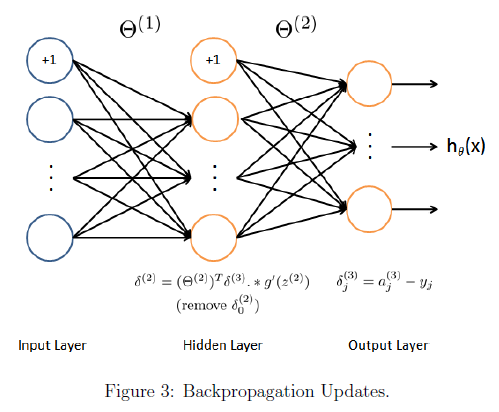

    In detail, here is the backpropagation algorithm (also depicted in Figure 3). You should implement steps 1 to 4 in a loop that processes one example at a time. Concretely, you should implement a `for` loop for `t = 1:m` and place steps 1-4 below inside the `for` loop, with the $t^{th}$ iteration performing the calculation on the $t^{th}$ training example $(x^{(t)}, y^{(t)})$. Step 5 will divide the accumulated gradients by $m$ to obtain the gradients for the neural network cost function.

- Set the input layer's values $(a^{(1)})$ to the $t$-th training example $x^{(t)}$. Perform a feedforward pass (Figure 2), computing the activations $(z^{(2)}, a^{(2)}, z^{(3)}, a^{(3)})$ for layers 2 and 3. Note that you need to add a $+1$ term to ensure that the vectors of activations for layers $a^{(1)}$ and $a^{(2)}$ also include the bias unit. In MATLAB, if `a_1` is a column vector, adding one corresponds to `a_1 = [1; a_1].`

- For each output unit $k$ in layer 3 (the output layer), set $\delta^{(3)}_k = (a_k^{(3)}-y_k)$ where $y_k\in \{0, 1\}$ indicates whether the current training example belongs to class $k$ $(y_k = 1)$, or if it belongs to a different class $(y_k = 0)$.You may find logical arrays helpful for this task (explained in the previous programming exercise).

- For the hidden layer $l = 2$, set $\delta^{(2)} = (\Theta^{(2)})^T \delta^{(3)}.*g'(z^{(2)})$

- Accumulate the gradient from this example using the following formula: $\Delta^{(l)} = \Delta^{(l)} + \delta^{(l+1)} (a^{(l)})^T$. Note that you should skip or remove $\delta_0^{(2)}$. In MATLAB, removing $\delta_0^{(2)}$ corresponds to `delta_2 = delta_2(2:end).`

- Obtain the (unregularized) gradient for the neural network cost function by dividing the accumulated gradients by $\frac{1}{m}:$ $\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij}$

**MATLAB Tip:** You should implement the backpropagation algorithm only after you have successfully completed the feedforward and cost functions. While implementing the backpropagation algorithm, it is often useful to use the size function to print out the sizes of the variables you are working with if you run into dimension mismatch errors (''nonconformant arguments") errors.

    After you have implemented the backpropagation algorithm, the code in the next section will run gradient checking on your implementation. The gradient check will allow you to increase your confidence that your code is computing the gradients correctly.

### 2.4 Gradient checking

In your neural network, you are minimizing the cost function $J(\Theta)$. To perform gradient checking on your parameters, you can imagine 'unrolling' the parameters $\Theta^{(1)},\Theta^{(2)}$ into a long vector $\theta$. By doing so, you can think of the cost function being $J(\theta)$ instead and use the following gradient checking procedure.

    Suppose you have a function $f_i(\theta)$ that purportedly computes $\frac{\partial}{\partial\theta_i}J(\theta)$; you'd like to check if $f_i$ is outputting correct derivative values.


$$\textrm{Let}\;\theta^{i+} =\theta +\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
\epsilon \\
\vdots \\
0
\end{array}\right\rbrack \;\textrm{and}\;\theta^{i-} =\theta -\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
\epsilon \\
\vdots \\
0
\end{array}\right\rbrack$$


    So, $\theta^{(i+)}$ is the same as $\theta$, except its $i$-th element has been incremented by $\epsilon$. Similarly, $\theta^{(i-)}$is the corresponding vector with the $i$-th element decreased by $\epsilon$. You can now numerically verify $f_i(\theta)$'s correctness by checking, for each $i$, that:


$$f_i(\theta) \approx \frac{J(\theta^{(i+)})-J(\theta^{(i-)})}{2\epsilon}$$


The degree to which these two values should approximate each other will depend on the details of $J$. But assuming $\epsilon= 10^{-4}$, you'll usually find that the left- and right-hand sides of the above will agree to at least 4 signicant digits (and often many more). We have implemented the function to compute the numerical gradient for you in `computeNumericalGradient.m`. While you are not required to modify the file, we highly encourage you to take a look at the code to understand how it works.

   The code below will run the provided function `checkNNGradients.m` which will create a small neural network and dataset that will be used for checking your gradients. If your backpropagation implementation is correct, you should see a relative dierence that is less than 1e-9.

checkNNGradients;

**Practical Tip:** When performing gradient checking, it is much more efficient to use a small neural network with a relatively small number of input units and hidden units, thus having a relatively small number of parameters. Each dimension of $\theta$ requires two evaluations of the cost function and this can be expensive. In the function `checkNNGradients`, our code creates a small random model and dataset which is used with `computeNumericalGradient` for gradient checking. Furthermore, after you are condent that your gradient computations are correct, you should turn off gradient checking before running your learning algorithm.

**Practical Tip: **Gradient checking works for any function where you are computing the cost and the gradient. Concretely, you can use the same `computeNumericalGradient.m` function to check if your gradient implementations for the other exercises are correct too (e.g. logistic regression's cost function). Once your cost function passes the gradient check for the (unregularized) neural network cost function, you should submit the neural network gradient function (backpropagation).

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.5 Regularized neural networks

After you have successfully implemeted the backpropagation algorithm, you will add regularization to the gradient. To account for regularization, it turns out that you can add this as an additional term after computing the gradients using backpropagation. Specically, after you have computed $\Delta^{(l)}_{ij}
$ using backpropagation, you should add regularization using


$$\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij} \text{  for  } j = 0,\\
\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij} +\frac{\lambda}{m}\Theta^{(l)}_{ij} \text{  for  } j \geq 1$$


Note that you should *not* be regularizing the first column of $\Theta^{(l)}$ which is used for the bias term. Furthermore, in the parameters $\Theta^{(l)}_{ij}$, $i$ is indexed starting from 1, and $j$ is indexed starting from 0. Thus,


$$\Theta^{\left(l\right)} =\left\lbrack \begin{array}{ccc}
\Theta_{1,0}^{\left(l\right)}  & \Theta_{1,1}^{\left(l\right)}  & \cdots \\
\Theta_{2,0}^{\left(l\right)}  & \Theta_{2,1}^{\left(l\right)}  & \;\\
\vdots  & \; & \ddots 
\end{array}\right\rbrack$$


Somewhat confusingly, indexing in MATLAB starts from 1 (for both $i$ and $j$), thus `Theta1(2, 1)` actually corresponds to $\Theta^{(l)}_{2,0}$ (i.e., the entry in the second row, first column of the matrix $\Theta^{(1)}$ shown above)

    Now, modify your code that computes `grad` in `nnCostFunction` to account for regularization. After you are done, run the code below to run gradient checking on your implementation. If your code is correct, you should expect to see a relative difference that is less than 1e-9.

%  Check gradients by running checkNNGradients
lambda = 3;
checkNNGradients(lambda);
% Also output the costFunction debugging value 
% This value should be about 0.576051
debug_J  = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
fprintf('Cost at (fixed) debugging parameters (w/ lambda = 3): %f', debug_J);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.6 Learning parameters using `fmincg`

After you have successfully implemented the neural network cost function and gradient computation, run the code below to use `fmincg` to learn a good set of parameters. After the training completes, the code will report the training accuracy of your classifier by computing the percentage of examples it got correct. If your implementation is correct, you should see a reported training accuracy of about 95.3% (this may vary by about 1% due to the random initialization). It is possible to get higher training accuracies by training the neural network for more iterations. 

options = optimset('MaxIter', 50);
lambda = 1;

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

% Now, costFunction is a function that takes in only one argument (the
% neural network parameters)
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);
% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 
pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

## 3. Visualizing the hidden layer

One way to understand what your neural network is learning is to visualize what the representations captured by the hidden units. Informally, given a particular hidden unit, one way to visualize what it computes is to find an input `x` that will cause it to activate (that is, to have an activation value $(a^{(l)}_i)$close to 1). For the neural network you trained, notice that the $i^{th}$ row of $\Theta^{(1)}$ is a 401-dimensional vector that represents the parameter for the $i^{th}$ hidden unit. If we discard the bias term, we get a 400 dimensional vector that represents the weights from each input pixel to the hidden unit. 

    Thus, one way to visualize the 'representation' captured by the hidden unit is to reshape this 400 dimensional vector into a 20 x 20 image and display it.* 

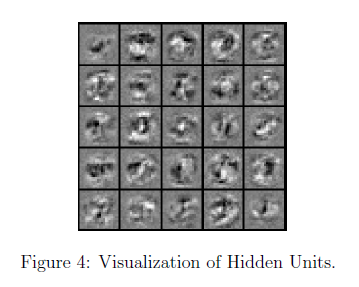

The code below does this by using the `displayData` function and it will show you an image (similar to Figure 4) with 25 units, each corresponding to one hidden unit in the network. In your trained network, you should find that the hidden units corresponds roughly to detectors that look for strokes and other patterns in the input.

% Visualize Weights 
displayData(Theta1(:, 2:end));

**It turns out that this is equivalent to finding the input that gives the highest activation for the hidden unit, given a 'norm' constraint on the input (i.e., *${\left\|x\right\|}_2 \le \;1$*).*

### 3.1 Optional (ungraded) exercise

In this part of the exercise, you will get to try out different learning settings for the neural network to see how the performance of the neural network varies with the regularization parameter and number of training steps (the `MaxIter` option when using `fmincg`). Neural networks are very powerful models that can form highly complex decision boundaries. Without regularization, it is possible for a neural network to 'overfit' a training set so that it obtains close to 100% accuracy on the training set but does not do as well on new examples that it has not seen before. You can set the regularization $\lambda$ to a smaller value and the `MaxIter` parameter to a higher number of iterations to see this for youself. You will also be able to see for yourself the changes in the visualizations of the hidden units when you change the learning parameters $\lambda$ and `MaxIter`.

% Change lambda and MaxIter to see how it affects the result
lambda = 3;
MaxIter = 50;

options = optimset('MaxIter', MaxIter);

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p,input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

% Now, costFunction is a function that takes in only one argument (the neural network parameters)
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);

% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 
pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

% Visualize Weights 
displayData(Theta1(:, 2:end));

*You do not need to submit any solutions for this optional (ungraded) exercise.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

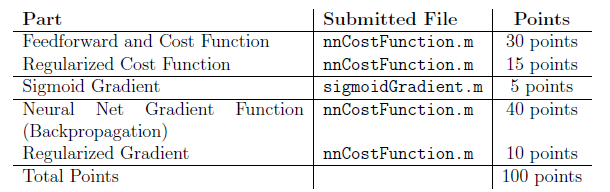

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.